# Image Processing Operator Approximation Using Deep Learning

Example from [mathworks.com](https://se.mathworks.com/help/images/image-processing-operator-approximation-using-deep-learning.html).

## Imports

For the bilateralFilterDataset function.

%import imbilatfilt
%import imwrite

## Directories

%imagesDir = tempdir;
imagesDir = 'D:\Projects\MasterThesis\Salsa_cryptanalysis\matlab\crypto_images\'

imagesDir = 'D:\Projects\MasterThesis\Salsa_cryptanalysis\matlab\crypto_images\'

subDir = 'images\'

subDir = 'RGB_QR\'

% Add/remove '_small' at the end of images/preprocessedDataset, to
% make the dataset small (1000) or large (20000).
trainImagesDir = fullfile(imagesDir, subDir, 'CTs');
preprocessDataDir = fullfile(imagesDir, subDir, 'PTs');

## Download Training and Test Data

%imagesDir = tempdir;
%imagesDir = 'D:\Projects\MasterThesis\Salsa_cryptanalysis\matlab\models'
url_1 = 'http://www-i6.informatik.rwth-aachen.de/imageclef/resources/iaprtc12.tgz';
%downloadIAPRTC12Data(url_1,imagesDir);

% Use this when only wanting around 916 test images.
%trainImagesDir = fullfile(imagesDir,'iaprtc12','images','39');
%trainImagesDir = fullfile(imagesDir,'iaprtc12','images_small');

% Use this when wanting to use the full image data set.
%trainImagesDir = fullfile(imagesDir,'iaprtc12','images');

exts = {'.jpg','.bmp','.png'};
pristineImages = imageDatastore(trainImagesDir,'FileExtensions',exts, 'IncludeSubfolders',true);

% Write out 
numel(pristineImages.Files)

ans = 651

## Prepare Training Data

Process the data. DO NOT RUN!

%preprocessDataDir = [trainImagesDir filesep 'preprocessedDataset'];
%preprocessDataDir = fullfile(imagesDir, 'iaprtc12', 'preprocessedDataset');

%bilateralFilterDataset(pristineImages,preprocessDataDir);

%bilatFilteredImages = imageDatastore(preprocessDataDir,'FileExtensions',exts);

Load training images.

%preprocessDataDir = fullfile(imagesDir, 'iaprtc12', 'preprocessedDataset_small');
bilatFilteredImages = imageDatastore(preprocessDataDir,'FileExtensions',exts);
numel(bilatFilteredImages.Files)

ans = 651

## Define Random Patch Extraction Datastore for Training

bilatFilteredImages = imageDatastore(preprocessDataDir,'FileExtensions',exts);

miniBatchSize = 1;
patchSize = [256 256];
dsTrain = randomPatchExtractionDatastore(pristineImages,bilatFilteredImages,patchSize, ....
    'PatchesPerImage',1);
dsTrain.MiniBatchSize = miniBatchSize;

%class(dsTrain)
inputBatch = read(dsTrain);
disp(inputBatch)

       InputImage          ResponseImage  
    _________________    _________________

    {256×256×3 uint8}    {256×256×3 uint8}



## Set Up Multiscale CAN Layers

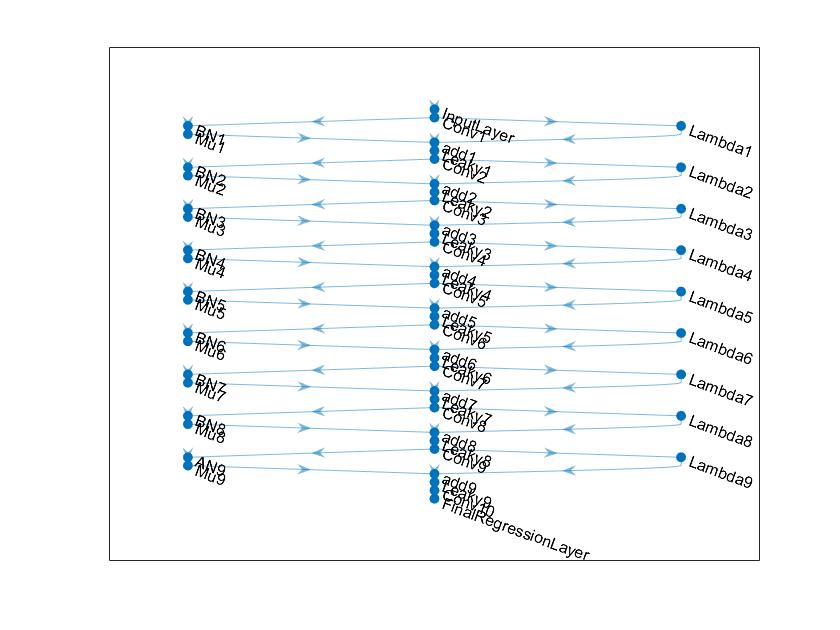

networkDepth = 10;
numberOfFilters = 32;
firstLayer = imageInputLayer([256 256 3],'Name','InputLayer','Normalization','none');


Wgts = zeros(3,3,3,numberOfFilters); 
for ii = 1:3
    % Denne kan lekes med (senere). Bygget for RGB-bilder.
    Wgts(2,2,ii,ii) = 1;
end
convolutionLayer = convolution2dLayer(3,numberOfFilters,'Padding',1, ...
    'Weights',Wgts,'Name','Conv1');


batchNorm = batchNormalizationLayer('Name','BN1');
adaptiveMu = adaptiveNormalizationMu(numberOfFilters,'Mu1');
addLayer = additionLayer(2,'Name','add1');
leakyrelLayer = leakyReluLayer(0.2,'Name','Leaky1');


middleLayers = [convolutionLayer batchNorm adaptiveMu addLayer leakyrelLayer];

Wgts = zeros(3,3,numberOfFilters,numberOfFilters);
for ii = 1:numberOfFilters
    Wgts(2,2,ii,ii) = 1;
end
    
for layerNumber = 2:networkDepth-2
    dilationFactor = 2^(layerNumber-1);
    padding = dilationFactor;
    conv2dLayer = convolution2dLayer(3,numberOfFilters, ...
        'Padding',padding,'DilationFactor',dilationFactor, ...
        'Weights',Wgts,'Name',['Conv' num2str(layerNumber)]);
    batchNorm = batchNormalizationLayer('Name',['BN' num2str(layerNumber)]);
    adaptiveMu = adaptiveNormalizationMu(numberOfFilters,['Mu' num2str(layerNumber)]);
    addLayer = additionLayer(2,'Name',['add' num2str(layerNumber)]);
    leakyrelLayer = leakyReluLayer(0.2, 'Name', ['Leaky' num2str(layerNumber)]);
    middleLayers = [middleLayers conv2dLayer batchNorm adaptiveMu addLayer leakyrelLayer];    
end


conv2dLayer = convolution2dLayer(3,numberOfFilters, ...
    'Padding',1,'Weights',Wgts,'Name','Conv9');

batchNorm = batchNormalizationLayer('Name','AN9');
adaptiveMu = adaptiveNormalizationMu(numberOfFilters,'Mu9');
addLayer = additionLayer(2,'Name','add9');
leakyrelLayer = leakyReluLayer(0.2,'Name','Leaky9');
middleLayers = [middleLayers conv2dLayer batchNorm adaptiveMu addLayer leakyrelLayer];


Wgts = sqrt(2/(9*numberOfFilters))*randn(1,1,numberOfFilters,3);
conv2dLayer = convolution2dLayer(1,3,'NumChannels',numberOfFilters, ...
    'Weights',Wgts,'Name','Conv10');


finalLayers = [conv2dLayer 
    regressionLayer('Name','FinalRegressionLayer')
];


layers = [firstLayer middleLayers finalLayers'];
lgraph = layerGraph(layers);


skipConv1 = adaptiveNormalizationLambda(numberOfFilters,'Lambda1');
skipConv2 = adaptiveNormalizationLambda(numberOfFilters,'Lambda2');
skipConv3 = adaptiveNormalizationLambda(numberOfFilters,'Lambda3');
skipConv4 = adaptiveNormalizationLambda(numberOfFilters,'Lambda4');
skipConv5 = adaptiveNormalizationLambda(numberOfFilters,'Lambda5');
skipConv6 = adaptiveNormalizationLambda(numberOfFilters,'Lambda6');
skipConv7 = adaptiveNormalizationLambda(numberOfFilters,'Lambda7');
skipConv8 = adaptiveNormalizationLambda(numberOfFilters,'Lambda8');
skipConv9 = adaptiveNormalizationLambda(numberOfFilters,'Lambda9');

lgraph = addLayers(lgraph,skipConv1);
lgraph = connectLayers(lgraph,'Conv1','Lambda1');
lgraph = connectLayers(lgraph,'Lambda1','add1/in2');

lgraph = addLayers(lgraph,skipConv2);
lgraph = connectLayers(lgraph,'Conv2','Lambda2');
lgraph = connectLayers(lgraph,'Lambda2','add2/in2');

lgraph = addLayers(lgraph,skipConv3);
lgraph = connectLayers(lgraph,'Conv3','Lambda3');
lgraph = connectLayers(lgraph,'Lambda3','add3/in2');

lgraph = addLayers(lgraph,skipConv4);
lgraph = connectLayers(lgraph,'Conv4','Lambda4');
lgraph = connectLayers(lgraph,'Lambda4','add4/in2');

lgraph = addLayers(lgraph,skipConv5);
lgraph = connectLayers(lgraph,'Conv5','Lambda5');
lgraph = connectLayers(lgraph,'Lambda5','add5/in2');

lgraph = addLayers(lgraph,skipConv6);
lgraph = connectLayers(lgraph,'Conv6','Lambda6');
lgraph = connectLayers(lgraph,'Lambda6','add6/in2');

lgraph = addLayers(lgraph,skipConv7);
lgraph = connectLayers(lgraph,'Conv7','Lambda7');
lgraph = connectLayers(lgraph,'Lambda7','add7/in2');

lgraph = addLayers(lgraph,skipConv8);
lgraph = connectLayers(lgraph,'Conv8','Lambda8');
lgraph = connectLayers(lgraph,'Lambda8','add8/in2');

lgraph = addLayers(lgraph,skipConv9);
lgraph = connectLayers(lgraph,'Conv9','Lambda9');
lgraph = connectLayers(lgraph,'Lambda9','add9/in2');


plot(lgraph)

## Specify Training Options

maxEpochs = 300;
initLearningRate = 0.00001; % Lek!
miniBatchSize = 1; % Iterasjoner = len(bilder) / miniBatchSize

options = trainingOptions('adam', ...
    'InitialLearnRate',initLearningRate, ...
    'MaxEpochs',maxEpochs, ...
    'MiniBatchSize',miniBatchSize, ...
    'Plots','training-progress', ...
    'Verbose',true);

## Train the Network

doTraining = true;
if doTraining
    modelDateTime = datestr(now,'dd-mmm-yyyy-HH-MM-SS');
    net = trainNetwork(dsTrain,lgraph,options);
    save(['models/trainedOperatorLearning-' modelDateTime '-Epoch-' num2str(maxEpochs) '.mat'],'net');
else
    load('models/trainedOperatorLearning-Epoch-181.mat');
end

Training on single GPU.


|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|


|       1 |           1 |       00:00:06 |     87477.90 |      3.8e+09 |      1.0000e-05 |


|       1 |          50 |       00:00:23 |     80773.73 |      3.3e+09 |      1.0000e-05 |


|       1 |         100 |       00:00:39 |     66069.55 |      2.2e+09 |      1.0000e-05 |


|       1 |         150 |       00:00:57 |     57783.19 |      1.7e+09 |      1.0000e-05 |


|       1 |         200 |       00:01:13 |     57570.54 |      1.7e+09 |      1.0000e-05 |


|       1 |         250 |       00:01:27 |     57537.54 |      1.7e+09 |      1.0000e-05 |


|       1 |         300 |       00:01:41 |     57500.85 |      1.7e+09 |      1.0000e-05 |


|       1 |         350 |       00:01:56 |     57483.54 |      1.7e+09 |      1.0000e-05 |


|       1 |         400 |       00:02:10 |     57391.93 |      1.6e+09 |      1.0000e-05 |


|       1 |         450 |       00:02:24 |     57381.60 |      1.6e+09 |      1.0000e-05 |


|       1 |         500 |       00:02:38 |     57316.58 |      1.6e+09 |      1.0000e-05 |


|       1 |         550 |       00:02:52 |     57231.07 |      1.6e+09 |      1.0000e-05 |


|       1 |         600 |       00:03:06 |     57234.74 |      1.6e+09 |      1.0000e-05 |


|       1 |         650 |       00:03:19 |     57148.59 |      1.6e+09 |      1.0000e-05 |


|       2 |         700 |       00:03:33 |     57076.02 |      1.6e+09 |      1.0000e-05 |


|       2 |         750 |       00:03:47 |     57090.43 |      1.6e+09 |      1.0000e-05 |


|       2 |         800 |       00:04:05 |     57032.63 |      1.6e+09 |      1.0000e-05 |


|       2 |         850 |       00:04:26 |     56983.09 |      1.6e+09 |      1.0000e-05 |


|       2 |         900 |       00:04:42 |     56993.41 |      1.6e+09 |      1.0000e-05 |


|       2 |         950 |       00:04:56 |     56986.48 |      1.6e+09 |      1.0000e-05 |


|       2 |        1000 |       00:05:10 |     56940.21 |      1.6e+09 |      1.0000e-05 |


|       2 |        1050 |       00:05:24 |     56935.79 |      1.6e+09 |      1.0000e-05 |


|       2 |        1100 |       00:05:38 |     56887.92 |      1.6e+09 |      1.0000e-05 |


|       2 |        1150 |       00:05:52 |     56864.51 |      1.6e+09 |      1.0000e-05 |


|       2 |        1200 |       00:06:05 |     56864.76 |      1.6e+09 |      1.0000e-05 |


|       2 |        1250 |       00:06:18 |     56876.89 |      1.6e+09 |      1.0000e-05 |


|       2 |        1300 |       00:06:34 |     56852.76 |      1.6e+09 |      1.0000e-05 |


|       3 |        1350 |       00:06:49 |     56841.04 |      1.6e+09 |      1.0000e-05 |


|       3 |        1400 |       00:07:05 |     56810.96 |      1.6e+09 |      1.0000e-05 |


|       3 |        1450 |       00:07:23 |     56817.29 |      1.6e+09 |      1.0000e-05 |


|       3 |        1500 |       00:07:37 |     56799.16 |      1.6e+09 |      1.0000e-05 |


|       3 |        1550 |       00:07:48 |     56769.78 |      1.6e+09 |      1.0000e-05 |


|       3 |        1600 |       00:07:59 |     56778.51 |      1.6e+09 |      1.0000e-05 |


|       3 |        1650 |       00:08:11 |     56771.94 |      1.6e+09 |      1.0000e-05 |


|       3 |        1700 |       00:08:26 |     56744.41 |      1.6e+09 |      1.0000e-05 |


|       3 |        1750 |       00:08:43 |     56765.10 |      1.6e+09 |      1.0000e-05 |


|       3 |        1800 |       00:08:59 |     56746.66 |      1.6e+09 |      1.0000e-05 |


|       3 |        1850 |       00:09:13 |     56733.42 |      1.6e+09 |      1.0000e-05 |


|       3 |        1900 |       00:09:26 |     56724.15 |      1.6e+09 |      1.0000e-05 |


|       3 |        1950 |       00:09:39 |     56732.30 |      1.6e+09 |      1.0000e-05 |


|       4 |        2000 |       00:09:51 |     56720.30 |      1.6e+09 |      1.0000e-05 |


|       4 |        2050 |       00:10:04 |     56723.57 |      1.6e+09 |      1.0000e-05 |


|       4 |        2100 |       00:10:16 |     56700.02 |      1.6e+09 |      1.0000e-05 |


|       4 |        2150 |       00:10:29 |     56674.91 |      1.6e+09 |      1.0000e-05 |


|       4 |        2200 |       00:10:41 |     56686.23 |      1.6e+09 |      1.0000e-05 |


|       4 |        2250 |       00:10:54 |     56660.43 |      1.6e+09 |      1.0000e-05 |


|       4 |        2300 |       00:11:06 |     56673.41 |      1.6e+09 |      1.0000e-05 |


|       4 |        2350 |       00:11:19 |     56676.13 |      1.6e+09 |      1.0000e-05 |


|       4 |        2400 |       00:11:31 |     56664.90 |      1.6e+09 |      1.0000e-05 |


|       4 |        2450 |       00:11:44 |     56660.91 |      1.6e+09 |      1.0000e-05 |


|       4 |        2500 |       00:11:56 |     56671.93 |      1.6e+09 |      1.0000e-05 |


|       4 |        2550 |       00:12:09 |     56652.57 |      1.6e+09 |      1.0000e-05 |


|       4 |        2600 |       00:12:22 |     56646.51 |      1.6e+09 |      1.0000e-05 |


|       5 |        2650 |       00:12:35 |     56651.37 |      1.6e+09 |      1.0000e-05 |


|       5 |        2700 |       00:12:48 |     56649.79 |      1.6e+09 |      1.0000e-05 |


|       5 |        2750 |       00:13:02 |     56641.85 |      1.6e+09 |      1.0000e-05 |


|       5 |        2800 |       00:13:16 |     56636.31 |      1.6e+09 |      1.0000e-05 |


|       5 |        2850 |       00:13:30 |     56641.27 |      1.6e+09 |      1.0000e-05 |


|       5 |        2900 |       00:13:43 |     56617.12 |      1.6e+09 |      1.0000e-05 |


|       5 |        2950 |       00:13:57 |     56627.29 |      1.6e+09 |      1.0000e-05 |


|       5 |        3000 |       00:14:11 |     56627.44 |      1.6e+09 |      1.0000e-05 |


|       5 |        3050 |       00:14:23 |     56628.36 |      1.6e+09 |      1.0000e-05 |


|       5 |        3100 |       00:14:37 |     56616.20 |      1.6e+09 |      1.0000e-05 |


|       5 |        3150 |       00:14:47 |     56610.43 |      1.6e+09 |      1.0000e-05 |


|       5 |        3200 |       00:14:57 |     56619.45 |      1.6e+09 |      1.0000e-05 |


|       5 |        3250 |       00:15:08 |     56611.93 |      1.6e+09 |      1.0000e-05 |


|       6 |        3300 |       00:15:18 |     56609.68 |      1.6e+09 |      1.0000e-05 |


|       6 |        3350 |       00:15:29 |     56607.19 |      1.6e+09 |      1.0000e-05 |


|       6 |        3400 |       00:15:39 |     56597.27 |      1.6e+09 |      1.0000e-05 |


|       6 |        3450 |       00:15:50 |     56602.68 |      1.6e+09 |      1.0000e-05 |


|       6 |        3500 |       00:16:01 |     56590.69 |      1.6e+09 |      1.0000e-05 |


|       6 |        3550 |       00:16:11 |     56605.20 |      1.6e+09 |      1.0000e-05 |


|       6 |        3600 |       00:16:21 |     56586.99 |      1.6e+09 |      1.0000e-05 |


|       6 |        3650 |       00:16:32 |     56592.28 |      1.6e+09 |      1.0000e-05 |


|       6 |        3700 |       00:16:42 |     56584.14 |      1.6e+09 |      1.0000e-05 |


|       6 |        3750 |       00:16:52 |     56582.10 |      1.6e+09 |      1.0000e-05 |


|       6 |        3800 |       00:17:03 |     56581.54 |      1.6e+09 |      1.0000e-05 |


|       6 |        3850 |       00:17:13 |     56578.87 |      1.6e+09 |      1.0000e-05 |


|       6 |        3900 |       00:17:23 |     56567.18 |      1.6e+09 |      1.0000e-05 |


|       7 |        3950 |       00:17:34 |     56578.14 |      1.6e+09 |      1.0000e-05 |


|       7 |        4000 |       00:17:44 |     56579.55 |      1.6e+09 |      1.0000e-05 |


|       7 |        4050 |       00:17:55 |     56585.74 |      1.6e+09 |      1.0000e-05 |


|       7 |        4100 |       00:18:05 |     56577.69 |      1.6e+09 |      1.0000e-05 |


|       7 |        4150 |       00:18:16 |     56580.64 |      1.6e+09 |      1.0000e-05 |


|       7 |        4200 |       00:18:26 |     56580.01 |      1.6e+09 |      1.0000e-05 |


|       7 |        4250 |       00:18:37 |     56565.54 |      1.6e+09 |      1.0000e-05 |


|       7 |        4300 |       00:18:47 |     56573.02 |      1.6e+09 |      1.0000e-05 |


|       7 |        4350 |       00:18:58 |     56569.70 |      1.6e+09 |      1.0000e-05 |


|       7 |        4400 |       00:19:08 |     56567.30 |      1.6e+09 |      1.0000e-05 |


|       7 |        4450 |       00:19:19 |     56556.84 |      1.6e+09 |      1.0000e-05 |


|       7 |        4500 |       00:19:29 |     56563.21 |      1.6e+09 |      1.0000e-05 |


|       7 |        4550 |       00:19:40 |     56553.18 |      1.6e+09 |      1.0000e-05 |


|       8 |        4600 |       00:19:51 |     56563.66 |      1.6e+09 |      1.0000e-05 |


|       8 |        4650 |       00:20:01 |     56565.13 |      1.6e+09 |      1.0000e-05 |


|       8 |        4700 |       00:20:12 |     56561.98 |      1.6e+09 |      1.0000e-05 |


|       8 |        4750 |       00:20:22 |     56564.92 |      1.6e+09 |      1.0000e-05 |


|       8 |        4800 |       00:20:33 |     56562.50 |      1.6e+09 |      1.0000e-05 |


|       8 |        4850 |       00:20:44 |     56560.34 |      1.6e+09 |      1.0000e-05 |


|       8 |        4900 |       00:20:54 |     56559.37 |      1.6e+09 |      1.0000e-05 |


|       8 |        4950 |       00:21:05 |     56556.61 |      1.6e+09 |      1.0000e-05 |


|       8 |        5000 |       00:21:15 |     56553.23 |      1.6e+09 |      1.0000e-05 |


|       8 |        5050 |       00:21:26 |     56551.55 |      1.6e+09 |      1.0000e-05 |


|       8 |        5100 |       00:21:36 |     56558.68 |      1.6e+09 |      1.0000e-05 |


|       8 |        5150 |       00:21:47 |     56558.46 |      1.6e+09 |      1.0000e-05 |


|       8 |        5200 |       00:21:57 |     56557.87 |      1.6e+09 |      1.0000e-05 |


|       9 |        5250 |       00:22:08 |     56556.16 |      1.6e+09 |      1.0000e-05 |


|       9 |        5300 |       00:22:19 |     56555.46 |      1.6e+09 |      1.0000e-05 |


|       9 |        5350 |       00:22:29 |     56558.59 |      1.6e+09 |      1.0000e-05 |


|       9 |        5400 |       00:22:40 |     56556.93 |      1.6e+09 |      1.0000e-05 |


|       9 |        5450 |       00:22:51 |     56556.95 |      1.6e+09 |      1.0000e-05 |


|       9 |        5500 |       00:23:01 |     56553.55 |      1.6e+09 |      1.0000e-05 |


|       9 |        5550 |       00:23:12 |     56553.97 |      1.6e+09 |      1.0000e-05 |


|       9 |        5600 |       00:23:23 |     56555.11 |      1.6e+09 |      1.0000e-05 |


|       9 |        5650 |       00:23:33 |     56555.63 |      1.6e+09 |      1.0000e-05 |


|       9 |        5700 |       00:23:44 |     56546.94 |      1.6e+09 |      1.0000e-05 |


|       9 |        5750 |       00:23:55 |     56551.70 |      1.6e+09 |      1.0000e-05 |


|       9 |        5800 |       00:24:05 |     56548.20 |      1.6e+09 |      1.0000e-05 |


|       9 |        5850 |       00:24:16 |     56551.89 |      1.6e+09 |      1.0000e-05 |


|      10 |        5900 |       00:24:26 |     56557.44 |      1.6e+09 |      1.0000e-05 |


|      10 |        5950 |       00:24:37 |     56555.00 |      1.6e+09 |      1.0000e-05 |


|      10 |        6000 |       00:24:48 |     56554.43 |      1.6e+09 |      1.0000e-05 |


|      10 |        6050 |       00:24:59 |     56551.90 |      1.6e+09 |      1.0000e-05 |


|      10 |        6100 |       00:25:09 |     56550.18 |      1.6e+09 |      1.0000e-05 |


|      10 |        6150 |       00:25:20 |     56552.93 |      1.6e+09 |      1.0000e-05 |


|      10 |        6200 |       00:25:31 |     56548.76 |      1.6e+09 |      1.0000e-05 |


|      10 |        6250 |       00:25:41 |     56547.70 |      1.6e+09 |      1.0000e-05 |


|      10 |        6300 |       00:25:52 |     56549.61 |      1.6e+09 |      1.0000e-05 |


|      10 |        6350 |       00:26:03 |     56548.51 |      1.6e+09 |      1.0000e-05 |


|      10 |        6400 |       00:26:14 |     56552.61 |      1.6e+09 |      1.0000e-05 |


|      10 |        6450 |       00:26:25 |     56550.09 |      1.6e+09 |      1.0000e-05 |


|      10 |        6500 |       00:26:36 |     56548.18 |      1.6e+09 |      1.0000e-05 |


|      11 |        6550 |       00:26:46 |     56548.99 |      1.6e+09 |      1.0000e-05 |


|      11 |        6600 |       00:26:57 |     56545.48 |      1.6e+09 |      1.0000e-05 |


|      11 |        6650 |       00:27:08 |     56542.89 |      1.6e+09 |      1.0000e-05 |


|      11 |        6700 |       00:27:18 |     56546.50 |      1.6e+09 |      1.0000e-05 |


|      11 |        6750 |       00:27:29 |     56549.33 |      1.6e+09 |      1.0000e-05 |


|      11 |        6800 |       00:27:39 |     56548.91 |      1.6e+09 |      1.0000e-05 |


|      11 |        6850 |       00:27:50 |     56547.80 |      1.6e+09 |      1.0000e-05 |


|      11 |        6900 |       00:28:00 |     56548.04 |      1.6e+09 |      1.0000e-05 |


|      11 |        6950 |       00:28:11 |     56551.17 |      1.6e+09 |      1.0000e-05 |


|      11 |        7000 |       00:28:21 |     56547.34 |      1.6e+09 |      1.0000e-05 |


|      11 |        7050 |       00:28:32 |     56545.32 |      1.6e+09 |      1.0000e-05 |


|      11 |        7100 |       00:28:42 |     56547.78 |      1.6e+09 |      1.0000e-05 |


|      11 |        7150 |       00:28:53 |     56548.39 |      1.6e+09 |      1.0000e-05 |


|      12 |        7200 |       00:29:04 |     56545.89 |      1.6e+09 |      1.0000e-05 |


|      12 |        7250 |       00:29:14 |     56546.22 |      1.6e+09 |      1.0000e-05 |


|      12 |        7300 |       00:29:24 |     56543.81 |      1.6e+09 |      1.0000e-05 |


|      12 |        7350 |       00:29:35 |     56543.11 |      1.6e+09 |      1.0000e-05 |


|      12 |        7400 |       00:29:46 |     56542.85 |      1.6e+09 |      1.0000e-05 |


|      12 |        7450 |       00:29:56 |     56544.62 |      1.6e+09 |      1.0000e-05 |


|      12 |        7500 |       00:30:07 |     56544.24 |      1.6e+09 |      1.0000e-05 |


|      12 |        7550 |       00:30:17 |     56548.34 |      1.6e+09 |      1.0000e-05 |


|      12 |        7600 |       00:30:28 |     56543.10 |      1.6e+09 |      1.0000e-05 |


|      12 |        7650 |       00:30:38 |     56542.89 |      1.6e+09 |      1.0000e-05 |


|      12 |        7700 |       00:30:48 |     56545.24 |      1.6e+09 |      1.0000e-05 |


|      12 |        7750 |       00:30:59 |     56544.04 |      1.6e+09 |      1.0000e-05 |


|      12 |        7800 |       00:31:09 |     56547.38 |      1.6e+09 |      1.0000e-05 |


|      13 |        7850 |       00:31:20 |     56540.75 |      1.6e+09 |      1.0000e-05 |


|      13 |        7900 |       00:31:30 |     56546.49 |      1.6e+09 |      1.0000e-05 |


|      13 |        7950 |       00:31:41 |     56546.21 |      1.6e+09 |      1.0000e-05 |


|      13 |        8000 |       00:31:51 |     56540.27 |      1.6e+09 |      1.0000e-05 |


|      13 |        8050 |       00:32:02 |     56543.47 |      1.6e+09 |      1.0000e-05 |


|      13 |        8100 |       00:32:12 |     56547.82 |      1.6e+09 |      1.0000e-05 |


|      13 |        8150 |       00:32:23 |     56541.73 |      1.6e+09 |      1.0000e-05 |


|      13 |        8200 |       00:32:33 |     56547.70 |      1.6e+09 |      1.0000e-05 |


|      13 |        8250 |       00:32:44 |     56548.10 |      1.6e+09 |      1.0000e-05 |


|      13 |        8300 |       00:32:54 |     56542.50 |      1.6e+09 |      1.0000e-05 |


|      13 |        8350 |       00:33:04 |     56543.59 |      1.6e+09 |      1.0000e-05 |


|      13 |        8400 |       00:33:15 |     56539.74 |      1.6e+09 |      1.0000e-05 |


|      13 |        8450 |       00:33:25 |     56538.90 |      1.6e+09 |      1.0000e-05 |


|      14 |        8500 |       00:33:36 |     56538.09 |      1.6e+09 |      1.0000e-05 |


|      14 |        8550 |       00:33:47 |     56540.98 |      1.6e+09 |      1.0000e-05 |


|      14 |        8600 |       00:33:58 |     56541.84 |      1.6e+09 |      1.0000e-05 |


|      14 |        8650 |       00:34:08 |     56543.95 |      1.6e+09 |      1.0000e-05 |


|      14 |        8700 |       00:34:19 |     56544.59 |      1.6e+09 |      1.0000e-05 |


|      14 |        8750 |       00:34:29 |     56540.75 |      1.6e+09 |      1.0000e-05 |


|      14 |        8800 |       00:34:40 |     56541.24 |      1.6e+09 |      1.0000e-05 |


|      14 |        8850 |       00:34:50 |     56543.16 |      1.6e+09 |      1.0000e-05 |


|      14 |        8900 |       00:35:01 |     56544.45 |      1.6e+09 |      1.0000e-05 |


|      14 |        8950 |       00:35:11 |     56538.87 |      1.6e+09 |      1.0000e-05 |


|      14 |        9000 |       00:35:21 |     56545.62 |      1.6e+09 |      1.0000e-05 |


|      14 |        9050 |       00:35:32 |     56542.64 |      1.6e+09 |      1.0000e-05 |


|      14 |        9100 |       00:35:42 |     56540.76 |      1.6e+09 |      1.0000e-05 |


|      15 |        9150 |       00:35:53 |     56540.89 |      1.6e+09 |      1.0000e-05 |


|      15 |        9200 |       00:36:03 |     56543.65 |      1.6e+09 |      1.0000e-05 |


|      15 |        9250 |       00:36:13 |     56540.58 |      1.6e+09 |      1.0000e-05 |


|      15 |        9300 |       00:36:24 |     56540.62 |      1.6e+09 |      1.0000e-05 |


|      15 |        9350 |       00:36:34 |     56541.77 |      1.6e+09 |      1.0000e-05 |


|      15 |        9400 |       00:36:44 |     56539.83 |      1.6e+09 |      1.0000e-05 |


|      15 |        9450 |       00:36:55 |     56543.08 |      1.6e+09 |      1.0000e-05 |


|      15 |        9500 |       00:37:05 |     56541.11 |      1.6e+09 |      1.0000e-05 |


|      15 |        9550 |       00:37:15 |     56537.89 |      1.6e+09 |      1.0000e-05 |


|      15 |        9600 |       00:37:26 |     56537.79 |      1.6e+09 |      1.0000e-05 |


|      15 |        9650 |       00:37:36 |     56540.99 |      1.6e+09 |      1.0000e-05 |


|      15 |        9700 |       00:37:46 |     56542.85 |      1.6e+09 |      1.0000e-05 |


|      15 |        9750 |       00:37:57 |     56542.55 |      1.6e+09 |      1.0000e-05 |


|      16 |        9800 |       00:38:07 |     56541.56 |      1.6e+09 |      1.0000e-05 |


|      16 |        9850 |       00:38:17 |     56541.63 |      1.6e+09 |      1.0000e-05 |


|      16 |        9900 |       00:38:28 |     56538.05 |      1.6e+09 |      1.0000e-05 |


|      16 |        9950 |       00:38:40 |     56543.65 |      1.6e+09 |      1.0000e-05 |


|      16 |       10000 |       00:38:51 |     56545.16 |      1.6e+09 |      1.0000e-05 |


|      16 |       10050 |       00:39:03 |     56540.15 |      1.6e+09 |      1.0000e-05 |


|      16 |       10100 |       00:39:14 |     56541.12 |      1.6e+09 |      1.0000e-05 |


|      16 |       10150 |       00:39:26 |     56539.12 |      1.6e+09 |      1.0000e-05 |


|      16 |       10200 |       00:39:37 |     56541.26 |      1.6e+09 |      1.0000e-05 |


|      16 |       10250 |       00:39:49 |     56540.12 |      1.6e+09 |      1.0000e-05 |


|      16 |       10300 |       00:40:00 |     56542.64 |      1.6e+09 |      1.0000e-05 |


|      16 |       10350 |       00:40:11 |     56538.65 |      1.6e+09 |      1.0000e-05 |


|      16 |       10400 |       00:40:22 |     56540.36 |      1.6e+09 |      1.0000e-05 |


|      17 |       10450 |       00:40:33 |     56544.80 |      1.6e+09 |      1.0000e-05 |


|      17 |       10500 |       00:40:46 |     56537.00 |      1.6e+09 |      1.0000e-05 |


|      17 |       10550 |       00:40:57 |     56538.79 |      1.6e+09 |      1.0000e-05 |


|      17 |       10600 |       00:41:09 |     56541.54 |      1.6e+09 |      1.0000e-05 |


|      17 |       10650 |       00:41:21 |     56541.46 |      1.6e+09 |      1.0000e-05 |


|      17 |       10700 |       00:41:32 |     56538.36 |      1.6e+09 |      1.0000e-05 |


|      17 |       10750 |       00:41:43 |     56540.12 |      1.6e+09 |      1.0000e-05 |


|      17 |       10800 |       00:41:55 |     56537.82 |      1.6e+09 |      1.0000e-05 |


|      17 |       10850 |       00:42:06 |     56538.23 |      1.6e+09 |      1.0000e-05 |


|      17 |       10900 |       00:42:18 |     56537.28 |      1.6e+09 |      1.0000e-05 |


|      17 |       10950 |       00:42:30 |     56537.84 |      1.6e+09 |      1.0000e-05 |


|      17 |       11000 |       00:42:41 |     56545.94 |      1.6e+09 |      1.0000e-05 |


|      17 |       11050 |       00:42:53 |     56535.71 |      1.6e+09 |      1.0000e-05 |


|      18 |       11100 |       00:43:05 |     56541.73 |      1.6e+09 |      1.0000e-05 |


|      18 |       11150 |       00:43:17 |     56538.38 |      1.6e+09 |      1.0000e-05 |


|      18 |       11200 |       00:43:28 |     56536.71 |      1.6e+09 |      1.0000e-05 |


|      18 |       11250 |       00:43:39 |     56540.73 |      1.6e+09 |      1.0000e-05 |


|      18 |       11300 |       00:43:50 |     56540.08 |      1.6e+09 |      1.0000e-05 |


|      18 |       11350 |       00:44:02 |     56542.80 |      1.6e+09 |      1.0000e-05 |


|      18 |       11400 |       00:44:14 |     56537.68 |      1.6e+09 |      1.0000e-05 |


|      18 |       11450 |       00:44:25 |     56540.46 |      1.6e+09 |      1.0000e-05 |


|      18 |       11500 |       00:44:37 |     56536.05 |      1.6e+09 |      1.0000e-05 |


|      18 |       11550 |       00:44:48 |     56541.54 |      1.6e+09 |      1.0000e-05 |


|      18 |       11600 |       00:45:00 |     56537.56 |      1.6e+09 |      1.0000e-05 |


|      18 |       11650 |       00:45:11 |     56540.52 |      1.6e+09 |      1.0000e-05 |


|      18 |       11700 |       00:45:22 |     56538.23 |      1.6e+09 |      1.0000e-05 |


|      19 |       11750 |       00:45:34 |     56539.19 |      1.6e+09 |      1.0000e-05 |


|      19 |       11800 |       00:45:45 |     56540.36 |      1.6e+09 |      1.0000e-05 |


|      19 |       11850 |       00:45:56 |     56544.12 |      1.6e+09 |      1.0000e-05 |


|      19 |       11900 |       00:46:08 |     56536.54 |      1.6e+09 |      1.0000e-05 |


|      19 |       11950 |       00:46:19 |     56540.55 |      1.6e+09 |      1.0000e-05 |


|      19 |       12000 |       00:46:31 |     56538.04 |      1.6e+09 |      1.0000e-05 |


|      19 |       12050 |       00:46:42 |     56539.79 |      1.6e+09 |      1.0000e-05 |


|      19 |       12100 |       00:46:53 |     56536.79 |      1.6e+09 |      1.0000e-05 |


|      19 |       12150 |       00:47:05 |     56535.16 |      1.6e+09 |      1.0000e-05 |


|      19 |       12200 |       00:47:16 |     56538.23 |      1.6e+09 |      1.0000e-05 |


|      19 |       12250 |       00:47:27 |     56538.58 |      1.6e+09 |      1.0000e-05 |


|      19 |       12300 |       00:47:38 |     56539.02 |      1.6e+09 |      1.0000e-05 |


|      19 |       12350 |       00:47:49 |     56538.76 |      1.6e+09 |      1.0000e-05 |


|      20 |       12400 |       00:48:01 |     56539.04 |      1.6e+09 |      1.0000e-05 |


|      20 |       12450 |       00:48:12 |     56537.60 |      1.6e+09 |      1.0000e-05 |


|      20 |       12500 |       00:48:23 |     56545.18 |      1.6e+09 |      1.0000e-05 |


|      20 |       12550 |       00:48:34 |     56538.99 |      1.6e+09 |      1.0000e-05 |


|      20 |       12600 |       00:48:45 |     56538.71 |      1.6e+09 |      1.0000e-05 |


|      20 |       12650 |       00:48:57 |     56540.29 |      1.6e+09 |      1.0000e-05 |


|      20 |       12700 |       00:49:08 |     56537.58 |      1.6e+09 |      1.0000e-05 |


|      20 |       12750 |       00:49:20 |     56542.01 |      1.6e+09 |      1.0000e-05 |


|      20 |       12800 |       00:49:31 |     56536.95 |      1.6e+09 |      1.0000e-05 |


|      20 |       12850 |       00:49:43 |     56535.42 |      1.6e+09 |      1.0000e-05 |


|      20 |       12900 |       00:49:55 |     56540.18 |      1.6e+09 |      1.0000e-05 |


|      20 |       12950 |       00:50:06 |     56537.79 |      1.6e+09 |      1.0000e-05 |


|      20 |       13000 |       00:50:18 |     56540.20 |      1.6e+09 |      1.0000e-05 |


|      21 |       13050 |       00:50:29 |     56539.09 |      1.6e+09 |      1.0000e-05 |


|      21 |       13100 |       00:50:40 |     56539.04 |      1.6e+09 |      1.0000e-05 |


|      21 |       13150 |       00:50:51 |     56537.41 |      1.6e+09 |      1.0000e-05 |


|      21 |       13200 |       00:51:03 |     56538.78 |      1.6e+09 |      1.0000e-05 |


|      21 |       13250 |       00:51:14 |     56536.02 |      1.6e+09 |      1.0000e-05 |


|      21 |       13300 |       00:51:25 |     56537.50 |      1.6e+09 |      1.0000e-05 |


|      21 |       13350 |       00:51:37 |     56537.13 |      1.6e+09 |      1.0000e-05 |


|      21 |       13400 |       00:51:48 |     56539.43 |      1.6e+09 |      1.0000e-05 |


|      21 |       13450 |       00:52:00 |     56537.37 |      1.6e+09 |      1.0000e-05 |


|      21 |       13500 |       00:52:11 |     56537.30 |      1.6e+09 |      1.0000e-05 |


|      21 |       13550 |       00:52:22 |     56538.07 |      1.6e+09 |      1.0000e-05 |


|      21 |       13600 |       00:52:34 |     56540.49 |      1.6e+09 |      1.0000e-05 |


|      21 |       13650 |       00:52:45 |     56537.86 |      1.6e+09 |      1.0000e-05 |


|      22 |       13700 |       00:52:57 |     56538.69 |      1.6e+09 |      1.0000e-05 |


|      22 |       13750 |       00:53:08 |     56538.29 |      1.6e+09 |      1.0000e-05 |


|      22 |       13800 |       00:53:20 |     56539.93 |      1.6e+09 |      1.0000e-05 |


|      22 |       13850 |       00:53:31 |     56538.38 |      1.6e+09 |      1.0000e-05 |


|      22 |       13900 |       00:53:43 |     56538.98 |      1.6e+09 |      1.0000e-05 |


|      22 |       13950 |       00:53:54 |     56538.49 |      1.6e+09 |      1.0000e-05 |


|      22 |       14000 |       00:54:05 |     56538.37 |      1.6e+09 |      1.0000e-05 |


|      22 |       14050 |       00:54:17 |     56535.81 |      1.6e+09 |      1.0000e-05 |


|      22 |       14100 |       00:54:29 |     56534.76 |      1.6e+09 |      1.0000e-05 |


|      22 |       14150 |       00:54:41 |     56538.15 |      1.6e+09 |      1.0000e-05 |


|      22 |       14200 |       00:54:52 |     56537.54 |      1.6e+09 |      1.0000e-05 |


|      22 |       14250 |       00:55:04 |     56537.55 |      1.6e+09 |      1.0000e-05 |


|      22 |       14300 |       00:55:16 |     56539.58 |      1.6e+09 |      1.0000e-05 |


|      23 |       14350 |       00:55:28 |     56538.87 |      1.6e+09 |      1.0000e-05 |


|      23 |       14400 |       00:55:39 |     56540.25 |      1.6e+09 |      1.0000e-05 |


|      23 |       14450 |       00:55:51 |     56539.64 |      1.6e+09 |      1.0000e-05 |


|      23 |       14500 |       00:56:02 |     56537.62 |      1.6e+09 |      1.0000e-05 |


|      23 |       14550 |       00:56:14 |     56537.11 |      1.6e+09 |      1.0000e-05 |


|      23 |       14600 |       00:56:26 |     56538.05 |      1.6e+09 |      1.0000e-05 |


|      23 |       14650 |       00:56:37 |     56536.87 |      1.6e+09 |      1.0000e-05 |


|      23 |       14700 |       00:56:48 |     56538.86 |      1.6e+09 |      1.0000e-05 |


|      23 |       14750 |       00:57:00 |     56536.98 |      1.6e+09 |      1.0000e-05 |


|      23 |       14800 |       00:57:11 |     56538.49 |      1.6e+09 |      1.0000e-05 |


|      23 |       14850 |       00:57:23 |     56536.39 |      1.6e+09 |      1.0000e-05 |


|      23 |       14900 |       00:57:34 |     56538.87 |      1.6e+09 |      1.0000e-05 |


|      23 |       14950 |       00:57:46 |     56538.36 |      1.6e+09 |      1.0000e-05 |


|      24 |       15000 |       00:57:57 |     56537.38 |      1.6e+09 |      1.0000e-05 |


|      24 |       15050 |       00:58:09 |     56540.79 |      1.6e+09 |      1.0000e-05 |


|      24 |       15100 |       00:58:21 |     56540.76 |      1.6e+09 |      1.0000e-05 |


|      24 |       15150 |       00:58:32 |     56539.61 |      1.6e+09 |      1.0000e-05 |


|      24 |       15200 |       00:58:44 |     56539.34 |      1.6e+09 |      1.0000e-05 |


|      24 |       15250 |       00:58:56 |     56538.64 |      1.6e+09 |      1.0000e-05 |


|      24 |       15300 |       00:59:08 |     56536.17 |      1.6e+09 |      1.0000e-05 |


|      24 |       15350 |       00:59:20 |     56537.17 |      1.6e+09 |      1.0000e-05 |


|      24 |       15400 |       00:59:32 |     56536.69 |      1.6e+09 |      1.0000e-05 |


|      24 |       15450 |       00:59:44 |     56538.98 |      1.6e+09 |      1.0000e-05 |


|      24 |       15500 |       00:59:56 |     56536.11 |      1.6e+09 |      1.0000e-05 |


|      24 |       15550 |       01:00:07 |     56537.46 |      1.6e+09 |      1.0000e-05 |


|      24 |       15600 |       01:00:20 |     56537.28 |      1.6e+09 |      1.0000e-05 |


|      25 |       15650 |       01:00:31 |     56540.13 |      1.6e+09 |      1.0000e-05 |


|      25 |       15700 |       01:00:43 |     56536.34 |      1.6e+09 |      1.0000e-05 |


|      25 |       15750 |       01:00:55 |     56536.65 |      1.6e+09 |      1.0000e-05 |


|      25 |       15800 |       01:01:07 |     56537.51 |      1.6e+09 |      1.0000e-05 |


|      25 |       15850 |       01:01:19 |     56537.68 |      1.6e+09 |      1.0000e-05 |


|      25 |       15900 |       01:01:31 |     56539.46 |      1.6e+09 |      1.0000e-05 |


|      25 |       15950 |       01:01:43 |     56536.63 |      1.6e+09 |      1.0000e-05 |


|      25 |       16000 |       01:01:55 |     56536.14 |      1.6e+09 |      1.0000e-05 |


|      25 |       16050 |       01:02:07 |     56538.70 |      1.6e+09 |      1.0000e-05 |


|      25 |       16100 |       01:02:19 |     56534.62 |      1.6e+09 |      1.0000e-05 |


|      25 |       16150 |       01:02:31 |     56540.92 |      1.6e+09 |      1.0000e-05 |


|      25 |       16200 |       01:02:43 |     56537.49 |      1.6e+09 |      1.0000e-05 |


|      25 |       16250 |       01:02:55 |     56536.77 |      1.6e+09 |      1.0000e-05 |


|      26 |       16300 |       01:03:07 |     56537.91 |      1.6e+09 |      1.0000e-05 |


|      26 |       16350 |       01:03:19 |     56537.55 |      1.6e+09 |      1.0000e-05 |


|      26 |       16400 |       01:03:31 |     56537.50 |      1.6e+09 |      1.0000e-05 |


|      26 |       16450 |       01:03:43 |     56538.21 |      1.6e+09 |      1.0000e-05 |


|      26 |       16500 |       01:03:55 |     56536.77 |      1.6e+09 |      1.0000e-05 |


|      26 |       16550 |       01:04:07 |     56537.31 |      1.6e+09 |      1.0000e-05 |


|      26 |       16600 |       01:04:19 |     56537.43 |      1.6e+09 |      1.0000e-05 |


|      26 |       16650 |       01:04:31 |     56537.63 |      1.6e+09 |      1.0000e-05 |


|      26 |       16700 |       01:04:43 |     56534.71 |      1.6e+09 |      1.0000e-05 |


|      26 |       16750 |       01:04:55 |     56538.34 |      1.6e+09 |      1.0000e-05 |


|      26 |       16800 |       01:05:06 |     56535.94 |      1.6e+09 |      1.0000e-05 |


|      26 |       16850 |       01:05:18 |     56535.61 |      1.6e+09 |      1.0000e-05 |


|      26 |       16900 |       01:05:30 |     56537.20 |      1.6e+09 |      1.0000e-05 |


|      27 |       16950 |       01:05:42 |     56537.25 |      1.6e+09 |      1.0000e-05 |


|      27 |       17000 |       01:05:53 |     56539.04 |      1.6e+09 |      1.0000e-05 |


|      27 |       17050 |       01:06:04 |     56537.02 |      1.6e+09 |      1.0000e-05 |


|      27 |       17100 |       01:06:16 |     56535.92 |      1.6e+09 |      1.0000e-05 |


|      27 |       17150 |       01:06:28 |     56535.83 |      1.6e+09 |      1.0000e-05 |


|      27 |       17200 |       01:06:40 |     56538.68 |      1.6e+09 |      1.0000e-05 |


|      27 |       17250 |       01:06:51 |     56535.16 |      1.6e+09 |      1.0000e-05 |


|      27 |       17300 |       01:07:03 |     56539.61 |      1.6e+09 |      1.0000e-05 |


|      27 |       17350 |       01:07:14 |     56536.40 |      1.6e+09 |      1.0000e-05 |


|      27 |       17400 |       01:07:25 |     56539.57 |      1.6e+09 |      1.0000e-05 |


|      27 |       17450 |       01:07:37 |     56536.48 |      1.6e+09 |      1.0000e-05 |


|      27 |       17500 |       01:07:48 |     56534.33 |      1.6e+09 |      1.0000e-05 |


|      27 |       17550 |       01:07:59 |     56537.79 |      1.6e+09 |      1.0000e-05 |


|      28 |       17600 |       01:08:11 |     56536.86 |      1.6e+09 |      1.0000e-05 |


|      28 |       17650 |       01:08:22 |     56539.48 |      1.6e+09 |      1.0000e-05 |


|      28 |       17700 |       01:08:34 |     56537.96 |      1.6e+09 |      1.0000e-05 |


|      28 |       17750 |       01:08:46 |     56537.14 |      1.6e+09 |      1.0000e-05 |


|      28 |       17800 |       01:08:58 |     56537.61 |      1.6e+09 |      1.0000e-05 |


|      28 |       17850 |       01:09:10 |     56535.83 |      1.6e+09 |      1.0000e-05 |


|      28 |       17900 |       01:09:22 |     56534.18 |      1.6e+09 |      1.0000e-05 |


|      28 |       17950 |       01:09:35 |     56535.41 |      1.6e+09 |      1.0000e-05 |


|      28 |       18000 |       01:09:47 |     56536.70 |      1.6e+09 |      1.0000e-05 |


|      28 |       18050 |       01:09:59 |     56535.12 |      1.6e+09 |      1.0000e-05 |


|      28 |       18100 |       01:10:12 |     56537.03 |      1.6e+09 |      1.0000e-05 |


|      28 |       18150 |       01:10:24 |     56536.57 |      1.6e+09 |      1.0000e-05 |


|      28 |       18200 |       01:10:36 |     56537.45 |      1.6e+09 |      1.0000e-05 |


|      29 |       18250 |       01:10:48 |     56536.04 |      1.6e+09 |      1.0000e-05 |


|      29 |       18300 |       01:11:00 |     56536.73 |      1.6e+09 |      1.0000e-05 |


|      29 |       18350 |       01:11:12 |     56540.18 |      1.6e+09 |      1.0000e-05 |


|      29 |       18400 |       01:11:25 |     56539.33 |      1.6e+09 |      1.0000e-05 |


|      29 |       18450 |       01:11:37 |     56535.70 |      1.6e+09 |      1.0000e-05 |


|      29 |       18500 |       01:11:49 |     56537.46 |      1.6e+09 |      1.0000e-05 |


|      29 |       18550 |       01:12:00 |     56537.32 |      1.6e+09 |      1.0000e-05 |


|      29 |       18600 |       01:12:12 |     56540.57 |      1.6e+09 |      1.0000e-05 |


|      29 |       18650 |       01:12:23 |     56536.65 |      1.6e+09 |      1.0000e-05 |


|      29 |       18700 |       01:12:34 |     56536.40 |      1.6e+09 |      1.0000e-05 |


|      29 |       18750 |       01:12:46 |     56536.41 |      1.6e+09 |      1.0000e-05 |


|      29 |       18800 |       01:12:57 |     56536.70 |      1.6e+09 |      1.0000e-05 |


|      29 |       18850 |       01:13:09 |     56537.15 |      1.6e+09 |      1.0000e-05 |


|      30 |       18900 |       01:13:20 |     56538.63 |      1.6e+09 |      1.0000e-05 |


|      30 |       18950 |       01:13:32 |     56535.97 |      1.6e+09 |      1.0000e-05 |


|      30 |       19000 |       01:13:44 |     56537.44 |      1.6e+09 |      1.0000e-05 |


|      30 |       19050 |       01:13:56 |     56535.36 |      1.6e+09 |      1.0000e-05 |


|      30 |       19100 |       01:14:07 |     56535.22 |      1.6e+09 |      1.0000e-05 |


|      30 |       19150 |       01:14:19 |     56536.48 |      1.6e+09 |      1.0000e-05 |


|      30 |       19200 |       01:14:30 |     56535.18 |      1.6e+09 |      1.0000e-05 |


|      30 |       19250 |       01:14:42 |     56537.00 |      1.6e+09 |      1.0000e-05 |


|      30 |       19300 |       01:14:53 |     56537.24 |      1.6e+09 |      1.0000e-05 |


|      30 |       19350 |       01:15:05 |     56535.55 |      1.6e+09 |      1.0000e-05 |


|      30 |       19400 |       01:15:16 |     56537.19 |      1.6e+09 |      1.0000e-05 |


|      30 |       19450 |       01:15:28 |     56540.29 |      1.6e+09 |      1.0000e-05 |


|      30 |       19500 |       01:15:40 |     56535.92 |      1.6e+09 |      1.0000e-05 |


|      31 |       19550 |       01:15:51 |     56538.23 |      1.6e+09 |      1.0000e-05 |


|      31 |       19600 |       01:16:03 |     56536.00 |      1.6e+09 |      1.0000e-05 |


|      31 |       19650 |       01:16:14 |     56536.69 |      1.6e+09 |      1.0000e-05 |


|      31 |       19700 |       01:16:26 |     56537.04 |      1.6e+09 |      1.0000e-05 |


|      31 |       19750 |       01:16:38 |     56537.39 |      1.6e+09 |      1.0000e-05 |


|      31 |       19800 |       01:16:49 |     56537.69 |      1.6e+09 |      1.0000e-05 |


|      31 |       19850 |       01:17:01 |     56534.35 |      1.6e+09 |      1.0000e-05 |


|      31 |       19900 |       01:17:13 |     56537.25 |      1.6e+09 |      1.0000e-05 |


|      31 |       19950 |       01:17:25 |     56537.36 |      1.6e+09 |      1.0000e-05 |


|      31 |       20000 |       01:17:36 |     56538.03 |      1.6e+09 |      1.0000e-05 |


|      31 |       20050 |       01:17:48 |     56536.75 |      1.6e+09 |      1.0000e-05 |


|      31 |       20100 |       01:18:00 |     56537.19 |      1.6e+09 |      1.0000e-05 |


|      31 |       20150 |       01:18:12 |     56537.39 |      1.6e+09 |      1.0000e-05 |


|      32 |       20200 |       01:18:24 |     56536.61 |      1.6e+09 |      1.0000e-05 |


|      32 |       20250 |       01:18:36 |     56536.16 |      1.6e+09 |      1.0000e-05 |


|      32 |       20300 |       01:18:47 |     56535.49 |      1.6e+09 |      1.0000e-05 |


|      32 |       20350 |       01:18:59 |     56537.59 |      1.6e+09 |      1.0000e-05 |


|      32 |       20400 |       01:19:11 |     56535.74 |      1.6e+09 |      1.0000e-05 |


|      32 |       20450 |       01:19:23 |     56537.64 |      1.6e+09 |      1.0000e-05 |


|      32 |       20500 |       01:19:34 |     56537.16 |      1.6e+09 |      1.0000e-05 |


|      32 |       20550 |       01:19:47 |     56537.48 |      1.6e+09 |      1.0000e-05 |


|      32 |       20600 |       01:19:58 |     56535.18 |      1.6e+09 |      1.0000e-05 |


|      32 |       20650 |       01:20:10 |     56536.63 |      1.6e+09 |      1.0000e-05 |


|      32 |       20700 |       01:20:22 |     56536.21 |      1.6e+09 |      1.0000e-05 |


|      32 |       20750 |       01:20:34 |     56534.95 |      1.6e+09 |      1.0000e-05 |


|      32 |       20800 |       01:20:46 |     56536.65 |      1.6e+09 |      1.0000e-05 |


|      33 |       20850 |       01:20:57 |     56537.28 |      1.6e+09 |      1.0000e-05 |


|      33 |       20900 |       01:21:09 |     56537.21 |      1.6e+09 |      1.0000e-05 |


|      33 |       20950 |       01:21:21 |     56537.56 |      1.6e+09 |      1.0000e-05 |


|      33 |       21000 |       01:21:33 |     56534.23 |      1.6e+09 |      1.0000e-05 |


|      33 |       21050 |       01:21:45 |     56537.38 |      1.6e+09 |      1.0000e-05 |


|      33 |       21100 |       01:21:57 |     56537.62 |      1.6e+09 |      1.0000e-05 |


|      33 |       21150 |       01:22:09 |     56537.48 |      1.6e+09 |      1.0000e-05 |


|      33 |       21200 |       01:22:20 |     56537.00 |      1.6e+09 |      1.0000e-05 |


|      33 |       21250 |       01:22:33 |     56538.06 |      1.6e+09 |      1.0000e-05 |


|      33 |       21300 |       01:22:44 |     56538.27 |      1.6e+09 |      1.0000e-05 |


|      33 |       21350 |       01:22:56 |     56534.10 |      1.6e+09 |      1.0000e-05 |


|      33 |       21400 |       01:23:07 |     56539.69 |      1.6e+09 |      1.0000e-05 |


|      33 |       21450 |       01:23:19 |     56537.37 |      1.6e+09 |      1.0000e-05 |


|      34 |       21500 |       01:23:31 |     56537.86 |      1.6e+09 |      1.0000e-05 |


|      34 |       21550 |       01:23:43 |     56535.74 |      1.6e+09 |      1.0000e-05 |


|      34 |       21600 |       01:23:55 |     56537.39 |      1.6e+09 |      1.0000e-05 |


|      34 |       21650 |       01:24:06 |     56537.10 |      1.6e+09 |      1.0000e-05 |


|      34 |       21700 |       01:24:18 |     56533.66 |      1.6e+09 |      1.0000e-05 |


|      34 |       21750 |       01:24:30 |     56540.77 |      1.6e+09 |      1.0000e-05 |


|      34 |       21800 |       01:24:42 |     56538.15 |      1.6e+09 |      1.0000e-05 |


|      34 |       21850 |       01:24:53 |     56534.21 |      1.6e+09 |      1.0000e-05 |


|      34 |       21900 |       01:25:05 |     56534.79 |      1.6e+09 |      1.0000e-05 |


|      34 |       21950 |       01:25:16 |     56538.16 |      1.6e+09 |      1.0000e-05 |


|      34 |       22000 |       01:25:29 |     56535.22 |      1.6e+09 |      1.0000e-05 |


|      34 |       22050 |       01:25:40 |     56538.95 |      1.6e+09 |      1.0000e-05 |


|      34 |       22100 |       01:25:52 |     56536.52 |      1.6e+09 |      1.0000e-05 |


|      35 |       22150 |       01:26:03 |     56538.81 |      1.6e+09 |      1.0000e-05 |


|      35 |       22200 |       01:26:15 |     56537.44 |      1.6e+09 |      1.0000e-05 |


|      35 |       22250 |       01:26:27 |     56537.36 |      1.6e+09 |      1.0000e-05 |


|      35 |       22300 |       01:26:38 |     56540.11 |      1.6e+09 |      1.0000e-05 |


|      35 |       22350 |       01:26:50 |     56536.59 |      1.6e+09 |      1.0000e-05 |


|      35 |       22400 |       01:27:01 |     56535.55 |      1.6e+09 |      1.0000e-05 |


|      35 |       22450 |       01:27:13 |     56537.63 |      1.6e+09 |      1.0000e-05 |


|      35 |       22500 |       01:27:25 |     56536.57 |      1.6e+09 |      1.0000e-05 |


|      35 |       22550 |       01:27:36 |     56537.23 |      1.6e+09 |      1.0000e-05 |


|      35 |       22600 |       01:27:48 |     56536.78 |      1.6e+09 |      1.0000e-05 |


|      35 |       22650 |       01:27:59 |     56534.48 |      1.6e+09 |      1.0000e-05 |


|      35 |       22700 |       01:28:11 |     56538.11 |      1.6e+09 |      1.0000e-05 |


|      35 |       22750 |       01:28:23 |     56536.85 |      1.6e+09 |      1.0000e-05 |


|      36 |       22800 |       01:28:34 |     56538.41 |      1.6e+09 |      1.0000e-05 |


|      36 |       22850 |       01:28:46 |     56534.92 |      1.6e+09 |      1.0000e-05 |


|      36 |       22900 |       01:28:58 |     56535.84 |      1.6e+09 |      1.0000e-05 |


|      36 |       22950 |       01:29:09 |     56535.89 |      1.6e+09 |      1.0000e-05 |


|      36 |       23000 |       01:29:21 |     56535.37 |      1.6e+09 |      1.0000e-05 |


|      36 |       23050 |       01:29:33 |     56533.77 |      1.6e+09 |      1.0000e-05 |


|      36 |       23100 |       01:29:44 |     56537.34 |      1.6e+09 |      1.0000e-05 |


|      36 |       23150 |       01:29:56 |     56534.99 |      1.6e+09 |      1.0000e-05 |


|      36 |       23200 |       01:30:07 |     56534.36 |      1.6e+09 |      1.0000e-05 |


|      36 |       23250 |       01:30:19 |     56536.32 |      1.6e+09 |      1.0000e-05 |


|      36 |       23300 |       01:30:31 |     56535.87 |      1.6e+09 |      1.0000e-05 |


|      36 |       23350 |       01:30:43 |     56535.94 |      1.6e+09 |      1.0000e-05 |


|      36 |       23400 |       01:30:54 |     56537.01 |      1.6e+09 |      1.0000e-05 |


|      37 |       23450 |       01:31:06 |     56539.04 |      1.6e+09 |      1.0000e-05 |


|      37 |       23500 |       01:31:18 |     56535.63 |      1.6e+09 |      1.0000e-05 |


|      37 |       23550 |       01:31:30 |     56534.68 |      1.6e+09 |      1.0000e-05 |


|      37 |       23600 |       01:31:42 |     56535.05 |      1.6e+09 |      1.0000e-05 |


|      37 |       23650 |       01:31:53 |     56537.59 |      1.6e+09 |      1.0000e-05 |


|      37 |       23700 |       01:32:05 |     56541.18 |      1.6e+09 |      1.0000e-05 |


|      37 |       23750 |       01:32:17 |     56535.66 |      1.6e+09 |      1.0000e-05 |


|      37 |       23800 |       01:32:28 |     56535.63 |      1.6e+09 |      1.0000e-05 |


|      37 |       23850 |       01:32:40 |     56537.23 |      1.6e+09 |      1.0000e-05 |


|      37 |       23900 |       01:32:52 |     56536.09 |      1.6e+09 |      1.0000e-05 |


|      37 |       23950 |       01:33:04 |     56537.73 |      1.6e+09 |      1.0000e-05 |


|      37 |       24000 |       01:33:15 |     56534.35 |      1.6e+09 |      1.0000e-05 |


|      37 |       24050 |       01:33:27 |     56534.80 |      1.6e+09 |      1.0000e-05 |


|      38 |       24100 |       01:33:40 |     56534.11 |      1.6e+09 |      1.0000e-05 |


|      38 |       24150 |       01:33:52 |     56537.58 |      1.6e+09 |      1.0000e-05 |


|      38 |       24200 |       01:34:03 |     56536.09 |      1.6e+09 |      1.0000e-05 |


|      38 |       24250 |       01:34:15 |     56534.98 |      1.6e+09 |      1.0000e-05 |


|      38 |       24300 |       01:34:27 |     56536.93 |      1.6e+09 |      1.0000e-05 |


|      38 |       24350 |       01:34:39 |     56536.45 |      1.6e+09 |      1.0000e-05 |


|      38 |       24400 |       01:34:51 |     56535.15 |      1.6e+09 |      1.0000e-05 |


|      38 |       24450 |       01:35:03 |     56537.25 |      1.6e+09 |      1.0000e-05 |


|      38 |       24500 |       01:35:16 |     56534.38 |      1.6e+09 |      1.0000e-05 |


|      38 |       24550 |       01:35:28 |     56535.68 |      1.6e+09 |      1.0000e-05 |


|      38 |       24600 |       01:35:41 |     56535.66 |      1.6e+09 |      1.0000e-05 |


|      38 |       24650 |       01:35:53 |     56536.06 |      1.6e+09 |      1.0000e-05 |


|      38 |       24700 |       01:36:05 |     56534.51 |      1.6e+09 |      1.0000e-05 |


|      39 |       24750 |       01:36:17 |     56534.97 |      1.6e+09 |      1.0000e-05 |


|      39 |       24800 |       01:36:30 |     56535.91 |      1.6e+09 |      1.0000e-05 |


|      39 |       24850 |       01:36:42 |     56538.43 |      1.6e+09 |      1.0000e-05 |


|      39 |       24900 |       01:36:54 |     56535.14 |      1.6e+09 |      1.0000e-05 |


|      39 |       24950 |       01:37:07 |     56536.82 |      1.6e+09 |      1.0000e-05 |


|      39 |       25000 |       01:37:19 |     56534.38 |      1.6e+09 |      1.0000e-05 |


|      39 |       25050 |       01:37:32 |     56536.56 |      1.6e+09 |      1.0000e-05 |


|      39 |       25100 |       01:37:44 |     56532.89 |      1.6e+09 |      1.0000e-05 |


|      39 |       25150 |       01:37:56 |     56536.70 |      1.6e+09 |      1.0000e-05 |


|      39 |       25200 |       01:38:08 |     56536.41 |      1.6e+09 |      1.0000e-05 |


|      39 |       25250 |       01:38:20 |     56534.25 |      1.6e+09 |      1.0000e-05 |


|      39 |       25300 |       01:38:33 |     56537.19 |      1.6e+09 |      1.0000e-05 |


|      39 |       25350 |       01:38:45 |     56535.39 |      1.6e+09 |      1.0000e-05 |


|      40 |       25400 |       01:38:57 |     56534.93 |      1.6e+09 |      1.0000e-05 |


|      40 |       25450 |       01:39:09 |     56536.48 |      1.6e+09 |      1.0000e-05 |


|      40 |       25500 |       01:39:21 |     56537.18 |      1.6e+09 |      1.0000e-05 |


|      40 |       25550 |       01:39:33 |     56535.84 |      1.6e+09 |      1.0000e-05 |


|      40 |       25600 |       01:39:45 |     56534.63 |      1.6e+09 |      1.0000e-05 |


|      40 |       25650 |       01:39:57 |     56535.00 |      1.6e+09 |      1.0000e-05 |


|      40 |       25700 |       01:40:09 |     56536.83 |      1.6e+09 |      1.0000e-05 |


|      40 |       25750 |       01:40:21 |     56535.21 |      1.6e+09 |      1.0000e-05 |


|      40 |       25800 |       01:40:33 |     56534.73 |      1.6e+09 |      1.0000e-05 |


|      40 |       25850 |       01:40:44 |     56536.61 |      1.6e+09 |      1.0000e-05 |


|      40 |       25900 |       01:40:56 |     56535.45 |      1.6e+09 |      1.0000e-05 |


|      40 |       25950 |       01:41:08 |     56536.05 |      1.6e+09 |      1.0000e-05 |


|      40 |       26000 |       01:41:20 |     56535.52 |      1.6e+09 |      1.0000e-05 |


|      41 |       26050 |       01:41:32 |     56534.72 |      1.6e+09 |      1.0000e-05 |


|      41 |       26100 |       01:41:44 |     56537.38 |      1.6e+09 |      1.0000e-05 |


|      41 |       26150 |       01:41:57 |     56538.47 |      1.6e+09 |      1.0000e-05 |


|      41 |       26200 |       01:42:09 |     56536.41 |      1.6e+09 |      1.0000e-05 |


|      41 |       26250 |       01:42:21 |     56535.98 |      1.6e+09 |      1.0000e-05 |


|      41 |       26300 |       01:42:33 |     56535.24 |      1.6e+09 |      1.0000e-05 |


|      41 |       26350 |       01:42:45 |     56537.32 |      1.6e+09 |      1.0000e-05 |


|      41 |       26400 |       01:42:57 |     56535.08 |      1.6e+09 |      1.0000e-05 |


|      41 |       26450 |       01:43:09 |     56537.69 |      1.6e+09 |      1.0000e-05 |


|      41 |       26500 |       01:43:21 |     56536.64 |      1.6e+09 |      1.0000e-05 |


|      41 |       26550 |       01:43:33 |     56537.46 |      1.6e+09 |      1.0000e-05 |


|      41 |       26600 |       01:43:45 |     56535.33 |      1.6e+09 |      1.0000e-05 |


|      41 |       26650 |       01:43:57 |     56535.26 |      1.6e+09 |      1.0000e-05 |


|      42 |       26700 |       01:44:09 |     56535.63 |      1.6e+09 |      1.0000e-05 |


|      42 |       26750 |       01:44:21 |     56536.07 |      1.6e+09 |      1.0000e-05 |


|      42 |       26800 |       01:44:33 |     56537.62 |      1.6e+09 |      1.0000e-05 |


|      42 |       26850 |       01:44:45 |     56537.93 |      1.6e+09 |      1.0000e-05 |


|      42 |       26900 |       01:44:57 |     56536.84 |      1.6e+09 |      1.0000e-05 |


|      42 |       26950 |       01:45:09 |     56534.93 |      1.6e+09 |      1.0000e-05 |


|      42 |       27000 |       01:45:22 |     56535.50 |      1.6e+09 |      1.0000e-05 |


|      42 |       27050 |       01:45:33 |     56536.68 |      1.6e+09 |      1.0000e-05 |


|      42 |       27100 |       01:45:45 |     56534.77 |      1.6e+09 |      1.0000e-05 |


|      42 |       27150 |       01:45:57 |     56536.03 |      1.6e+09 |      1.0000e-05 |


|      42 |       27200 |       01:46:10 |     56534.85 |      1.6e+09 |      1.0000e-05 |


|      42 |       27250 |       01:46:22 |     56534.55 |      1.6e+09 |      1.0000e-05 |


|      42 |       27300 |       01:46:34 |     56536.51 |      1.6e+09 |      1.0000e-05 |


|      43 |       27350 |       01:46:45 |     56535.57 |      1.6e+09 |      1.0000e-05 |


|      43 |       27400 |       01:46:57 |     56537.26 |      1.6e+09 |      1.0000e-05 |


|      43 |       27450 |       01:47:10 |     56536.45 |      1.6e+09 |      1.0000e-05 |


|      43 |       27500 |       01:47:22 |     56537.59 |      1.6e+09 |      1.0000e-05 |


|      43 |       27550 |       01:47:33 |     56536.77 |      1.6e+09 |      1.0000e-05 |


|      43 |       27600 |       01:47:45 |     56534.51 |      1.6e+09 |      1.0000e-05 |


|      43 |       27650 |       01:47:57 |     56535.02 |      1.6e+09 |      1.0000e-05 |


|      43 |       27700 |       01:48:09 |     56536.44 |      1.6e+09 |      1.0000e-05 |


|      43 |       27750 |       01:48:21 |     56536.48 |      1.6e+09 |      1.0000e-05 |


|      43 |       27800 |       01:48:34 |     56534.33 |      1.6e+09 |      1.0000e-05 |


|      43 |       27850 |       01:48:46 |     56535.37 |      1.6e+09 |      1.0000e-05 |


|      43 |       27900 |       01:48:58 |     56535.79 |      1.6e+09 |      1.0000e-05 |


|      43 |       27950 |       01:49:10 |     56537.27 |      1.6e+09 |      1.0000e-05 |


|      44 |       28000 |       01:49:22 |     56535.73 |      1.6e+09 |      1.0000e-05 |


|      44 |       28050 |       01:49:34 |     56536.12 |      1.6e+09 |      1.0000e-05 |


|      44 |       28100 |       01:49:46 |     56539.27 |      1.6e+09 |      1.0000e-05 |


|      44 |       28150 |       01:49:58 |     56534.98 |      1.6e+09 |      1.0000e-05 |


|      44 |       28200 |       01:50:11 |     56535.20 |      1.6e+09 |      1.0000e-05 |


|      44 |       28250 |       01:50:22 |     56536.75 |      1.6e+09 |      1.0000e-05 |


|      44 |       28300 |       01:50:35 |     56533.99 |      1.6e+09 |      1.0000e-05 |


|      44 |       28350 |       01:50:47 |     56534.74 |      1.6e+09 |      1.0000e-05 |


|      44 |       28400 |       01:50:59 |     56535.45 |      1.6e+09 |      1.0000e-05 |


|      44 |       28450 |       01:51:11 |     56537.02 |      1.6e+09 |      1.0000e-05 |


|      44 |       28500 |       01:51:23 |     56535.46 |      1.6e+09 |      1.0000e-05 |


|      44 |       28550 |       01:51:35 |     56536.36 |      1.6e+09 |      1.0000e-05 |


|      44 |       28600 |       01:51:47 |     56535.85 |      1.6e+09 |      1.0000e-05 |


|      45 |       28650 |       01:52:00 |     56535.47 |      1.6e+09 |      1.0000e-05 |


|      45 |       28700 |       01:52:12 |     56535.87 |      1.6e+09 |      1.0000e-05 |


|      45 |       28750 |       01:52:24 |     56538.04 |      1.6e+09 |      1.0000e-05 |


|      45 |       28800 |       01:52:36 |     56536.88 |      1.6e+09 |      1.0000e-05 |


|      45 |       28850 |       01:52:48 |     56537.54 |      1.6e+09 |      1.0000e-05 |


|      45 |       28900 |       01:53:00 |     56536.18 |      1.6e+09 |      1.0000e-05 |


|      45 |       28950 |       01:53:12 |     56537.91 |      1.6e+09 |      1.0000e-05 |


|      45 |       29000 |       01:53:24 |     56536.17 |      1.6e+09 |      1.0000e-05 |


|      45 |       29050 |       01:53:36 |     56537.59 |      1.6e+09 |      1.0000e-05 |


|      45 |       29100 |       01:53:49 |     56534.13 |      1.6e+09 |      1.0000e-05 |


|      45 |       29150 |       01:54:01 |     56535.72 |      1.6e+09 |      1.0000e-05 |


|      45 |       29200 |       01:54:13 |     56535.88 |      1.6e+09 |      1.0000e-05 |


|      45 |       29250 |       01:54:25 |     56533.94 |      1.6e+09 |      1.0000e-05 |


|      46 |       29300 |       01:54:38 |     56536.54 |      1.6e+09 |      1.0000e-05 |


|      46 |       29350 |       01:54:50 |     56535.36 |      1.6e+09 |      1.0000e-05 |


|      46 |       29400 |       01:55:02 |     56537.40 |      1.6e+09 |      1.0000e-05 |


|      46 |       29450 |       01:55:14 |     56535.95 |      1.6e+09 |      1.0000e-05 |


|      46 |       29500 |       01:55:26 |     56534.91 |      1.6e+09 |      1.0000e-05 |


|      46 |       29550 |       01:55:39 |     56536.08 |      1.6e+09 |      1.0000e-05 |


|      46 |       29600 |       01:55:51 |     56536.57 |      1.6e+09 |      1.0000e-05 |


|      46 |       29650 |       01:56:03 |     56534.26 |      1.6e+09 |      1.0000e-05 |


|      46 |       29700 |       01:56:15 |     56534.09 |      1.6e+09 |      1.0000e-05 |


|      46 |       29750 |       01:56:27 |     56534.87 |      1.6e+09 |      1.0000e-05 |


|      46 |       29800 |       01:56:39 |     56535.62 |      1.6e+09 |      1.0000e-05 |


|      46 |       29850 |       01:56:51 |     56535.75 |      1.6e+09 |      1.0000e-05 |


|      46 |       29900 |       01:57:03 |     56536.95 |      1.6e+09 |      1.0000e-05 |


|      47 |       29950 |       01:57:16 |     56536.80 |      1.6e+09 |      1.0000e-05 |


|      47 |       30000 |       01:57:28 |     56534.70 |      1.6e+09 |      1.0000e-05 |


|      47 |       30050 |       01:57:40 |     56534.06 |      1.6e+09 |      1.0000e-05 |


|      47 |       30100 |       01:57:52 |     56536.86 |      1.6e+09 |      1.0000e-05 |


|      47 |       30150 |       01:58:04 |     56535.78 |      1.6e+09 |      1.0000e-05 |


|      47 |       30200 |       01:58:16 |     56534.09 |      1.6e+09 |      1.0000e-05 |


|      47 |       30250 |       01:58:30 |     56534.77 |      1.6e+09 |      1.0000e-05 |


|      47 |       30300 |       01:58:43 |     56535.08 |      1.6e+09 |      1.0000e-05 |


|      47 |       30350 |       01:58:55 |     56534.72 |      1.6e+09 |      1.0000e-05 |


|      47 |       30400 |       01:59:08 |     56536.32 |      1.6e+09 |      1.0000e-05 |


|      47 |       30450 |       01:59:21 |     56535.39 |      1.6e+09 |      1.0000e-05 |


|      47 |       30500 |       01:59:34 |     56535.54 |      1.6e+09 |      1.0000e-05 |


|      47 |       30550 |       01:59:47 |     56536.54 |      1.6e+09 |      1.0000e-05 |


|      48 |       30600 |       02:00:00 |     56535.80 |      1.6e+09 |      1.0000e-05 |


|      48 |       30650 |       02:00:13 |     56533.65 |      1.6e+09 |      1.0000e-05 |


|      48 |       30700 |       02:00:25 |     56535.15 |      1.6e+09 |      1.0000e-05 |


|      48 |       30750 |       02:00:38 |     56536.22 |      1.6e+09 |      1.0000e-05 |


|      48 |       30800 |       02:00:49 |     56535.10 |      1.6e+09 |      1.0000e-05 |


|      48 |       30850 |       02:01:01 |     56536.68 |      1.6e+09 |      1.0000e-05 |


|      48 |       30900 |       02:01:13 |     56537.11 |      1.6e+09 |      1.0000e-05 |


|      48 |       30950 |       02:01:25 |     56534.26 |      1.6e+09 |      1.0000e-05 |


|      48 |       31000 |       02:01:36 |     56534.51 |      1.6e+09 |      1.0000e-05 |


|      48 |       31050 |       02:01:48 |     56534.19 |      1.6e+09 |      1.0000e-05 |


|      48 |       31100 |       02:02:00 |     56536.90 |      1.6e+09 |      1.0000e-05 |


|      48 |       31150 |       02:02:12 |     56534.98 |      1.6e+09 |      1.0000e-05 |


|      48 |       31200 |       02:02:23 |     56534.09 |      1.6e+09 |      1.0000e-05 |


|      49 |       31250 |       02:02:35 |     56534.93 |      1.6e+09 |      1.0000e-05 |


|      49 |       31300 |       02:02:47 |     56535.79 |      1.6e+09 |      1.0000e-05 |


|      49 |       31350 |       02:02:59 |     56534.82 |      1.6e+09 |      1.0000e-05 |


|      49 |       31400 |       02:03:11 |     56535.82 |      1.6e+09 |      1.0000e-05 |


|      49 |       31450 |       02:03:22 |     56535.13 |      1.6e+09 |      1.0000e-05 |


|      49 |       31500 |       02:03:34 |     56534.89 |      1.6e+09 |      1.0000e-05 |


|      49 |       31550 |       02:03:46 |     56535.70 |      1.6e+09 |      1.0000e-05 |


|      49 |       31600 |       02:03:58 |     56534.75 |      1.6e+09 |      1.0000e-05 |


|      49 |       31650 |       02:04:10 |     56536.80 |      1.6e+09 |      1.0000e-05 |


|      49 |       31700 |       02:04:21 |     56535.38 |      1.6e+09 |      1.0000e-05 |


|      49 |       31750 |       02:04:33 |     56535.57 |      1.6e+09 |      1.0000e-05 |


|      49 |       31800 |       02:04:45 |     56535.09 |      1.6e+09 |      1.0000e-05 |


|      49 |       31850 |       02:04:57 |     56536.14 |      1.6e+09 |      1.0000e-05 |


|      50 |       31900 |       02:05:09 |     56535.91 |      1.6e+09 |      1.0000e-05 |


|      50 |       31950 |       02:05:20 |     56537.27 |      1.6e+09 |      1.0000e-05 |


|      50 |       32000 |       02:05:32 |     56536.75 |      1.6e+09 |      1.0000e-05 |


|      50 |       32050 |       02:05:44 |     56535.26 |      1.6e+09 |      1.0000e-05 |


|      50 |       32100 |       02:05:56 |     56533.89 |      1.6e+09 |      1.0000e-05 |


|      50 |       32150 |       02:06:08 |     56535.38 |      1.6e+09 |      1.0000e-05 |


|      50 |       32200 |       02:06:19 |     56535.55 |      1.6e+09 |      1.0000e-05 |


|      50 |       32250 |       02:06:31 |     56535.14 |      1.6e+09 |      1.0000e-05 |


|      50 |       32300 |       02:06:43 |     56533.93 |      1.6e+09 |      1.0000e-05 |


|      50 |       32350 |       02:06:55 |     56535.30 |      1.6e+09 |      1.0000e-05 |


|      50 |       32400 |       02:07:07 |     56535.65 |      1.6e+09 |      1.0000e-05 |


|      50 |       32450 |       02:07:18 |     56536.87 |      1.6e+09 |      1.0000e-05 |


|      50 |       32500 |       02:07:30 |     56534.64 |      1.6e+09 |      1.0000e-05 |


|      50 |       32550 |       02:07:42 |     56533.20 |      1.6e+09 |      1.0000e-05 |


|      51 |       32600 |       02:07:54 |     56535.99 |      1.6e+09 |      1.0000e-05 |


|      51 |       32650 |       02:08:06 |     56539.32 |      1.6e+09 |      1.0000e-05 |


|      51 |       32700 |       02:08:17 |     56536.31 |      1.6e+09 |      1.0000e-05 |


|      51 |       32750 |       02:08:29 |     56536.09 |      1.6e+09 |      1.0000e-05 |


|      51 |       32800 |       02:08:41 |     56535.46 |      1.6e+09 |      1.0000e-05 |


|      51 |       32850 |       02:08:53 |     56536.02 |      1.6e+09 |      1.0000e-05 |


|      51 |       32900 |       02:09:05 |     56536.15 |      1.6e+09 |      1.0000e-05 |


|      51 |       32950 |       02:09:17 |     56536.26 |      1.6e+09 |      1.0000e-05 |


|      51 |       33000 |       02:09:29 |     56534.50 |      1.6e+09 |      1.0000e-05 |


|      51 |       33050 |       02:09:40 |     56533.97 |      1.6e+09 |      1.0000e-05 |


|      51 |       33100 |       02:09:52 |     56534.87 |      1.6e+09 |      1.0000e-05 |


|      51 |       33150 |       02:10:04 |     56536.52 |      1.6e+09 |      1.0000e-05 |


|      51 |       33200 |       02:10:16 |     56537.52 |      1.6e+09 |      1.0000e-05 |


|      52 |       33250 |       02:10:27 |     56534.12 |      1.6e+09 |      1.0000e-05 |


|      52 |       33300 |       02:10:39 |     56536.18 |      1.6e+09 |      1.0000e-05 |


|      52 |       33350 |       02:10:51 |     56538.32 |      1.6e+09 |      1.0000e-05 |


|      52 |       33400 |       02:11:03 |     56534.86 |      1.6e+09 |      1.0000e-05 |


|      52 |       33450 |       02:11:15 |     56534.45 |      1.6e+09 |      1.0000e-05 |


|      52 |       33500 |       02:11:26 |     56535.50 |      1.6e+09 |      1.0000e-05 |


|      52 |       33550 |       02:11:38 |     56535.86 |      1.6e+09 |      1.0000e-05 |


|      52 |       33600 |       02:11:50 |     56535.96 |      1.6e+09 |      1.0000e-05 |


|      52 |       33650 |       02:12:02 |     56534.12 |      1.6e+09 |      1.0000e-05 |


|      52 |       33700 |       02:12:13 |     56535.42 |      1.6e+09 |      1.0000e-05 |


|      52 |       33750 |       02:12:25 |     56534.19 |      1.6e+09 |      1.0000e-05 |


|      52 |       33800 |       02:12:37 |     56535.16 |      1.6e+09 |      1.0000e-05 |


|      52 |       33850 |       02:12:49 |     56535.97 |      1.6e+09 |      1.0000e-05 |


|      53 |       33900 |       02:13:01 |     56536.88 |      1.6e+09 |      1.0000e-05 |


|      53 |       33950 |       02:13:12 |     56534.18 |      1.6e+09 |      1.0000e-05 |


|      53 |       34000 |       02:13:24 |     56534.49 |      1.6e+09 |      1.0000e-05 |


|      53 |       34050 |       02:13:36 |     56536.56 |      1.6e+09 |      1.0000e-05 |


|      53 |       34100 |       02:13:48 |     56536.18 |      1.6e+09 |      1.0000e-05 |


|      53 |       34150 |       02:14:00 |     56533.82 |      1.6e+09 |      1.0000e-05 |


|      53 |       34200 |       02:14:12 |     56538.09 |      1.6e+09 |      1.0000e-05 |


|      53 |       34250 |       02:14:23 |     56537.48 |      1.6e+09 |      1.0000e-05 |


|      53 |       34300 |       02:14:35 |     56534.34 |      1.6e+09 |      1.0000e-05 |


|      53 |       34350 |       02:14:47 |     56535.29 |      1.6e+09 |      1.0000e-05 |


|      53 |       34400 |       02:14:59 |     56533.93 |      1.6e+09 |      1.0000e-05 |


|      53 |       34450 |       02:15:11 |     56536.11 |      1.6e+09 |      1.0000e-05 |


|      53 |       34500 |       02:15:23 |     56537.50 |      1.6e+09 |      1.0000e-05 |


|      54 |       34550 |       02:15:34 |     56535.05 |      1.6e+09 |      1.0000e-05 |


|      54 |       34600 |       02:15:46 |     56534.49 |      1.6e+09 |      1.0000e-05 |


|      54 |       34650 |       02:15:58 |     56535.32 |      1.6e+09 |      1.0000e-05 |


|      54 |       34700 |       02:16:10 |     56535.87 |      1.6e+09 |      1.0000e-05 |


|      54 |       34750 |       02:16:22 |     56536.42 |      1.6e+09 |      1.0000e-05 |


|      54 |       34800 |       02:16:34 |     56536.30 |      1.6e+09 |      1.0000e-05 |


|      54 |       34850 |       02:16:45 |     56535.35 |      1.6e+09 |      1.0000e-05 |


|      54 |       34900 |       02:16:57 |     56535.32 |      1.6e+09 |      1.0000e-05 |


|      54 |       34950 |       02:17:09 |     56534.55 |      1.6e+09 |      1.0000e-05 |


|      54 |       35000 |       02:17:21 |     56535.45 |      1.6e+09 |      1.0000e-05 |


|      54 |       35050 |       02:17:33 |     56534.56 |      1.6e+09 |      1.0000e-05 |


|      54 |       35100 |       02:17:44 |     56534.30 |      1.6e+09 |      1.0000e-05 |


|      54 |       35150 |       02:17:56 |     56535.56 |      1.6e+09 |      1.0000e-05 |


|      55 |       35200 |       02:18:08 |     56536.17 |      1.6e+09 |      1.0000e-05 |


|      55 |       35250 |       02:18:20 |     56534.02 |      1.6e+09 |      1.0000e-05 |


|      55 |       35300 |       02:18:32 |     56535.00 |      1.6e+09 |      1.0000e-05 |


|      55 |       35350 |       02:18:44 |     56536.23 |      1.6e+09 |      1.0000e-05 |


|      55 |       35400 |       02:18:55 |     56535.37 |      1.6e+09 |      1.0000e-05 |


|      55 |       35450 |       02:19:07 |     56535.51 |      1.6e+09 |      1.0000e-05 |


|      55 |       35500 |       02:19:19 |     56535.68 |      1.6e+09 |      1.0000e-05 |


|      55 |       35550 |       02:19:31 |     56535.76 |      1.6e+09 |      1.0000e-05 |


|      55 |       35600 |       02:19:43 |     56534.11 |      1.6e+09 |      1.0000e-05 |


|      55 |       35650 |       02:19:55 |     56535.65 |      1.6e+09 |      1.0000e-05 |


|      55 |       35700 |       02:20:07 |     56536.35 |      1.6e+09 |      1.0000e-05 |


|      55 |       35750 |       02:20:19 |     56536.10 |      1.6e+09 |      1.0000e-05 |


|      55 |       35800 |       02:20:31 |     56533.59 |      1.6e+09 |      1.0000e-05 |


|      56 |       35850 |       02:20:42 |     56536.41 |      1.6e+09 |      1.0000e-05 |


|      56 |       35900 |       02:20:54 |     56538.89 |      1.6e+09 |      1.0000e-05 |


|      56 |       35950 |       02:21:06 |     56535.95 |      1.6e+09 |      1.0000e-05 |


|      56 |       36000 |       02:21:18 |     56535.72 |      1.6e+09 |      1.0000e-05 |


|      56 |       36050 |       02:21:30 |     56536.42 |      1.6e+09 |      1.0000e-05 |


|      56 |       36100 |       02:21:42 |     56534.54 |      1.6e+09 |      1.0000e-05 |


|      56 |       36150 |       02:21:54 |     56534.35 |      1.6e+09 |      1.0000e-05 |


|      56 |       36200 |       02:22:06 |     56535.20 |      1.6e+09 |      1.0000e-05 |


|      56 |       36250 |       02:22:17 |     56535.03 |      1.6e+09 |      1.0000e-05 |


|      56 |       36300 |       02:22:30 |     56533.91 |      1.6e+09 |      1.0000e-05 |


|      56 |       36350 |       02:22:42 |     56535.13 |      1.6e+09 |      1.0000e-05 |


|      56 |       36400 |       02:22:54 |     56534.86 |      1.6e+09 |      1.0000e-05 |


|      56 |       36450 |       02:23:06 |     56534.71 |      1.6e+09 |      1.0000e-05 |


|      57 |       36500 |       02:23:18 |     56533.71 |      1.6e+09 |      1.0000e-05 |


|      57 |       36550 |       02:23:29 |     56536.20 |      1.6e+09 |      1.0000e-05 |


|      57 |       36600 |       02:23:42 |     56534.70 |      1.6e+09 |      1.0000e-05 |


|      57 |       36650 |       02:23:53 |     56536.87 |      1.6e+09 |      1.0000e-05 |


|      57 |       36700 |       02:24:05 |     56535.12 |      1.6e+09 |      1.0000e-05 |


|      57 |       36750 |       02:24:17 |     56536.34 |      1.6e+09 |      1.0000e-05 |


|      57 |       36800 |       02:24:29 |     56535.11 |      1.6e+09 |      1.0000e-05 |


|      57 |       36850 |       02:24:41 |     56535.14 |      1.6e+09 |      1.0000e-05 |


|      57 |       36900 |       02:24:53 |     56535.81 |      1.6e+09 |      1.0000e-05 |


|      57 |       36950 |       02:25:05 |     56535.19 |      1.6e+09 |      1.0000e-05 |


|      57 |       37000 |       02:25:17 |     56534.67 |      1.6e+09 |      1.0000e-05 |


|      57 |       37050 |       02:25:29 |     56534.30 |      1.6e+09 |      1.0000e-05 |


|      57 |       37100 |       02:25:41 |     56535.52 |      1.6e+09 |      1.0000e-05 |


|      58 |       37150 |       02:25:53 |     56536.32 |      1.6e+09 |      1.0000e-05 |


|      58 |       37200 |       02:26:05 |     56534.55 |      1.6e+09 |      1.0000e-05 |


|      58 |       37250 |       02:26:16 |     56534.74 |      1.6e+09 |      1.0000e-05 |


|      58 |       37300 |       02:26:29 |     56535.32 |      1.6e+09 |      1.0000e-05 |


|      58 |       37350 |       02:26:40 |     56535.30 |      1.6e+09 |      1.0000e-05 |


|      58 |       37400 |       02:26:52 |     56536.98 |      1.6e+09 |      1.0000e-05 |


|      58 |       37450 |       02:27:04 |     56534.53 |      1.6e+09 |      1.0000e-05 |


|      58 |       37500 |       02:27:16 |     56536.77 |      1.6e+09 |      1.0000e-05 |


|      58 |       37550 |       02:27:28 |     56535.65 |      1.6e+09 |      1.0000e-05 |


|      58 |       37600 |       02:27:40 |     56532.84 |      1.6e+09 |      1.0000e-05 |


|      58 |       37650 |       02:27:52 |     56537.06 |      1.6e+09 |      1.0000e-05 |


|      58 |       37700 |       02:28:04 |     56535.11 |      1.6e+09 |      1.0000e-05 |


|      58 |       37750 |       02:28:16 |     56534.94 |      1.6e+09 |      1.0000e-05 |


|      59 |       37800 |       02:28:28 |     56535.38 |      1.6e+09 |      1.0000e-05 |


|      59 |       37850 |       02:28:40 |     56535.95 |      1.6e+09 |      1.0000e-05 |


|      59 |       37900 |       02:28:52 |     56535.96 |      1.6e+09 |      1.0000e-05 |


|      59 |       37950 |       02:29:04 |     56535.45 |      1.6e+09 |      1.0000e-05 |


|      59 |       38000 |       02:29:16 |     56536.83 |      1.6e+09 |      1.0000e-05 |


|      59 |       38050 |       02:29:28 |     56534.51 |      1.6e+09 |      1.0000e-05 |


|      59 |       38100 |       02:29:40 |     56534.41 |      1.6e+09 |      1.0000e-05 |


|      59 |       38150 |       02:29:52 |     56533.20 |      1.6e+09 |      1.0000e-05 |


|      59 |       38200 |       02:30:04 |     56536.05 |      1.6e+09 |      1.0000e-05 |


|      59 |       38250 |       02:30:16 |     56535.17 |      1.6e+09 |      1.0000e-05 |


|      59 |       38300 |       02:30:28 |     56534.86 |      1.6e+09 |      1.0000e-05 |


|      59 |       38350 |       02:30:40 |     56536.22 |      1.6e+09 |      1.0000e-05 |


|      59 |       38400 |       02:30:52 |     56537.91 |      1.6e+09 |      1.0000e-05 |


|      60 |       38450 |       02:31:04 |     56536.32 |      1.6e+09 |      1.0000e-05 |


|      60 |       38500 |       02:31:16 |     56535.32 |      1.6e+09 |      1.0000e-05 |


|      60 |       38550 |       02:31:28 |     56533.35 |      1.6e+09 |      1.0000e-05 |


|      60 |       38600 |       02:31:40 |     56534.14 |      1.6e+09 |      1.0000e-05 |


|      60 |       38650 |       02:31:52 |     56535.23 |      1.6e+09 |      1.0000e-05 |


|      60 |       38700 |       02:32:04 |     56535.60 |      1.6e+09 |      1.0000e-05 |


|      60 |       38750 |       02:32:16 |     56534.70 |      1.6e+09 |      1.0000e-05 |


|      60 |       38800 |       02:32:29 |     56534.46 |      1.6e+09 |      1.0000e-05 |


|      60 |       38850 |       02:32:41 |     56534.81 |      1.6e+09 |      1.0000e-05 |


|      60 |       38900 |       02:32:53 |     56536.84 |      1.6e+09 |      1.0000e-05 |


|      60 |       38950 |       02:33:05 |     56534.49 |      1.6e+09 |      1.0000e-05 |


|      60 |       39000 |       02:33:17 |     56534.11 |      1.6e+09 |      1.0000e-05 |


|      60 |       39050 |       02:33:29 |     56536.25 |      1.6e+09 |      1.0000e-05 |


|      61 |       39100 |       02:33:42 |     56536.65 |      1.6e+09 |      1.0000e-05 |


|      61 |       39150 |       02:33:54 |     56534.15 |      1.6e+09 |      1.0000e-05 |


|      61 |       39200 |       02:34:06 |     56535.77 |      1.6e+09 |      1.0000e-05 |


|      61 |       39250 |       02:34:18 |     56535.25 |      1.6e+09 |      1.0000e-05 |


|      61 |       39300 |       02:34:30 |     56534.12 |      1.6e+09 |      1.0000e-05 |


|      61 |       39350 |       02:34:42 |     56533.31 |      1.6e+09 |      1.0000e-05 |


|      61 |       39400 |       02:34:54 |     56536.13 |      1.6e+09 |      1.0000e-05 |


|      61 |       39450 |       02:35:06 |     56534.26 |      1.6e+09 |      1.0000e-05 |


|      61 |       39500 |       02:35:18 |     56536.33 |      1.6e+09 |      1.0000e-05 |


|      61 |       39550 |       02:35:30 |     56533.82 |      1.6e+09 |      1.0000e-05 |


|      61 |       39600 |       02:35:42 |     56536.95 |      1.6e+09 |      1.0000e-05 |


|      61 |       39650 |       02:35:54 |     56536.25 |      1.6e+09 |      1.0000e-05 |


|      61 |       39700 |       02:36:06 |     56534.37 |      1.6e+09 |      1.0000e-05 |


|      62 |       39750 |       02:36:18 |     56535.20 |      1.6e+09 |      1.0000e-05 |


|      62 |       39800 |       02:36:30 |     56534.55 |      1.6e+09 |      1.0000e-05 |


|      62 |       39850 |       02:36:42 |     56535.66 |      1.6e+09 |      1.0000e-05 |


|      62 |       39900 |       02:36:54 |     56534.96 |      1.6e+09 |      1.0000e-05 |


|      62 |       39950 |       02:37:06 |     56533.46 |      1.6e+09 |      1.0000e-05 |


|      62 |       40000 |       02:37:18 |     56534.86 |      1.6e+09 |      1.0000e-05 |


|      62 |       40050 |       02:37:30 |     56535.78 |      1.6e+09 |      1.0000e-05 |


|      62 |       40100 |       02:37:42 |     56537.11 |      1.6e+09 |      1.0000e-05 |


|      62 |       40150 |       02:37:54 |     56535.39 |      1.6e+09 |      1.0000e-05 |


|      62 |       40200 |       02:38:06 |     56535.48 |      1.6e+09 |      1.0000e-05 |


|      62 |       40250 |       02:38:18 |     56534.85 |      1.6e+09 |      1.0000e-05 |


|      62 |       40300 |       02:38:31 |     56535.42 |      1.6e+09 |      1.0000e-05 |


|      62 |       40350 |       02:38:43 |     56535.59 |      1.6e+09 |      1.0000e-05 |


|      63 |       40400 |       02:38:55 |     56533.81 |      1.6e+09 |      1.0000e-05 |


|      63 |       40450 |       02:39:07 |     56533.75 |      1.6e+09 |      1.0000e-05 |


|      63 |       40500 |       02:39:19 |     56535.40 |      1.6e+09 |      1.0000e-05 |


|      63 |       40550 |       02:39:31 |     56533.44 |      1.6e+09 |      1.0000e-05 |


|      63 |       40600 |       02:39:43 |     56534.88 |      1.6e+09 |      1.0000e-05 |


|      63 |       40650 |       02:39:55 |     56536.15 |      1.6e+09 |      1.0000e-05 |


|      63 |       40700 |       02:40:07 |     56536.12 |      1.6e+09 |      1.0000e-05 |


|      63 |       40750 |       02:40:19 |     56535.69 |      1.6e+09 |      1.0000e-05 |


|      63 |       40800 |       02:40:31 |     56535.91 |      1.6e+09 |      1.0000e-05 |


|      63 |       40850 |       02:40:42 |     56535.55 |      1.6e+09 |      1.0000e-05 |


|      63 |       40900 |       02:40:54 |     56535.20 |      1.6e+09 |      1.0000e-05 |


|      63 |       40950 |       02:41:06 |     56532.82 |      1.6e+09 |      1.0000e-05 |


|      63 |       41000 |       02:41:18 |     56534.52 |      1.6e+09 |      1.0000e-05 |


|      64 |       41050 |       02:41:30 |     56533.72 |      1.6e+09 |      1.0000e-05 |


|      64 |       41100 |       02:41:42 |     56535.48 |      1.6e+09 |      1.0000e-05 |


|      64 |       41150 |       02:41:54 |     56533.96 |      1.6e+09 |      1.0000e-05 |


|      64 |       41200 |       02:42:06 |     56534.75 |      1.6e+09 |      1.0000e-05 |


|      64 |       41250 |       02:42:18 |     56534.77 |      1.6e+09 |      1.0000e-05 |


|      64 |       41300 |       02:42:30 |     56534.09 |      1.6e+09 |      1.0000e-05 |


|      64 |       41350 |       02:42:42 |     56534.43 |      1.6e+09 |      1.0000e-05 |


|      64 |       41400 |       02:42:54 |     56533.57 |      1.6e+09 |      1.0000e-05 |


|      64 |       41450 |       02:43:05 |     56535.02 |      1.6e+09 |      1.0000e-05 |


|      64 |       41500 |       02:43:17 |     56533.89 |      1.6e+09 |      1.0000e-05 |


|      64 |       41550 |       02:43:29 |     56536.42 |      1.6e+09 |      1.0000e-05 |


|      64 |       41600 |       02:43:41 |     56536.00 |      1.6e+09 |      1.0000e-05 |


|      64 |       41650 |       02:43:53 |     56534.41 |      1.6e+09 |      1.0000e-05 |


|      65 |       41700 |       02:44:05 |     56533.96 |      1.6e+09 |      1.0000e-05 |


|      65 |       41750 |       02:44:17 |     56535.27 |      1.6e+09 |      1.0000e-05 |


|      65 |       41800 |       02:44:29 |     56536.20 |      1.6e+09 |      1.0000e-05 |


|      65 |       41850 |       02:44:40 |     56534.91 |      1.6e+09 |      1.0000e-05 |


|      65 |       41900 |       02:44:52 |     56534.01 |      1.6e+09 |      1.0000e-05 |


|      65 |       41950 |       02:45:04 |     56534.27 |      1.6e+09 |      1.0000e-05 |


|      65 |       42000 |       02:45:16 |     56535.53 |      1.6e+09 |      1.0000e-05 |


|      65 |       42050 |       02:45:28 |     56536.30 |      1.6e+09 |      1.0000e-05 |


|      65 |       42100 |       02:45:40 |     56534.16 |      1.6e+09 |      1.0000e-05 |


|      65 |       42150 |       02:45:52 |     56535.48 |      1.6e+09 |      1.0000e-05 |


|      65 |       42200 |       02:46:04 |     56536.31 |      1.6e+09 |      1.0000e-05 |


|      65 |       42250 |       02:46:16 |     56537.16 |      1.6e+09 |      1.0000e-05 |


|      65 |       42300 |       02:46:28 |     56535.59 |      1.6e+09 |      1.0000e-05 |


|      66 |       42350 |       02:46:40 |     56535.54 |      1.6e+09 |      1.0000e-05 |


|      66 |       42400 |       02:46:52 |     56536.30 |      1.6e+09 |      1.0000e-05 |


|      66 |       42450 |       02:47:04 |     56535.40 |      1.6e+09 |      1.0000e-05 |


|      66 |       42500 |       02:47:16 |     56536.45 |      1.6e+09 |      1.0000e-05 |


|      66 |       42550 |       02:47:28 |     56535.49 |      1.6e+09 |      1.0000e-05 |


|      66 |       42600 |       02:47:40 |     56534.91 |      1.6e+09 |      1.0000e-05 |


|      66 |       42650 |       02:47:52 |     56535.27 |      1.6e+09 |      1.0000e-05 |


|      66 |       42700 |       02:48:04 |     56534.20 |      1.6e+09 |      1.0000e-05 |


|      66 |       42750 |       02:48:15 |     56535.03 |      1.6e+09 |      1.0000e-05 |


|      66 |       42800 |       02:48:28 |     56534.88 |      1.6e+09 |      1.0000e-05 |


|      66 |       42850 |       02:48:39 |     56536.63 |      1.6e+09 |      1.0000e-05 |


|      66 |       42900 |       02:48:51 |     56535.16 |      1.6e+09 |      1.0000e-05 |


|      66 |       42950 |       02:49:03 |     56535.06 |      1.6e+09 |      1.0000e-05 |


|      67 |       43000 |       02:49:15 |     56537.37 |      1.6e+09 |      1.0000e-05 |


|      67 |       43050 |       02:49:27 |     56536.05 |      1.6e+09 |      1.0000e-05 |


|      67 |       43100 |       02:49:39 |     56533.78 |      1.6e+09 |      1.0000e-05 |


|      67 |       43150 |       02:49:51 |     56533.71 |      1.6e+09 |      1.0000e-05 |


|      67 |       43200 |       02:50:03 |     56535.39 |      1.6e+09 |      1.0000e-05 |


|      67 |       43250 |       02:50:15 |     56534.50 |      1.6e+09 |      1.0000e-05 |


|      67 |       43300 |       02:50:27 |     56536.42 |      1.6e+09 |      1.0000e-05 |


|      67 |       43350 |       02:50:39 |     56534.27 |      1.6e+09 |      1.0000e-05 |


|      67 |       43400 |       02:50:51 |     56533.96 |      1.6e+09 |      1.0000e-05 |


|      67 |       43450 |       02:51:03 |     56535.61 |      1.6e+09 |      1.0000e-05 |


|      67 |       43500 |       02:51:15 |     56534.79 |      1.6e+09 |      1.0000e-05 |


|      67 |       43550 |       02:51:27 |     56537.42 |      1.6e+09 |      1.0000e-05 |


|      67 |       43600 |       02:51:39 |     56534.46 |      1.6e+09 |      1.0000e-05 |


|      68 |       43650 |       02:51:51 |     56536.57 |      1.6e+09 |      1.0000e-05 |


|      68 |       43700 |       02:52:04 |     56534.70 |      1.6e+09 |      1.0000e-05 |


|      68 |       43750 |       02:52:16 |     56534.37 |      1.6e+09 |      1.0000e-05 |


|      68 |       43800 |       02:52:28 |     56535.63 |      1.6e+09 |      1.0000e-05 |


|      68 |       43850 |       02:52:40 |     56535.19 |      1.6e+09 |      1.0000e-05 |


|      68 |       43900 |       02:52:52 |     56536.15 |      1.6e+09 |      1.0000e-05 |


|      68 |       43950 |       02:53:04 |     56533.97 |      1.6e+09 |      1.0000e-05 |


|      68 |       44000 |       02:53:16 |     56534.62 |      1.6e+09 |      1.0000e-05 |


|      68 |       44050 |       02:53:28 |     56533.71 |      1.6e+09 |      1.0000e-05 |


|      68 |       44100 |       02:53:40 |     56535.91 |      1.6e+09 |      1.0000e-05 |


|      68 |       44150 |       02:53:52 |     56535.33 |      1.6e+09 |      1.0000e-05 |


|      68 |       44200 |       02:54:04 |     56535.13 |      1.6e+09 |      1.0000e-05 |


|      68 |       44250 |       02:54:16 |     56534.56 |      1.6e+09 |      1.0000e-05 |


|      69 |       44300 |       02:54:28 |     56535.42 |      1.6e+09 |      1.0000e-05 |


|      69 |       44350 |       02:54:40 |     56534.77 |      1.6e+09 |      1.0000e-05 |


|      69 |       44400 |       02:54:52 |     56538.68 |      1.6e+09 |      1.0000e-05 |


|      69 |       44450 |       02:55:04 |     56534.96 |      1.6e+09 |      1.0000e-05 |


|      69 |       44500 |       02:55:16 |     56534.77 |      1.6e+09 |      1.0000e-05 |


|      69 |       44550 |       02:55:28 |     56535.16 |      1.6e+09 |      1.0000e-05 |


|      69 |       44600 |       02:55:41 |     56535.16 |      1.6e+09 |      1.0000e-05 |


|      69 |       44650 |       02:55:52 |     56534.54 |      1.6e+09 |      1.0000e-05 |


|      69 |       44700 |       02:56:05 |     56533.85 |      1.6e+09 |      1.0000e-05 |


|      69 |       44750 |       02:56:17 |     56534.71 |      1.6e+09 |      1.0000e-05 |


|      69 |       44800 |       02:56:29 |     56535.43 |      1.6e+09 |      1.0000e-05 |


|      69 |       44850 |       02:56:41 |     56535.51 |      1.6e+09 |      1.0000e-05 |


|      69 |       44900 |       02:56:53 |     56536.76 |      1.6e+09 |      1.0000e-05 |


|      70 |       44950 |       02:57:05 |     56535.39 |      1.6e+09 |      1.0000e-05 |


|      70 |       45000 |       02:57:17 |     56535.64 |      1.6e+09 |      1.0000e-05 |


|      70 |       45050 |       02:57:29 |     56540.93 |      1.6e+09 |      1.0000e-05 |


|      70 |       45100 |       02:57:42 |     56534.54 |      1.6e+09 |      1.0000e-05 |


|      70 |       45150 |       02:57:54 |     56534.04 |      1.6e+09 |      1.0000e-05 |


|      70 |       45200 |       02:58:06 |     56534.88 |      1.6e+09 |      1.0000e-05 |


|      70 |       45250 |       02:58:18 |     56535.42 |      1.6e+09 |      1.0000e-05 |


|      70 |       45300 |       02:58:31 |     56536.95 |      1.6e+09 |      1.0000e-05 |


|      70 |       45350 |       02:58:43 |     56534.22 |      1.6e+09 |      1.0000e-05 |


|      70 |       45400 |       02:58:56 |     56533.03 |      1.6e+09 |      1.0000e-05 |


|      70 |       45450 |       02:59:08 |     56535.51 |      1.6e+09 |      1.0000e-05 |


|      70 |       45500 |       02:59:20 |     56535.79 |      1.6e+09 |      1.0000e-05 |


|      70 |       45550 |       02:59:32 |     56535.00 |      1.6e+09 |      1.0000e-05 |


|      71 |       45600 |       02:59:44 |     56534.81 |      1.6e+09 |      1.0000e-05 |


|      71 |       45650 |       02:59:56 |     56534.61 |      1.6e+09 |      1.0000e-05 |


|      71 |       45700 |       03:00:08 |     56534.79 |      1.6e+09 |      1.0000e-05 |


|      71 |       45750 |       03:00:20 |     56535.48 |      1.6e+09 |      1.0000e-05 |


|      71 |       45800 |       03:00:32 |     56534.17 |      1.6e+09 |      1.0000e-05 |


|      71 |       45850 |       03:00:45 |     56535.16 |      1.6e+09 |      1.0000e-05 |


|      71 |       45900 |       03:00:57 |     56533.55 |      1.6e+09 |      1.0000e-05 |


|      71 |       45950 |       03:01:09 |     56537.17 |      1.6e+09 |      1.0000e-05 |


|      71 |       46000 |       03:01:21 |     56535.27 |      1.6e+09 |      1.0000e-05 |


|      71 |       46050 |       03:01:33 |     56534.45 |      1.6e+09 |      1.0000e-05 |


|      71 |       46100 |       03:01:45 |     56535.29 |      1.6e+09 |      1.0000e-05 |


|      71 |       46150 |       03:01:57 |     56536.98 |      1.6e+09 |      1.0000e-05 |


|      71 |       46200 |       03:02:10 |     56536.24 |      1.6e+09 |      1.0000e-05 |


|      72 |       46250 |       03:02:22 |     56535.96 |      1.6e+09 |      1.0000e-05 |


|      72 |       46300 |       03:02:34 |     56534.33 |      1.6e+09 |      1.0000e-05 |


|      72 |       46350 |       03:02:46 |     56535.32 |      1.6e+09 |      1.0000e-05 |


|      72 |       46400 |       03:02:58 |     56534.63 |      1.6e+09 |      1.0000e-05 |


|      72 |       46450 |       03:03:10 |     56534.12 |      1.6e+09 |      1.0000e-05 |


|      72 |       46500 |       03:03:22 |     56533.78 |      1.6e+09 |      1.0000e-05 |


|      72 |       46550 |       03:03:34 |     56535.12 |      1.6e+09 |      1.0000e-05 |


|      72 |       46600 |       03:03:46 |     56534.64 |      1.6e+09 |      1.0000e-05 |


|      72 |       46650 |       03:03:58 |     56534.09 |      1.6e+09 |      1.0000e-05 |


|      72 |       46700 |       03:04:10 |     56535.67 |      1.6e+09 |      1.0000e-05 |


|      72 |       46750 |       03:04:22 |     56535.60 |      1.6e+09 |      1.0000e-05 |


|      72 |       46800 |       03:04:34 |     56535.13 |      1.6e+09 |      1.0000e-05 |


|      72 |       46850 |       03:04:47 |     56535.82 |      1.6e+09 |      1.0000e-05 |


|      73 |       46900 |       03:04:59 |     56535.53 |      1.6e+09 |      1.0000e-05 |


|      73 |       46950 |       03:05:11 |     56536.71 |      1.6e+09 |      1.0000e-05 |


|      73 |       47000 |       03:05:23 |     56535.91 |      1.6e+09 |      1.0000e-05 |


|      73 |       47050 |       03:05:35 |     56534.39 |      1.6e+09 |      1.0000e-05 |


|      73 |       47100 |       03:05:47 |     56534.42 |      1.6e+09 |      1.0000e-05 |


|      73 |       47150 |       03:05:59 |     56535.50 |      1.6e+09 |      1.0000e-05 |


|      73 |       47200 |       03:06:11 |     56535.00 |      1.6e+09 |      1.0000e-05 |


|      73 |       47250 |       03:06:23 |     56535.24 |      1.6e+09 |      1.0000e-05 |


|      73 |       47300 |       03:06:35 |     56535.54 |      1.6e+09 |      1.0000e-05 |


|      73 |       47350 |       03:06:47 |     56536.33 |      1.6e+09 |      1.0000e-05 |


|      73 |       47400 |       03:06:59 |     56533.78 |      1.6e+09 |      1.0000e-05 |


|      73 |       47450 |       03:07:11 |     56536.09 |      1.6e+09 |      1.0000e-05 |


|      73 |       47500 |       03:07:23 |     56535.41 |      1.6e+09 |      1.0000e-05 |


|      74 |       47550 |       03:07:35 |     56535.04 |      1.6e+09 |      1.0000e-05 |


|      74 |       47600 |       03:07:47 |     56536.71 |      1.6e+09 |      1.0000e-05 |


|      74 |       47650 |       03:07:59 |     56536.10 |      1.6e+09 |      1.0000e-05 |


|      74 |       47700 |       03:08:11 |     56535.75 |      1.6e+09 |      1.0000e-05 |


|      74 |       47750 |       03:08:23 |     56535.61 |      1.6e+09 |      1.0000e-05 |


|      74 |       47800 |       03:08:36 |     56535.33 |      1.6e+09 |      1.0000e-05 |


|      74 |       47850 |       03:08:48 |     56535.01 |      1.6e+09 |      1.0000e-05 |


|      74 |       47900 |       03:09:01 |     56535.53 |      1.6e+09 |      1.0000e-05 |


|      74 |       47950 |       03:09:14 |     56534.30 |      1.6e+09 |      1.0000e-05 |


|      74 |       48000 |       03:09:26 |     56534.95 |      1.6e+09 |      1.0000e-05 |


|      74 |       48050 |       03:09:38 |     56534.43 |      1.6e+09 |      1.0000e-05 |


|      74 |       48100 |       03:09:50 |     56535.57 |      1.6e+09 |      1.0000e-05 |


|      74 |       48150 |       03:10:02 |     56534.90 |      1.6e+09 |      1.0000e-05 |


|      75 |       48200 |       03:10:14 |     56536.34 |      1.6e+09 |      1.0000e-05 |


|      75 |       48250 |       03:10:27 |     56536.10 |      1.6e+09 |      1.0000e-05 |


|      75 |       48300 |       03:10:39 |     56536.23 |      1.6e+09 |      1.0000e-05 |


|      75 |       48350 |       03:10:51 |     56536.42 |      1.6e+09 |      1.0000e-05 |


|      75 |       48400 |       03:11:03 |     56536.40 |      1.6e+09 |      1.0000e-05 |


|      75 |       48450 |       03:11:15 |     56536.19 |      1.6e+09 |      1.0000e-05 |


|      75 |       48500 |       03:11:27 |     56534.59 |      1.6e+09 |      1.0000e-05 |


|      75 |       48550 |       03:11:39 |     56535.19 |      1.6e+09 |      1.0000e-05 |


|      75 |       48600 |       03:11:52 |     56535.71 |      1.6e+09 |      1.0000e-05 |


|      75 |       48650 |       03:12:04 |     56533.36 |      1.6e+09 |      1.0000e-05 |


|      75 |       48700 |       03:12:16 |     56538.29 |      1.6e+09 |      1.0000e-05 |


|      75 |       48750 |       03:12:28 |     56536.89 |      1.6e+09 |      1.0000e-05 |


|      75 |       48800 |       03:12:40 |     56534.84 |      1.6e+09 |      1.0000e-05 |


|      76 |       48850 |       03:12:52 |     56536.48 |      1.6e+09 |      1.0000e-05 |


|      76 |       48900 |       03:13:04 |     56535.17 |      1.6e+09 |      1.0000e-05 |


|      76 |       48950 |       03:13:17 |     56534.38 |      1.6e+09 |      1.0000e-05 |


|      76 |       49000 |       03:13:29 |     56535.75 |      1.6e+09 |      1.0000e-05 |


|      76 |       49050 |       03:13:41 |     56536.68 |      1.6e+09 |      1.0000e-05 |


|      76 |       49100 |       03:13:53 |     56535.15 |      1.6e+09 |      1.0000e-05 |


|      76 |       49150 |       03:14:06 |     56534.16 |      1.6e+09 |      1.0000e-05 |


|      76 |       49200 |       03:14:18 |     56536.04 |      1.6e+09 |      1.0000e-05 |


|      76 |       49250 |       03:14:30 |     56533.80 |      1.6e+09 |      1.0000e-05 |


|      76 |       49300 |       03:14:42 |     56535.85 |      1.6e+09 |      1.0000e-05 |


|      76 |       49350 |       03:14:54 |     56534.76 |      1.6e+09 |      1.0000e-05 |


|      76 |       49400 |       03:15:06 |     56533.99 |      1.6e+09 |      1.0000e-05 |


|      76 |       49450 |       03:15:19 |     56534.12 |      1.6e+09 |      1.0000e-05 |


|      77 |       49500 |       03:15:31 |     56534.63 |      1.6e+09 |      1.0000e-05 |


|      77 |       49550 |       03:15:44 |     56536.37 |      1.6e+09 |      1.0000e-05 |


|      77 |       49600 |       03:15:56 |     56535.08 |      1.6e+09 |      1.0000e-05 |


|      77 |       49650 |       03:16:09 |     56535.20 |      1.6e+09 |      1.0000e-05 |


|      77 |       49700 |       03:16:21 |     56533.74 |      1.6e+09 |      1.0000e-05 |


|      77 |       49750 |       03:16:33 |     56535.29 |      1.6e+09 |      1.0000e-05 |


|      77 |       49800 |       03:16:45 |     56533.61 |      1.6e+09 |      1.0000e-05 |


|      77 |       49850 |       03:16:57 |     56536.58 |      1.6e+09 |      1.0000e-05 |


|      77 |       49900 |       03:17:09 |     56533.41 |      1.6e+09 |      1.0000e-05 |


|      77 |       49950 |       03:17:21 |     56535.52 |      1.6e+09 |      1.0000e-05 |


|      77 |       50000 |       03:17:33 |     56533.39 |      1.6e+09 |      1.0000e-05 |


|      77 |       50050 |       03:17:45 |     56533.83 |      1.6e+09 |      1.0000e-05 |


|      77 |       50100 |       03:17:58 |     56535.25 |      1.6e+09 |      1.0000e-05 |


|      78 |       50150 |       03:18:10 |     56535.16 |      1.6e+09 |      1.0000e-05 |


|      78 |       50200 |       03:18:22 |     56535.67 |      1.6e+09 |      1.0000e-05 |


|      78 |       50250 |       03:18:34 |     56535.68 |      1.6e+09 |      1.0000e-05 |


|      78 |       50300 |       03:18:46 |     56534.70 |      1.6e+09 |      1.0000e-05 |


|      78 |       50350 |       03:18:59 |     56534.58 |      1.6e+09 |      1.0000e-05 |


|      78 |       50400 |       03:19:11 |     56533.68 |      1.6e+09 |      1.0000e-05 |


|      78 |       50450 |       03:19:23 |     56533.15 |      1.6e+09 |      1.0000e-05 |


|      78 |       50500 |       03:19:35 |     56534.60 |      1.6e+09 |      1.0000e-05 |


|      78 |       50550 |       03:19:47 |     56535.12 |      1.6e+09 |      1.0000e-05 |


|      78 |       50600 |       03:19:59 |     56533.54 |      1.6e+09 |      1.0000e-05 |


|      78 |       50650 |       03:20:11 |     56535.23 |      1.6e+09 |      1.0000e-05 |


|      78 |       50700 |       03:20:23 |     56535.64 |      1.6e+09 |      1.0000e-05 |


|      78 |       50750 |       03:20:36 |     56535.27 |      1.6e+09 |      1.0000e-05 |


|      79 |       50800 |       03:20:48 |     56534.54 |      1.6e+09 |      1.0000e-05 |


|      79 |       50850 |       03:21:00 |     56536.45 |      1.6e+09 |      1.0000e-05 |


|      79 |       50900 |       03:21:12 |     56536.50 |      1.6e+09 |      1.0000e-05 |


|      79 |       50950 |       03:21:24 |     56536.27 |      1.6e+09 |      1.0000e-05 |


|      79 |       51000 |       03:21:36 |     56534.45 |      1.6e+09 |      1.0000e-05 |


|      79 |       51050 |       03:21:48 |     56536.31 |      1.6e+09 |      1.0000e-05 |


|      79 |       51100 |       03:22:00 |     56534.89 |      1.6e+09 |      1.0000e-05 |


|      79 |       51150 |       03:22:12 |     56536.63 |      1.6e+09 |      1.0000e-05 |


|      79 |       51200 |       03:22:25 |     56534.46 |      1.6e+09 |      1.0000e-05 |


|      79 |       51250 |       03:22:37 |     56534.59 |      1.6e+09 |      1.0000e-05 |


|      79 |       51300 |       03:22:49 |     56535.95 |      1.6e+09 |      1.0000e-05 |


|      79 |       51350 |       03:23:01 |     56535.23 |      1.6e+09 |      1.0000e-05 |


|      79 |       51400 |       03:23:13 |     56535.59 |      1.6e+09 |      1.0000e-05 |


|      80 |       51450 |       03:23:25 |     56536.46 |      1.6e+09 |      1.0000e-05 |


|      80 |       51500 |       03:23:38 |     56534.62 |      1.6e+09 |      1.0000e-05 |


|      80 |       51550 |       03:23:49 |     56535.11 |      1.6e+09 |      1.0000e-05 |


|      80 |       51600 |       03:24:02 |     56534.54 |      1.6e+09 |      1.0000e-05 |


|      80 |       51650 |       03:24:14 |     56534.60 |      1.6e+09 |      1.0000e-05 |


|      80 |       51700 |       03:24:26 |     56534.78 |      1.6e+09 |      1.0000e-05 |


|      80 |       51750 |       03:24:38 |     56533.77 |      1.6e+09 |      1.0000e-05 |


|      80 |       51800 |       03:24:51 |     56535.35 |      1.6e+09 |      1.0000e-05 |


|      80 |       51850 |       03:25:03 |     56535.54 |      1.6e+09 |      1.0000e-05 |


|      80 |       51900 |       03:25:15 |     56535.27 |      1.6e+09 |      1.0000e-05 |


|      80 |       51950 |       03:25:27 |     56536.30 |      1.6e+09 |      1.0000e-05 |


|      80 |       52000 |       03:25:39 |     56538.75 |      1.6e+09 |      1.0000e-05 |


|      80 |       52050 |       03:25:51 |     56534.12 |      1.6e+09 |      1.0000e-05 |


|      81 |       52100 |       03:26:03 |     56536.23 |      1.6e+09 |      1.0000e-05 |


|      81 |       52150 |       03:26:15 |     56533.75 |      1.6e+09 |      1.0000e-05 |


|      81 |       52200 |       03:26:28 |     56536.09 |      1.6e+09 |      1.0000e-05 |


|      81 |       52250 |       03:26:40 |     56536.13 |      1.6e+09 |      1.0000e-05 |


|      81 |       52300 |       03:26:52 |     56534.30 |      1.6e+09 |      1.0000e-05 |


|      81 |       52350 |       03:27:04 |     56534.90 |      1.6e+09 |      1.0000e-05 |


|      81 |       52400 |       03:27:16 |     56534.12 |      1.6e+09 |      1.0000e-05 |


|      81 |       52450 |       03:27:29 |     56535.37 |      1.6e+09 |      1.0000e-05 |


|      81 |       52500 |       03:27:40 |     56535.29 |      1.6e+09 |      1.0000e-05 |


|      81 |       52550 |       03:27:53 |     56536.24 |      1.6e+09 |      1.0000e-05 |


|      81 |       52600 |       03:28:05 |     56534.83 |      1.6e+09 |      1.0000e-05 |


|      81 |       52650 |       03:28:17 |     56535.43 |      1.6e+09 |      1.0000e-05 |


|      81 |       52700 |       03:28:29 |     56535.16 |      1.6e+09 |      1.0000e-05 |


|      82 |       52750 |       03:28:41 |     56534.87 |      1.6e+09 |      1.0000e-05 |


|      82 |       52800 |       03:28:53 |     56535.46 |      1.6e+09 |      1.0000e-05 |


|      82 |       52850 |       03:29:06 |     56535.05 |      1.6e+09 |      1.0000e-05 |


|      82 |       52900 |       03:29:18 |     56534.87 |      1.6e+09 |      1.0000e-05 |


|      82 |       52950 |       03:29:30 |     56533.78 |      1.6e+09 |      1.0000e-05 |


|      82 |       53000 |       03:29:42 |     56535.98 |      1.6e+09 |      1.0000e-05 |


|      82 |       53050 |       03:29:54 |     56535.07 |      1.6e+09 |      1.0000e-05 |


|      82 |       53100 |       03:30:06 |     56535.35 |      1.6e+09 |      1.0000e-05 |


|      82 |       53150 |       03:30:19 |     56534.34 |      1.6e+09 |      1.0000e-05 |


|      82 |       53200 |       03:30:30 |     56534.88 |      1.6e+09 |      1.0000e-05 |


|      82 |       53250 |       03:30:43 |     56535.09 |      1.6e+09 |      1.0000e-05 |


|      82 |       53300 |       03:30:55 |     56533.28 |      1.6e+09 |      1.0000e-05 |


|      82 |       53350 |       03:31:07 |     56534.79 |      1.6e+09 |      1.0000e-05 |


|      83 |       53400 |       03:31:19 |     56534.63 |      1.6e+09 |      1.0000e-05 |


|      83 |       53450 |       03:31:31 |     56535.66 |      1.6e+09 |      1.0000e-05 |


|      83 |       53500 |       03:31:43 |     56535.23 |      1.6e+09 |      1.0000e-05 |


|      83 |       53550 |       03:31:56 |     56533.41 |      1.6e+09 |      1.0000e-05 |


|      83 |       53600 |       03:32:08 |     56535.46 |      1.6e+09 |      1.0000e-05 |


|      83 |       53650 |       03:32:20 |     56535.53 |      1.6e+09 |      1.0000e-05 |


|      83 |       53700 |       03:32:32 |     56535.09 |      1.6e+09 |      1.0000e-05 |


|      83 |       53750 |       03:32:44 |     56535.15 |      1.6e+09 |      1.0000e-05 |


|      83 |       53800 |       03:32:57 |     56536.44 |      1.6e+09 |      1.0000e-05 |


|      83 |       53850 |       03:33:09 |     56536.00 |      1.6e+09 |      1.0000e-05 |


|      83 |       53900 |       03:33:21 |     56534.22 |      1.6e+09 |      1.0000e-05 |


|      83 |       53950 |       03:33:33 |     56537.65 |      1.6e+09 |      1.0000e-05 |


|      83 |       54000 |       03:33:46 |     56535.71 |      1.6e+09 |      1.0000e-05 |


|      84 |       54050 |       03:33:58 |     56536.03 |      1.6e+09 |      1.0000e-05 |


|      84 |       54100 |       03:34:10 |     56534.59 |      1.6e+09 |      1.0000e-05 |


|      84 |       54150 |       03:34:22 |     56535.46 |      1.6e+09 |      1.0000e-05 |


|      84 |       54200 |       03:34:35 |     56535.02 |      1.6e+09 |      1.0000e-05 |


|      84 |       54250 |       03:34:47 |     56533.96 |      1.6e+09 |      1.0000e-05 |


|      84 |       54300 |       03:35:00 |     56537.03 |      1.6e+09 |      1.0000e-05 |


|      84 |       54350 |       03:35:12 |     56535.90 |      1.6e+09 |      1.0000e-05 |


|      84 |       54400 |       03:35:24 |     56533.86 |      1.6e+09 |      1.0000e-05 |


|      84 |       54450 |       03:35:37 |     56533.45 |      1.6e+09 |      1.0000e-05 |


|      84 |       54500 |       03:35:49 |     56536.23 |      1.6e+09 |      1.0000e-05 |


|      84 |       54550 |       03:36:01 |     56533.35 |      1.6e+09 |      1.0000e-05 |


|      84 |       54600 |       03:36:13 |     56538.36 |      1.6e+09 |      1.0000e-05 |


|      84 |       54650 |       03:36:25 |     56534.63 |      1.6e+09 |      1.0000e-05 |


|      85 |       54700 |       03:36:37 |     56535.80 |      1.6e+09 |      1.0000e-05 |


|      85 |       54750 |       03:36:50 |     56535.22 |      1.6e+09 |      1.0000e-05 |


|      85 |       54800 |       03:37:02 |     56536.24 |      1.6e+09 |      1.0000e-05 |


|      85 |       54850 |       03:37:14 |     56537.45 |      1.6e+09 |      1.0000e-05 |


|      85 |       54900 |       03:37:26 |     56534.82 |      1.6e+09 |      1.0000e-05 |


|      85 |       54950 |       03:37:38 |     56534.20 |      1.6e+09 |      1.0000e-05 |


|      85 |       55000 |       03:37:51 |     56537.47 |      1.6e+09 |      1.0000e-05 |


|      85 |       55050 |       03:38:03 |     56535.34 |      1.6e+09 |      1.0000e-05 |


|      85 |       55100 |       03:38:15 |     56536.04 |      1.6e+09 |      1.0000e-05 |


|      85 |       55150 |       03:38:27 |     56535.20 |      1.6e+09 |      1.0000e-05 |


|      85 |       55200 |       03:38:39 |     56533.85 |      1.6e+09 |      1.0000e-05 |


|      85 |       55250 |       03:38:51 |     56535.70 |      1.6e+09 |      1.0000e-05 |


|      85 |       55300 |       03:39:04 |     56535.39 |      1.6e+09 |      1.0000e-05 |


|      86 |       55350 |       03:39:15 |     56536.87 |      1.6e+09 |      1.0000e-05 |


|      86 |       55400 |       03:39:28 |     56533.90 |      1.6e+09 |      1.0000e-05 |


|      86 |       55450 |       03:39:40 |     56535.16 |      1.6e+09 |      1.0000e-05 |


|      86 |       55500 |       03:39:52 |     56534.41 |      1.6e+09 |      1.0000e-05 |


|      86 |       55550 |       03:40:04 |     56534.64 |      1.6e+09 |      1.0000e-05 |


|      86 |       55600 |       03:40:16 |     56533.59 |      1.6e+09 |      1.0000e-05 |


|      86 |       55650 |       03:40:28 |     56535.13 |      1.6e+09 |      1.0000e-05 |


|      86 |       55700 |       03:40:40 |     56535.22 |      1.6e+09 |      1.0000e-05 |


|      86 |       55750 |       03:40:52 |     56533.42 |      1.6e+09 |      1.0000e-05 |


|      86 |       55800 |       03:41:04 |     56535.18 |      1.6e+09 |      1.0000e-05 |


|      86 |       55850 |       03:41:16 |     56534.29 |      1.6e+09 |      1.0000e-05 |


|      86 |       55900 |       03:41:28 |     56534.83 |      1.6e+09 |      1.0000e-05 |


|      86 |       55950 |       03:41:41 |     56535.07 |      1.6e+09 |      1.0000e-05 |


|      87 |       56000 |       03:41:53 |     56537.21 |      1.6e+09 |      1.0000e-05 |


|      87 |       56050 |       03:42:05 |     56533.84 |      1.6e+09 |      1.0000e-05 |


|      87 |       56100 |       03:42:17 |     56534.30 |      1.6e+09 |      1.0000e-05 |


|      87 |       56150 |       03:42:30 |     56533.88 |      1.6e+09 |      1.0000e-05 |


|      87 |       56200 |       03:42:42 |     56535.64 |      1.6e+09 |      1.0000e-05 |


|      87 |       56250 |       03:42:54 |     56537.38 |      1.6e+09 |      1.0000e-05 |


|      87 |       56300 |       03:43:06 |     56535.23 |      1.6e+09 |      1.0000e-05 |


|      87 |       56350 |       03:43:19 |     56534.91 |      1.6e+09 |      1.0000e-05 |


|      87 |       56400 |       03:43:31 |     56535.37 |      1.6e+09 |      1.0000e-05 |


|      87 |       56450 |       03:43:43 |     56533.91 |      1.6e+09 |      1.0000e-05 |


|      87 |       56500 |       03:43:55 |     56535.42 |      1.6e+09 |      1.0000e-05 |


|      87 |       56550 |       03:44:07 |     56533.92 |      1.6e+09 |      1.0000e-05 |


|      87 |       56600 |       03:44:19 |     56534.28 |      1.6e+09 |      1.0000e-05 |


|      88 |       56650 |       03:44:31 |     56534.31 |      1.6e+09 |      1.0000e-05 |


|      88 |       56700 |       03:44:44 |     56536.98 |      1.6e+09 |      1.0000e-05 |


|      88 |       56750 |       03:44:56 |     56534.86 |      1.6e+09 |      1.0000e-05 |


|      88 |       56800 |       03:45:08 |     56534.46 |      1.6e+09 |      1.0000e-05 |


|      88 |       56850 |       03:45:20 |     56535.68 |      1.6e+09 |      1.0000e-05 |


|      88 |       56900 |       03:45:32 |     56534.96 |      1.6e+09 |      1.0000e-05 |


|      88 |       56950 |       03:45:44 |     56534.29 |      1.6e+09 |      1.0000e-05 |


|      88 |       57000 |       03:45:57 |     56535.91 |      1.6e+09 |      1.0000e-05 |


|      88 |       57050 |       03:46:09 |     56532.98 |      1.6e+09 |      1.0000e-05 |


|      88 |       57100 |       03:46:21 |     56534.89 |      1.6e+09 |      1.0000e-05 |


|      88 |       57150 |       03:46:33 |     56535.05 |      1.6e+09 |      1.0000e-05 |


|      88 |       57200 |       03:46:45 |     56534.61 |      1.6e+09 |      1.0000e-05 |


|      88 |       57250 |       03:46:57 |     56533.72 |      1.6e+09 |      1.0000e-05 |


|      89 |       57300 |       03:47:09 |     56534.26 |      1.6e+09 |      1.0000e-05 |


|      89 |       57350 |       03:47:21 |     56535.14 |      1.6e+09 |      1.0000e-05 |


|      89 |       57400 |       03:47:33 |     56537.29 |      1.6e+09 |      1.0000e-05 |


|      89 |       57450 |       03:47:46 |     56535.20 |      1.6e+09 |      1.0000e-05 |


|      89 |       57500 |       03:47:58 |     56534.50 |      1.6e+09 |      1.0000e-05 |


|      89 |       57550 |       03:48:10 |     56533.54 |      1.6e+09 |      1.0000e-05 |


|      89 |       57600 |       03:48:22 |     56535.61 |      1.6e+09 |      1.0000e-05 |


|      89 |       57650 |       03:48:34 |     56532.91 |      1.6e+09 |      1.0000e-05 |


|      89 |       57700 |       03:48:46 |     56536.87 |      1.6e+09 |      1.0000e-05 |


|      89 |       57750 |       03:48:58 |     56535.68 |      1.6e+09 |      1.0000e-05 |


|      89 |       57800 |       03:49:10 |     56533.30 |      1.6e+09 |      1.0000e-05 |


|      89 |       57850 |       03:49:22 |     56535.26 |      1.6e+09 |      1.0000e-05 |


|      89 |       57900 |       03:49:34 |     56534.39 |      1.6e+09 |      1.0000e-05 |


|      90 |       57950 |       03:49:46 |     56534.28 |      1.6e+09 |      1.0000e-05 |


|      90 |       58000 |       03:49:58 |     56534.75 |      1.6e+09 |      1.0000e-05 |


|      90 |       58050 |       03:50:10 |     56536.38 |      1.6e+09 |      1.0000e-05 |


|      90 |       58100 |       03:50:23 |     56534.80 |      1.6e+09 |      1.0000e-05 |


|      90 |       58150 |       03:50:35 |     56533.87 |      1.6e+09 |      1.0000e-05 |


|      90 |       58200 |       03:50:47 |     56533.91 |      1.6e+09 |      1.0000e-05 |


|      90 |       58250 |       03:50:59 |     56535.55 |      1.6e+09 |      1.0000e-05 |


|      90 |       58300 |       03:51:11 |     56535.32 |      1.6e+09 |      1.0000e-05 |


|      90 |       58350 |       03:51:23 |     56533.41 |      1.6e+09 |      1.0000e-05 |


|      90 |       58400 |       03:51:35 |     56534.30 |      1.6e+09 |      1.0000e-05 |


|      90 |       58450 |       03:51:47 |     56534.61 |      1.6e+09 |      1.0000e-05 |


|      90 |       58500 |       03:51:59 |     56535.49 |      1.6e+09 |      1.0000e-05 |


|      90 |       58550 |       03:52:11 |     56535.00 |      1.6e+09 |      1.0000e-05 |


|      91 |       58600 |       03:52:24 |     56534.32 |      1.6e+09 |      1.0000e-05 |


|      91 |       58650 |       03:52:36 |     56535.68 |      1.6e+09 |      1.0000e-05 |


|      91 |       58700 |       03:52:48 |     56537.75 |      1.6e+09 |      1.0000e-05 |


|      91 |       58750 |       03:53:00 |     56535.57 |      1.6e+09 |      1.0000e-05 |


|      91 |       58800 |       03:53:12 |     56534.90 |      1.6e+09 |      1.0000e-05 |


|      91 |       58850 |       03:53:24 |     56534.08 |      1.6e+09 |      1.0000e-05 |


|      91 |       58900 |       03:53:37 |     56535.18 |      1.6e+09 |      1.0000e-05 |


|      91 |       58950 |       03:53:48 |     56534.61 |      1.6e+09 |      1.0000e-05 |


|      91 |       59000 |       03:54:01 |     56535.87 |      1.6e+09 |      1.0000e-05 |


|      91 |       59050 |       03:54:13 |     56534.94 |      1.6e+09 |      1.0000e-05 |


|      91 |       59100 |       03:54:25 |     56536.07 |      1.6e+09 |      1.0000e-05 |


|      91 |       59150 |       03:54:37 |     56534.30 |      1.6e+09 |      1.0000e-05 |


|      91 |       59200 |       03:54:49 |     56534.53 |      1.6e+09 |      1.0000e-05 |


|      92 |       59250 |       03:55:01 |     56534.63 |      1.6e+09 |      1.0000e-05 |


|      92 |       59300 |       03:55:14 |     56534.29 |      1.6e+09 |      1.0000e-05 |


|      92 |       59350 |       03:55:25 |     56536.43 |      1.6e+09 |      1.0000e-05 |


|      92 |       59400 |       03:55:38 |     56536.84 |      1.6e+09 |      1.0000e-05 |


|      92 |       59450 |       03:55:50 |     56536.60 |      1.6e+09 |      1.0000e-05 |


|      92 |       59500 |       03:56:02 |     56534.16 |      1.6e+09 |      1.0000e-05 |


|      92 |       59550 |       03:56:14 |     56535.06 |      1.6e+09 |      1.0000e-05 |


|      92 |       59600 |       03:56:26 |     56535.74 |      1.6e+09 |      1.0000e-05 |


|      92 |       59650 |       03:56:38 |     56533.71 |      1.6e+09 |      1.0000e-05 |


|      92 |       59700 |       03:56:50 |     56534.71 |      1.6e+09 |      1.0000e-05 |


|      92 |       59750 |       03:57:02 |     56533.75 |      1.6e+09 |      1.0000e-05 |


|      92 |       59800 |       03:57:15 |     56533.70 |      1.6e+09 |      1.0000e-05 |


|      92 |       59850 |       03:57:27 |     56535.10 |      1.6e+09 |      1.0000e-05 |


|      93 |       59900 |       03:57:39 |     56534.42 |      1.6e+09 |      1.0000e-05 |


|      93 |       59950 |       03:57:51 |     56535.75 |      1.6e+09 |      1.0000e-05 |


|      93 |       60000 |       03:58:03 |     56534.76 |      1.6e+09 |      1.0000e-05 |


|      93 |       60050 |       03:58:15 |     56536.21 |      1.6e+09 |      1.0000e-05 |


|      93 |       60100 |       03:58:27 |     56536.41 |      1.6e+09 |      1.0000e-05 |


|      93 |       60150 |       03:58:39 |     56533.95 |      1.6e+09 |      1.0000e-05 |


|      93 |       60200 |       03:58:51 |     56534.29 |      1.6e+09 |      1.0000e-05 |


|      93 |       60250 |       03:59:03 |     56535.01 |      1.6e+09 |      1.0000e-05 |


|      93 |       60300 |       03:59:15 |     56534.89 |      1.6e+09 |      1.0000e-05 |


|      93 |       60350 |       03:59:27 |     56533.74 |      1.6e+09 |      1.0000e-05 |


|      93 |       60400 |       03:59:40 |     56534.13 |      1.6e+09 |      1.0000e-05 |


|      93 |       60450 |       03:59:52 |     56535.13 |      1.6e+09 |      1.0000e-05 |


|      93 |       60500 |       04:00:04 |     56535.92 |      1.6e+09 |      1.0000e-05 |


|      94 |       60550 |       04:00:16 |     56535.00 |      1.6e+09 |      1.0000e-05 |


|      94 |       60600 |       04:00:29 |     56535.21 |      1.6e+09 |      1.0000e-05 |


|      94 |       60650 |       04:00:40 |     56537.31 |      1.6e+09 |      1.0000e-05 |


|      94 |       60700 |       04:00:53 |     56533.50 |      1.6e+09 |      1.0000e-05 |


|      94 |       60750 |       04:01:05 |     56534.68 |      1.6e+09 |      1.0000e-05 |


|      94 |       60800 |       04:01:17 |     56535.43 |      1.6e+09 |      1.0000e-05 |


|      94 |       60850 |       04:01:29 |     56533.16 |      1.6e+09 |      1.0000e-05 |


|      94 |       60900 |       04:01:41 |     56533.55 |      1.6e+09 |      1.0000e-05 |


|      94 |       60950 |       04:01:53 |     56534.63 |      1.6e+09 |      1.0000e-05 |


|      94 |       61000 |       04:02:06 |     56536.55 |      1.6e+09 |      1.0000e-05 |


|      94 |       61050 |       04:02:18 |     56534.78 |      1.6e+09 |      1.0000e-05 |


|      94 |       61100 |       04:02:30 |     56536.40 |      1.6e+09 |      1.0000e-05 |


|      94 |       61150 |       04:02:42 |     56535.04 |      1.6e+09 |      1.0000e-05 |


|      95 |       61200 |       04:02:55 |     56534.81 |      1.6e+09 |      1.0000e-05 |


|      95 |       61250 |       04:03:06 |     56534.95 |      1.6e+09 |      1.0000e-05 |


|      95 |       61300 |       04:03:19 |     56536.68 |      1.6e+09 |      1.0000e-05 |


|      95 |       61350 |       04:03:31 |     56535.83 |      1.6e+09 |      1.0000e-05 |


|      95 |       61400 |       04:03:43 |     56536.64 |      1.6e+09 |      1.0000e-05 |


|      95 |       61450 |       04:03:56 |     56534.44 |      1.6e+09 |      1.0000e-05 |


|      95 |       61500 |       04:04:08 |     56535.97 |      1.6e+09 |      1.0000e-05 |


|      95 |       61550 |       04:04:20 |     56535.27 |      1.6e+09 |      1.0000e-05 |


|      95 |       61600 |       04:04:33 |     56536.72 |      1.6e+09 |      1.0000e-05 |


|      95 |       61650 |       04:04:45 |     56534.13 |      1.6e+09 |      1.0000e-05 |


|      95 |       61700 |       04:04:57 |     56535.05 |      1.6e+09 |      1.0000e-05 |


|      95 |       61750 |       04:05:09 |     56535.00 |      1.6e+09 |      1.0000e-05 |


|      95 |       61800 |       04:05:22 |     56533.35 |      1.6e+09 |      1.0000e-05 |


|      96 |       61850 |       04:05:34 |     56535.04 |      1.6e+09 |      1.0000e-05 |


|      96 |       61900 |       04:05:46 |     56534.04 |      1.6e+09 |      1.0000e-05 |


|      96 |       61950 |       04:05:58 |     56536.47 |      1.6e+09 |      1.0000e-05 |


|      96 |       62000 |       04:06:11 |     56534.88 |      1.6e+09 |      1.0000e-05 |


|      96 |       62050 |       04:06:23 |     56533.89 |      1.6e+09 |      1.0000e-05 |


|      96 |       62100 |       04:06:35 |     56535.41 |      1.6e+09 |      1.0000e-05 |


|      96 |       62150 |       04:06:47 |     56535.68 |      1.6e+09 |      1.0000e-05 |


|      96 |       62200 |       04:06:59 |     56533.26 |      1.6e+09 |      1.0000e-05 |


|      96 |       62250 |       04:07:12 |     56532.88 |      1.6e+09 |      1.0000e-05 |


|      96 |       62300 |       04:07:24 |     56533.70 |      1.6e+09 |      1.0000e-05 |


|      96 |       62350 |       04:07:36 |     56534.62 |      1.6e+09 |      1.0000e-05 |


|      96 |       62400 |       04:07:49 |     56534.55 |      1.6e+09 |      1.0000e-05 |


|      96 |       62450 |       04:08:02 |     56535.66 |      1.6e+09 |      1.0000e-05 |


|      97 |       62500 |       04:08:16 |     56536.11 |      1.6e+09 |      1.0000e-05 |


|      97 |       62550 |       04:08:31 |     56533.95 |      1.6e+09 |      1.0000e-05 |


|      97 |       62600 |       04:08:45 |     56533.83 |      1.6e+09 |      1.0000e-05 |


|      97 |       62650 |       04:09:00 |     56535.52 |      1.6e+09 |      1.0000e-05 |


|      97 |       62700 |       04:09:14 |     56534.60 |      1.6e+09 |      1.0000e-05 |


|      97 |       62750 |       04:09:28 |     56533.13 |      1.6e+09 |      1.0000e-05 |


|      97 |       62800 |       04:09:42 |     56534.64 |      1.6e+09 |      1.0000e-05 |


|      97 |       62850 |       04:09:56 |     56534.34 |      1.6e+09 |      1.0000e-05 |


|      97 |       62900 |       04:10:10 |     56534.03 |      1.6e+09 |      1.0000e-05 |


|      97 |       62950 |       04:10:23 |     56535.22 |      1.6e+09 |      1.0000e-05 |


|      97 |       63000 |       04:10:36 |     56534.59 |      1.6e+09 |      1.0000e-05 |


|      97 |       63050 |       04:10:49 |     56534.15 |      1.6e+09 |      1.0000e-05 |


|      97 |       63100 |       04:11:02 |     56535.77 |      1.6e+09 |      1.0000e-05 |


|      98 |       63150 |       04:11:15 |     56534.59 |      1.6e+09 |      1.0000e-05 |


|      98 |       63200 |       04:11:28 |     56532.82 |      1.6e+09 |      1.0000e-05 |


|      98 |       63250 |       04:11:41 |     56533.82 |      1.6e+09 |      1.0000e-05 |


|      98 |       63300 |       04:11:54 |     56535.91 |      1.6e+09 |      1.0000e-05 |


|      98 |       63350 |       04:12:07 |     56533.99 |      1.6e+09 |      1.0000e-05 |


|      98 |       63400 |       04:12:20 |     56535.47 |      1.6e+09 |      1.0000e-05 |


|      98 |       63450 |       04:12:33 |     56535.78 |      1.6e+09 |      1.0000e-05 |


|      98 |       63500 |       04:12:46 |     56533.55 |      1.6e+09 |      1.0000e-05 |


|      98 |       63550 |       04:12:59 |     56533.80 |      1.6e+09 |      1.0000e-05 |


|      98 |       63600 |       04:13:12 |     56533.79 |      1.6e+09 |      1.0000e-05 |


|      98 |       63650 |       04:13:25 |     56535.87 |      1.6e+09 |      1.0000e-05 |


|      98 |       63700 |       04:13:39 |     56534.75 |      1.6e+09 |      1.0000e-05 |


|      98 |       63750 |       04:13:53 |     56533.95 |      1.6e+09 |      1.0000e-05 |


|      99 |       63800 |       04:14:06 |     56534.30 |      1.6e+09 |      1.0000e-05 |


|      99 |       63850 |       04:14:21 |     56535.07 |      1.6e+09 |      1.0000e-05 |


|      99 |       63900 |       04:14:34 |     56533.81 |      1.6e+09 |      1.0000e-05 |


|      99 |       63950 |       04:14:46 |     56534.76 |      1.6e+09 |      1.0000e-05 |


|      99 |       64000 |       04:14:59 |     56534.75 |      1.6e+09 |      1.0000e-05 |


|      99 |       64050 |       04:15:11 |     56534.91 |      1.6e+09 |      1.0000e-05 |


|      99 |       64100 |       04:15:23 |     56534.94 |      1.6e+09 |      1.0000e-05 |


|      99 |       64150 |       04:15:35 |     56534.01 |      1.6e+09 |      1.0000e-05 |


|      99 |       64200 |       04:15:48 |     56535.97 |      1.6e+09 |      1.0000e-05 |


|      99 |       64250 |       04:16:00 |     56534.98 |      1.6e+09 |      1.0000e-05 |


|      99 |       64300 |       04:16:12 |     56534.14 |      1.6e+09 |      1.0000e-05 |


|      99 |       64350 |       04:16:24 |     56534.93 |      1.6e+09 |      1.0000e-05 |


|      99 |       64400 |       04:16:37 |     56535.43 |      1.6e+09 |      1.0000e-05 |


|     100 |       64450 |       04:16:49 |     56534.93 |      1.6e+09 |      1.0000e-05 |


|     100 |       64500 |       04:17:01 |     56536.40 |      1.6e+09 |      1.0000e-05 |


|     100 |       64550 |       04:17:13 |     56534.99 |      1.6e+09 |      1.0000e-05 |


|     100 |       64600 |       04:17:26 |     56535.05 |      1.6e+09 |      1.0000e-05 |


|     100 |       64650 |       04:17:38 |     56533.93 |      1.6e+09 |      1.0000e-05 |


|     100 |       64700 |       04:17:50 |     56534.98 |      1.6e+09 |      1.0000e-05 |


|     100 |       64750 |       04:18:02 |     56534.56 |      1.6e+09 |      1.0000e-05 |


|     100 |       64800 |       04:18:15 |     56534.59 |      1.6e+09 |      1.0000e-05 |


|     100 |       64850 |       04:18:27 |     56533.04 |      1.6e+09 |      1.0000e-05 |


|     100 |       64900 |       04:18:39 |     56534.55 |      1.6e+09 |      1.0000e-05 |


|     100 |       64950 |       04:18:52 |     56534.38 |      1.6e+09 |      1.0000e-05 |


|     100 |       65000 |       04:19:04 |     56535.40 |      1.6e+09 |      1.0000e-05 |


|     100 |       65050 |       04:19:16 |     56533.85 |      1.6e+09 |      1.0000e-05 |


|     100 |       65100 |       04:19:28 |     56533.29 |      1.6e+09 |      1.0000e-05 |


|     101 |       65150 |       04:19:40 |     56534.64 |      1.6e+09 |      1.0000e-05 |


|     101 |       65200 |       04:19:52 |     56538.34 |      1.6e+09 |      1.0000e-05 |


|     101 |       65250 |       04:20:04 |     56535.33 |      1.6e+09 |      1.0000e-05 |


|     101 |       65300 |       04:20:16 |     56535.43 |      1.6e+09 |      1.0000e-05 |


|     101 |       65350 |       04:20:28 |     56533.70 |      1.6e+09 |      1.0000e-05 |


|     101 |       65400 |       04:20:40 |     56535.14 |      1.6e+09 |      1.0000e-05 |


|     101 |       65450 |       04:20:52 |     56535.36 |      1.6e+09 |      1.0000e-05 |


|     101 |       65500 |       04:21:05 |     56535.17 |      1.6e+09 |      1.0000e-05 |


|     101 |       65550 |       04:21:17 |     56534.13 |      1.6e+09 |      1.0000e-05 |


|     101 |       65600 |       04:21:29 |     56533.31 |      1.6e+09 |      1.0000e-05 |


|     101 |       65650 |       04:21:41 |     56534.85 |      1.6e+09 |      1.0000e-05 |


|     101 |       65700 |       04:21:53 |     56535.35 |      1.6e+09 |      1.0000e-05 |


|     101 |       65750 |       04:22:05 |     56536.27 |      1.6e+09 |      1.0000e-05 |


|     102 |       65800 |       04:22:17 |     56534.45 |      1.6e+09 |      1.0000e-05 |


|     102 |       65850 |       04:22:30 |     56535.68 |      1.6e+09 |      1.0000e-05 |


|     102 |       65900 |       04:22:42 |     56536.67 |      1.6e+09 |      1.0000e-05 |


|     102 |       65950 |       04:22:54 |     56533.98 |      1.6e+09 |      1.0000e-05 |


|     102 |       66000 |       04:23:06 |     56533.82 |      1.6e+09 |      1.0000e-05 |


|     102 |       66050 |       04:23:18 |     56534.69 |      1.6e+09 |      1.0000e-05 |


|     102 |       66100 |       04:23:31 |     56534.87 |      1.6e+09 |      1.0000e-05 |


|     102 |       66150 |       04:23:43 |     56535.50 |      1.6e+09 |      1.0000e-05 |


|     102 |       66200 |       04:23:55 |     56533.80 |      1.6e+09 |      1.0000e-05 |


|     102 |       66250 |       04:24:08 |     56534.32 |      1.6e+09 |      1.0000e-05 |


|     102 |       66300 |       04:24:20 |     56534.04 |      1.6e+09 |      1.0000e-05 |


|     102 |       66350 |       04:24:32 |     56534.73 |      1.6e+09 |      1.0000e-05 |


|     102 |       66400 |       04:24:44 |     56535.09 |      1.6e+09 |      1.0000e-05 |


|     103 |       66450 |       04:24:56 |     56536.15 |      1.6e+09 |      1.0000e-05 |


|     103 |       66500 |       04:25:09 |     56533.31 |      1.6e+09 |      1.0000e-05 |


|     103 |       66550 |       04:25:21 |     56534.29 |      1.6e+09 |      1.0000e-05 |


|     103 |       66600 |       04:25:33 |     56535.30 |      1.6e+09 |      1.0000e-05 |


|     103 |       66650 |       04:25:45 |     56535.54 |      1.6e+09 |      1.0000e-05 |


|     103 |       66700 |       04:25:57 |     56533.96 |      1.6e+09 |      1.0000e-05 |


|     103 |       66750 |       04:26:10 |     56536.82 |      1.6e+09 |      1.0000e-05 |


|     103 |       66800 |       04:26:22 |     56536.82 |      1.6e+09 |      1.0000e-05 |


|     103 |       66850 |       04:26:34 |     56534.24 |      1.6e+09 |      1.0000e-05 |


|     103 |       66900 |       04:26:47 |     56534.60 |      1.6e+09 |      1.0000e-05 |


|     103 |       66950 |       04:26:59 |     56533.45 |      1.6e+09 |      1.0000e-05 |


|     103 |       67000 |       04:27:12 |     56535.24 |      1.6e+09 |      1.0000e-05 |


|     103 |       67050 |       04:27:23 |     56536.77 |      1.6e+09 |      1.0000e-05 |


|     104 |       67100 |       04:27:36 |     56533.75 |      1.6e+09 |      1.0000e-05 |


|     104 |       67150 |       04:27:48 |     56533.30 |      1.6e+09 |      1.0000e-05 |


|     104 |       67200 |       04:28:01 |     56535.02 |      1.6e+09 |      1.0000e-05 |


|     104 |       67250 |       04:28:13 |     56535.04 |      1.6e+09 |      1.0000e-05 |


|     104 |       67300 |       04:28:25 |     56535.45 |      1.6e+09 |      1.0000e-05 |


|     104 |       67350 |       04:28:37 |     56535.15 |      1.6e+09 |      1.0000e-05 |


|     104 |       67400 |       04:28:50 |     56534.66 |      1.6e+09 |      1.0000e-05 |


|     104 |       67450 |       04:29:02 |     56535.05 |      1.6e+09 |      1.0000e-05 |


|     104 |       67500 |       04:29:14 |     56533.62 |      1.6e+09 |      1.0000e-05 |


|     104 |       67550 |       04:29:26 |     56535.22 |      1.6e+09 |      1.0000e-05 |


|     104 |       67600 |       04:29:38 |     56533.63 |      1.6e+09 |      1.0000e-05 |


|     104 |       67650 |       04:29:50 |     56533.97 |      1.6e+09 |      1.0000e-05 |


|     104 |       67700 |       04:30:03 |     56534.56 |      1.6e+09 |      1.0000e-05 |


|     105 |       67750 |       04:30:15 |     56535.28 |      1.6e+09 |      1.0000e-05 |


|     105 |       67800 |       04:30:27 |     56534.25 |      1.6e+09 |      1.0000e-05 |


|     105 |       67850 |       04:30:39 |     56534.30 |      1.6e+09 |      1.0000e-05 |


|     105 |       67900 |       04:30:51 |     56535.38 |      1.6e+09 |      1.0000e-05 |


|     105 |       67950 |       04:31:03 |     56534.71 |      1.6e+09 |      1.0000e-05 |


|     105 |       68000 |       04:31:16 |     56534.88 |      1.6e+09 |      1.0000e-05 |


|     105 |       68050 |       04:31:28 |     56535.25 |      1.6e+09 |      1.0000e-05 |


|     105 |       68100 |       04:31:40 |     56534.70 |      1.6e+09 |      1.0000e-05 |


|     105 |       68150 |       04:31:53 |     56533.56 |      1.6e+09 |      1.0000e-05 |


|     105 |       68200 |       04:32:05 |     56534.20 |      1.6e+09 |      1.0000e-05 |


|     105 |       68250 |       04:32:17 |     56535.91 |      1.6e+09 |      1.0000e-05 |


|     105 |       68300 |       04:32:29 |     56535.00 |      1.6e+09 |      1.0000e-05 |


|     105 |       68350 |       04:32:42 |     56533.64 |      1.6e+09 |      1.0000e-05 |


|     106 |       68400 |       04:32:54 |     56535.17 |      1.6e+09 |      1.0000e-05 |


|     106 |       68450 |       04:33:06 |     56538.28 |      1.6e+09 |      1.0000e-05 |


|     106 |       68500 |       04:33:18 |     56535.15 |      1.6e+09 |      1.0000e-05 |


|     106 |       68550 |       04:33:31 |     56534.43 |      1.6e+09 |      1.0000e-05 |


|     106 |       68600 |       04:33:43 |     56535.52 |      1.6e+09 |      1.0000e-05 |


|     106 |       68650 |       04:33:55 |     56533.74 |      1.6e+09 |      1.0000e-05 |


|     106 |       68700 |       04:34:08 |     56534.57 |      1.6e+09 |      1.0000e-05 |


|     106 |       68750 |       04:34:20 |     56534.54 |      1.6e+09 |      1.0000e-05 |


|     106 |       68800 |       04:34:32 |     56534.25 |      1.6e+09 |      1.0000e-05 |


|     106 |       68850 |       04:34:45 |     56533.29 |      1.6e+09 |      1.0000e-05 |


|     106 |       68900 |       04:34:57 |     56534.71 |      1.6e+09 |      1.0000e-05 |


|     106 |       68950 |       04:35:09 |     56534.15 |      1.6e+09 |      1.0000e-05 |


|     106 |       69000 |       04:35:22 |     56534.23 |      1.6e+09 |      1.0000e-05 |


|     107 |       69050 |       04:35:34 |     56533.71 |      1.6e+09 |      1.0000e-05 |


|     107 |       69100 |       04:35:46 |     56535.33 |      1.6e+09 |      1.0000e-05 |


|     107 |       69150 |       04:35:58 |     56533.73 |      1.6e+09 |      1.0000e-05 |


|     107 |       69200 |       04:36:11 |     56536.59 |      1.6e+09 |      1.0000e-05 |


|     107 |       69250 |       04:36:23 |     56534.16 |      1.6e+09 |      1.0000e-05 |


|     107 |       69300 |       04:36:35 |     56535.49 |      1.6e+09 |      1.0000e-05 |


|     107 |       69350 |       04:36:47 |     56535.30 |      1.6e+09 |      1.0000e-05 |


|     107 |       69400 |       04:37:00 |     56534.58 |      1.6e+09 |      1.0000e-05 |


|     107 |       69450 |       04:37:11 |     56534.75 |      1.6e+09 |      1.0000e-05 |


|     107 |       69500 |       04:37:24 |     56534.79 |      1.6e+09 |      1.0000e-05 |


|     107 |       69550 |       04:37:36 |     56534.13 |      1.6e+09 |      1.0000e-05 |


|     107 |       69600 |       04:37:48 |     56534.11 |      1.6e+09 |      1.0000e-05 |


|     107 |       69650 |       04:38:01 |     56535.25 |      1.6e+09 |      1.0000e-05 |


|     108 |       69700 |       04:38:13 |     56535.53 |      1.6e+09 |      1.0000e-05 |


|     108 |       69750 |       04:38:26 |     56533.88 |      1.6e+09 |      1.0000e-05 |


|     108 |       69800 |       04:38:38 |     56533.88 |      1.6e+09 |      1.0000e-05 |


|     108 |       69850 |       04:38:50 |     56534.36 |      1.6e+09 |      1.0000e-05 |


|     108 |       69900 |       04:39:02 |     56534.05 |      1.6e+09 |      1.0000e-05 |


|     108 |       69950 |       04:39:14 |     56535.96 |      1.6e+09 |      1.0000e-05 |


|     108 |       70000 |       04:39:27 |     56534.80 |      1.6e+09 |      1.0000e-05 |


|     108 |       70050 |       04:39:39 |     56536.46 |      1.6e+09 |      1.0000e-05 |


|     108 |       70100 |       04:39:51 |     56534.78 |      1.6e+09 |      1.0000e-05 |


|     108 |       70150 |       04:40:03 |     56532.64 |      1.6e+09 |      1.0000e-05 |


|     108 |       70200 |       04:40:16 |     56536.29 |      1.6e+09 |      1.0000e-05 |


|     108 |       70250 |       04:40:28 |     56534.86 |      1.6e+09 |      1.0000e-05 |


|     108 |       70300 |       04:40:40 |     56534.53 |      1.6e+09 |      1.0000e-05 |


|     109 |       70350 |       04:40:52 |     56534.41 |      1.6e+09 |      1.0000e-05 |


|     109 |       70400 |       04:41:04 |     56534.63 |      1.6e+09 |      1.0000e-05 |


|     109 |       70450 |       04:41:17 |     56534.93 |      1.6e+09 |      1.0000e-05 |


|     109 |       70500 |       04:41:29 |     56534.22 |      1.6e+09 |      1.0000e-05 |


|     109 |       70550 |       04:41:41 |     56535.94 |      1.6e+09 |      1.0000e-05 |


|     109 |       70600 |       04:41:53 |     56534.41 |      1.6e+09 |      1.0000e-05 |


|     109 |       70650 |       04:42:06 |     56533.65 |      1.6e+09 |      1.0000e-05 |


|     109 |       70700 |       04:42:18 |     56533.39 |      1.6e+09 |      1.0000e-05 |


|     109 |       70750 |       04:42:31 |     56535.41 |      1.6e+09 |      1.0000e-05 |


|     109 |       70800 |       04:42:43 |     56534.98 |      1.6e+09 |      1.0000e-05 |


|     109 |       70850 |       04:42:55 |     56534.27 |      1.6e+09 |      1.0000e-05 |


|     109 |       70900 |       04:43:07 |     56536.09 |      1.6e+09 |      1.0000e-05 |


|     109 |       70950 |       04:43:19 |     56537.25 |      1.6e+09 |      1.0000e-05 |


|     110 |       71000 |       04:43:31 |     56535.26 |      1.6e+09 |      1.0000e-05 |


|     110 |       71050 |       04:43:44 |     56534.84 |      1.6e+09 |      1.0000e-05 |


|     110 |       71100 |       04:43:56 |     56532.80 |      1.6e+09 |      1.0000e-05 |


|     110 |       71150 |       04:44:09 |     56533.22 |      1.6e+09 |      1.0000e-05 |


|     110 |       71200 |       04:44:21 |     56534.90 |      1.6e+09 |      1.0000e-05 |


|     110 |       71250 |       04:44:33 |     56534.86 |      1.6e+09 |      1.0000e-05 |


|     110 |       71300 |       04:44:46 |     56533.82 |      1.6e+09 |      1.0000e-05 |


|     110 |       71350 |       04:44:58 |     56533.83 |      1.6e+09 |      1.0000e-05 |


|     110 |       71400 |       04:45:10 |     56534.95 |      1.6e+09 |      1.0000e-05 |


|     110 |       71450 |       04:45:23 |     56536.34 |      1.6e+09 |      1.0000e-05 |


|     110 |       71500 |       04:45:35 |     56533.93 |      1.6e+09 |      1.0000e-05 |


|     110 |       71550 |       04:45:47 |     56533.75 |      1.6e+09 |      1.0000e-05 |


|     110 |       71600 |       04:45:59 |     56535.70 |      1.6e+09 |      1.0000e-05 |


|     111 |       71650 |       04:46:11 |     56536.37 |      1.6e+09 |      1.0000e-05 |


|     111 |       71700 |       04:46:24 |     56534.31 |      1.6e+09 |      1.0000e-05 |


|     111 |       71750 |       04:46:36 |     56535.12 |      1.6e+09 |      1.0000e-05 |


|     111 |       71800 |       04:46:49 |     56534.04 |      1.6e+09 |      1.0000e-05 |


|     111 |       71850 |       04:47:01 |     56533.60 |      1.6e+09 |      1.0000e-05 |


|     111 |       71900 |       04:47:13 |     56532.79 |      1.6e+09 |      1.0000e-05 |


|     111 |       71950 |       04:47:26 |     56535.29 |      1.6e+09 |      1.0000e-05 |


|     111 |       72000 |       04:47:38 |     56533.63 |      1.6e+09 |      1.0000e-05 |


|     111 |       72050 |       04:47:50 |     56535.39 |      1.6e+09 |      1.0000e-05 |


|     111 |       72100 |       04:48:03 |     56533.32 |      1.6e+09 |      1.0000e-05 |


|     111 |       72150 |       04:48:15 |     56536.72 |      1.6e+09 |      1.0000e-05 |


|     111 |       72200 |       04:48:27 |     56535.88 |      1.6e+09 |      1.0000e-05 |


|     111 |       72250 |       04:48:39 |     56533.39 |      1.6e+09 |      1.0000e-05 |


|     112 |       72300 |       04:48:52 |     56534.67 |      1.6e+09 |      1.0000e-05 |


|     112 |       72350 |       04:49:04 |     56534.13 |      1.6e+09 |      1.0000e-05 |


|     112 |       72400 |       04:49:16 |     56534.86 |      1.6e+09 |      1.0000e-05 |


|     112 |       72450 |       04:49:29 |     56535.04 |      1.6e+09 |      1.0000e-05 |


|     112 |       72500 |       04:49:41 |     56533.59 |      1.6e+09 |      1.0000e-05 |


|     112 |       72550 |       04:49:53 |     56534.32 |      1.6e+09 |      1.0000e-05 |


|     112 |       72600 |       04:50:06 |     56535.06 |      1.6e+09 |      1.0000e-05 |


|     112 |       72650 |       04:50:18 |     56536.71 |      1.6e+09 |      1.0000e-05 |


|     112 |       72700 |       04:50:30 |     56535.18 |      1.6e+09 |      1.0000e-05 |


|     112 |       72750 |       04:50:43 |     56534.97 |      1.6e+09 |      1.0000e-05 |


|     112 |       72800 |       04:50:55 |     56534.24 |      1.6e+09 |      1.0000e-05 |


|     112 |       72850 |       04:51:07 |     56534.32 |      1.6e+09 |      1.0000e-05 |


|     112 |       72900 |       04:51:19 |     56534.93 |      1.6e+09 |      1.0000e-05 |


|     113 |       72950 |       04:51:32 |     56533.80 |      1.6e+09 |      1.0000e-05 |


|     113 |       73000 |       04:51:44 |     56533.45 |      1.6e+09 |      1.0000e-05 |


|     113 |       73050 |       04:51:57 |     56534.88 |      1.6e+09 |      1.0000e-05 |


|     113 |       73100 |       04:52:09 |     56533.41 |      1.6e+09 |      1.0000e-05 |


|     113 |       73150 |       04:52:21 |     56534.38 |      1.6e+09 |      1.0000e-05 |


|     113 |       73200 |       04:52:33 |     56535.29 |      1.6e+09 |      1.0000e-05 |


|     113 |       73250 |       04:52:46 |     56535.33 |      1.6e+09 |      1.0000e-05 |


|     113 |       73300 |       04:52:58 |     56534.99 |      1.6e+09 |      1.0000e-05 |


|     113 |       73350 |       04:53:11 |     56534.86 |      1.6e+09 |      1.0000e-05 |


|     113 |       73400 |       04:53:23 |     56534.67 |      1.6e+09 |      1.0000e-05 |


|     113 |       73450 |       04:53:35 |     56534.34 |      1.6e+09 |      1.0000e-05 |


|     113 |       73500 |       04:53:47 |     56532.56 |      1.6e+09 |      1.0000e-05 |


|     113 |       73550 |       04:53:59 |     56534.54 |      1.6e+09 |      1.0000e-05 |


|     114 |       73600 |       04:54:11 |     56533.62 |      1.6e+09 |      1.0000e-05 |


|     114 |       73650 |       04:54:24 |     56534.98 |      1.6e+09 |      1.0000e-05 |


|     114 |       73700 |       04:54:36 |     56533.66 |      1.6e+09 |      1.0000e-05 |


|     114 |       73750 |       04:54:48 |     56534.62 |      1.6e+09 |      1.0000e-05 |


|     114 |       73800 |       04:55:00 |     56534.08 |      1.6e+09 |      1.0000e-05 |


|     114 |       73850 |       04:55:13 |     56533.68 |      1.6e+09 |      1.0000e-05 |


|     114 |       73900 |       04:55:25 |     56534.07 |      1.6e+09 |      1.0000e-05 |


|     114 |       73950 |       04:55:38 |     56533.18 |      1.6e+09 |      1.0000e-05 |


|     114 |       74000 |       04:55:50 |     56534.62 |      1.6e+09 |      1.0000e-05 |


|     114 |       74050 |       04:56:02 |     56533.52 |      1.6e+09 |      1.0000e-05 |


|     114 |       74100 |       04:56:14 |     56535.40 |      1.6e+09 |      1.0000e-05 |


|     114 |       74150 |       04:56:27 |     56535.15 |      1.6e+09 |      1.0000e-05 |


|     114 |       74200 |       04:56:39 |     56533.97 |      1.6e+09 |      1.0000e-05 |


|     115 |       74250 |       04:56:51 |     56533.50 |      1.6e+09 |      1.0000e-05 |


|     115 |       74300 |       04:57:04 |     56534.29 |      1.6e+09 |      1.0000e-05 |


|     115 |       74350 |       04:57:16 |     56535.55 |      1.6e+09 |      1.0000e-05 |


|     115 |       74400 |       04:57:28 |     56534.63 |      1.6e+09 |      1.0000e-05 |


|     115 |       74450 |       04:57:40 |     56533.07 |      1.6e+09 |      1.0000e-05 |


|     115 |       74500 |       04:57:52 |     56533.83 |      1.6e+09 |      1.0000e-05 |


|     115 |       74550 |       04:58:05 |     56534.94 |      1.6e+09 |      1.0000e-05 |


|     115 |       74600 |       04:58:17 |     56535.42 |      1.6e+09 |      1.0000e-05 |


|     115 |       74650 |       04:58:29 |     56533.85 |      1.6e+09 |      1.0000e-05 |


|     115 |       74700 |       04:58:41 |     56534.98 |      1.6e+09 |      1.0000e-05 |


|     115 |       74750 |       04:58:54 |     56535.70 |      1.6e+09 |      1.0000e-05 |


|     115 |       74800 |       04:59:06 |     56535.81 |      1.6e+09 |      1.0000e-05 |


|     115 |       74850 |       04:59:18 |     56534.82 |      1.6e+09 |      1.0000e-05 |


|     116 |       74900 |       04:59:30 |     56535.16 |      1.6e+09 |      1.0000e-05 |


|     116 |       74950 |       04:59:42 |     56535.45 |      1.6e+09 |      1.0000e-05 |


|     116 |       75000 |       04:59:54 |     56535.18 |      1.6e+09 |      1.0000e-05 |


|     116 |       75050 |       05:00:07 |     56535.91 |      1.6e+09 |      1.0000e-05 |


|     116 |       75100 |       05:00:19 |     56534.80 |      1.6e+09 |      1.0000e-05 |


|     116 |       75150 |       05:00:31 |     56534.12 |      1.6e+09 |      1.0000e-05 |


|     116 |       75200 |       05:00:43 |     56535.30 |      1.6e+09 |      1.0000e-05 |


|     116 |       75250 |       05:00:55 |     56533.83 |      1.6e+09 |      1.0000e-05 |


|     116 |       75300 |       05:01:07 |     56534.36 |      1.6e+09 |      1.0000e-05 |


|     116 |       75350 |       05:01:19 |     56534.43 |      1.6e+09 |      1.0000e-05 |


|     116 |       75400 |       05:01:32 |     56535.64 |      1.6e+09 |      1.0000e-05 |


|     116 |       75450 |       05:01:44 |     56534.93 |      1.6e+09 |      1.0000e-05 |


|     116 |       75500 |       05:01:56 |     56534.38 |      1.6e+09 |      1.0000e-05 |


|     117 |       75550 |       05:02:08 |     56536.32 |      1.6e+09 |      1.0000e-05 |


|     117 |       75600 |       05:02:20 |     56536.61 |      1.6e+09 |      1.0000e-05 |


|     117 |       75650 |       05:02:33 |     56533.19 |      1.6e+09 |      1.0000e-05 |


|     117 |       75700 |       05:02:45 |     56533.52 |      1.6e+09 |      1.0000e-05 |


|     117 |       75750 |       05:02:58 |     56535.12 |      1.6e+09 |      1.0000e-05 |


|     117 |       75800 |       05:03:10 |     56534.20 |      1.6e+09 |      1.0000e-05 |


|     117 |       75850 |       05:03:22 |     56535.86 |      1.6e+09 |      1.0000e-05 |


|     117 |       75900 |       05:03:34 |     56533.98 |      1.6e+09 |      1.0000e-05 |


|     117 |       75950 |       05:03:46 |     56533.31 |      1.6e+09 |      1.0000e-05 |


|     117 |       76000 |       05:03:59 |     56535.54 |      1.6e+09 |      1.0000e-05 |


|     117 |       76050 |       05:04:11 |     56534.45 |      1.6e+09 |      1.0000e-05 |


|     117 |       76100 |       05:04:23 |     56536.55 |      1.6e+09 |      1.0000e-05 |


|     117 |       76150 |       05:04:35 |     56534.21 |      1.6e+09 |      1.0000e-05 |


|     118 |       76200 |       05:04:47 |     56535.63 |      1.6e+09 |      1.0000e-05 |


|     118 |       76250 |       05:05:00 |     56534.62 |      1.6e+09 |      1.0000e-05 |


|     118 |       76300 |       05:05:12 |     56534.18 |      1.6e+09 |      1.0000e-05 |


|     118 |       76350 |       05:05:24 |     56535.32 |      1.6e+09 |      1.0000e-05 |


|     118 |       76400 |       05:05:37 |     56534.47 |      1.6e+09 |      1.0000e-05 |


|     118 |       76450 |       05:05:49 |     56535.41 |      1.6e+09 |      1.0000e-05 |


|     118 |       76500 |       05:06:01 |     56533.52 |      1.6e+09 |      1.0000e-05 |


|     118 |       76550 |       05:06:13 |     56534.34 |      1.6e+09 |      1.0000e-05 |


|     118 |       76600 |       05:06:26 |     56533.70 |      1.6e+09 |      1.0000e-05 |


|     118 |       76650 |       05:06:38 |     56535.30 |      1.6e+09 |      1.0000e-05 |


|     118 |       76700 |       05:06:50 |     56535.11 |      1.6e+09 |      1.0000e-05 |


|     118 |       76750 |       05:07:03 |     56534.89 |      1.6e+09 |      1.0000e-05 |


|     118 |       76800 |       05:07:15 |     56534.14 |      1.6e+09 |      1.0000e-05 |


|     119 |       76850 |       05:07:27 |     56534.61 |      1.6e+09 |      1.0000e-05 |


|     119 |       76900 |       05:07:39 |     56533.90 |      1.6e+09 |      1.0000e-05 |


|     119 |       76950 |       05:07:51 |     56537.63 |      1.6e+09 |      1.0000e-05 |


|     119 |       77000 |       05:08:04 |     56534.88 |      1.6e+09 |      1.0000e-05 |


|     119 |       77050 |       05:08:16 |     56533.74 |      1.6e+09 |      1.0000e-05 |


|     119 |       77100 |       05:08:28 |     56534.79 |      1.6e+09 |      1.0000e-05 |


|     119 |       77150 |       05:08:41 |     56534.33 |      1.6e+09 |      1.0000e-05 |


|     119 |       77200 |       05:08:54 |     56534.51 |      1.6e+09 |      1.0000e-05 |


|     119 |       77250 |       05:09:06 |     56533.89 |      1.6e+09 |      1.0000e-05 |


|     119 |       77300 |       05:09:18 |     56534.72 |      1.6e+09 |      1.0000e-05 |


|     119 |       77350 |       05:09:31 |     56535.28 |      1.6e+09 |      1.0000e-05 |


|     119 |       77400 |       05:09:43 |     56535.13 |      1.6e+09 |      1.0000e-05 |


|     119 |       77450 |       05:09:55 |     56536.57 |      1.6e+09 |      1.0000e-05 |


|     120 |       77500 |       05:10:07 |     56534.92 |      1.6e+09 |      1.0000e-05 |


|     120 |       77550 |       05:10:19 |     56535.33 |      1.6e+09 |      1.0000e-05 |


|     120 |       77600 |       05:10:32 |     56539.81 |      1.6e+09 |      1.0000e-05 |


|     120 |       77650 |       05:10:44 |     56534.22 |      1.6e+09 |      1.0000e-05 |


|     120 |       77700 |       05:10:56 |     56533.36 |      1.6e+09 |      1.0000e-05 |


|     120 |       77750 |       05:11:08 |     56534.22 |      1.6e+09 |      1.0000e-05 |


|     120 |       77800 |       05:11:21 |     56534.88 |      1.6e+09 |      1.0000e-05 |


|     120 |       77850 |       05:11:33 |     56535.69 |      1.6e+09 |      1.0000e-05 |


|     120 |       77900 |       05:11:45 |     56533.96 |      1.6e+09 |      1.0000e-05 |


|     120 |       77950 |       05:11:57 |     56532.93 |      1.6e+09 |      1.0000e-05 |


|     120 |       78000 |       05:12:09 |     56534.79 |      1.6e+09 |      1.0000e-05 |


|     120 |       78050 |       05:12:22 |     56535.27 |      1.6e+09 |      1.0000e-05 |


|     120 |       78100 |       05:12:34 |     56534.60 |      1.6e+09 |      1.0000e-05 |


|     121 |       78150 |       05:12:46 |     56534.09 |      1.6e+09 |      1.0000e-05 |


|     121 |       78200 |       05:12:58 |     56533.93 |      1.6e+09 |      1.0000e-05 |


|     121 |       78250 |       05:13:11 |     56534.36 |      1.6e+09 |      1.0000e-05 |


|     121 |       78300 |       05:13:23 |     56535.00 |      1.6e+09 |      1.0000e-05 |


|     121 |       78350 |       05:13:35 |     56534.00 |      1.6e+09 |      1.0000e-05 |


|     121 |       78400 |       05:13:48 |     56534.78 |      1.6e+09 |      1.0000e-05 |


|     121 |       78450 |       05:14:00 |     56532.77 |      1.6e+09 |      1.0000e-05 |


|     121 |       78500 |       05:14:12 |     56536.66 |      1.6e+09 |      1.0000e-05 |


|     121 |       78550 |       05:14:24 |     56534.41 |      1.6e+09 |      1.0000e-05 |


|     121 |       78600 |       05:14:37 |     56534.10 |      1.6e+09 |      1.0000e-05 |


|     121 |       78650 |       05:14:49 |     56535.14 |      1.6e+09 |      1.0000e-05 |


|     121 |       78700 |       05:15:01 |     56536.09 |      1.6e+09 |      1.0000e-05 |


|     121 |       78750 |       05:15:14 |     56535.94 |      1.6e+09 |      1.0000e-05 |


|     122 |       78800 |       05:15:26 |     56535.64 |      1.6e+09 |      1.0000e-05 |


|     122 |       78850 |       05:15:39 |     56533.61 |      1.6e+09 |      1.0000e-05 |


|     122 |       78900 |       05:15:51 |     56534.78 |      1.6e+09 |      1.0000e-05 |


|     122 |       78950 |       05:16:04 |     56534.22 |      1.6e+09 |      1.0000e-05 |


|     122 |       79000 |       05:16:17 |     56532.86 |      1.6e+09 |      1.0000e-05 |


|     122 |       79050 |       05:16:29 |     56533.11 |      1.6e+09 |      1.0000e-05 |


|     122 |       79100 |       05:16:41 |     56534.36 |      1.6e+09 |      1.0000e-05 |


|     122 |       79150 |       05:16:53 |     56534.45 |      1.6e+09 |      1.0000e-05 |


|     122 |       79200 |       05:17:06 |     56533.93 |      1.6e+09 |      1.0000e-05 |


|     122 |       79250 |       05:17:18 |     56534.92 |      1.6e+09 |      1.0000e-05 |


|     122 |       79300 |       05:17:30 |     56535.40 |      1.6e+09 |      1.0000e-05 |


|     122 |       79350 |       05:17:43 |     56534.37 |      1.6e+09 |      1.0000e-05 |


|     122 |       79400 |       05:17:55 |     56535.57 |      1.6e+09 |      1.0000e-05 |


|     123 |       79450 |       05:18:08 |     56534.93 |      1.6e+09 |      1.0000e-05 |


|     123 |       79500 |       05:18:20 |     56536.01 |      1.6e+09 |      1.0000e-05 |


|     123 |       79550 |       05:18:32 |     56535.50 |      1.6e+09 |      1.0000e-05 |


|     123 |       79600 |       05:18:44 |     56534.35 |      1.6e+09 |      1.0000e-05 |


|     123 |       79650 |       05:18:57 |     56533.83 |      1.6e+09 |      1.0000e-05 |


|     123 |       79700 |       05:19:09 |     56535.50 |      1.6e+09 |      1.0000e-05 |


|     123 |       79750 |       05:19:21 |     56534.64 |      1.6e+09 |      1.0000e-05 |


|     123 |       79800 |       05:19:33 |     56534.58 |      1.6e+09 |      1.0000e-05 |


|     123 |       79850 |       05:19:46 |     56535.83 |      1.6e+09 |      1.0000e-05 |


|     123 |       79900 |       05:19:58 |     56535.81 |      1.6e+09 |      1.0000e-05 |


|     123 |       79950 |       05:20:10 |     56533.82 |      1.6e+09 |      1.0000e-05 |


|     123 |       80000 |       05:20:22 |     56535.68 |      1.6e+09 |      1.0000e-05 |


|     123 |       80050 |       05:20:35 |     56534.88 |      1.6e+09 |      1.0000e-05 |


|     124 |       80100 |       05:20:47 |     56534.64 |      1.6e+09 |      1.0000e-05 |


|     124 |       80150 |       05:20:59 |     56536.00 |      1.6e+09 |      1.0000e-05 |


|     124 |       80200 |       05:21:11 |     56535.35 |      1.6e+09 |      1.0000e-05 |


|     124 |       80250 |       05:21:24 |     56535.20 |      1.6e+09 |      1.0000e-05 |


|     124 |       80300 |       05:21:36 |     56535.30 |      1.6e+09 |      1.0000e-05 |


|     124 |       80350 |       05:21:48 |     56534.58 |      1.6e+09 |      1.0000e-05 |


|     124 |       80400 |       05:22:00 |     56534.83 |      1.6e+09 |      1.0000e-05 |


|     124 |       80450 |       05:22:13 |     56535.49 |      1.6e+09 |      1.0000e-05 |


|     124 |       80500 |       05:22:25 |     56533.77 |      1.6e+09 |      1.0000e-05 |


|     124 |       80550 |       05:22:38 |     56534.57 |      1.6e+09 |      1.0000e-05 |


|     124 |       80600 |       05:22:50 |     56534.34 |      1.6e+09 |      1.0000e-05 |


|     124 |       80650 |       05:23:02 |     56535.16 |      1.6e+09 |      1.0000e-05 |


|     124 |       80700 |       05:23:14 |     56534.47 |      1.6e+09 |      1.0000e-05 |


|     125 |       80750 |       05:23:27 |     56535.52 |      1.6e+09 |      1.0000e-05 |


|     125 |       80800 |       05:23:39 |     56536.20 |      1.6e+09 |      1.0000e-05 |


|     125 |       80850 |       05:23:51 |     56536.02 |      1.6e+09 |      1.0000e-05 |


|     125 |       80900 |       05:24:03 |     56536.04 |      1.6e+09 |      1.0000e-05 |


|     125 |       80950 |       05:24:16 |     56536.39 |      1.6e+09 |      1.0000e-05 |


|     125 |       81000 |       05:24:28 |     56535.27 |      1.6e+09 |      1.0000e-05 |


|     125 |       81050 |       05:24:40 |     56534.48 |      1.6e+09 |      1.0000e-05 |


|     125 |       81100 |       05:24:52 |     56534.91 |      1.6e+09 |      1.0000e-05 |


|     125 |       81150 |       05:25:05 |     56534.90 |      1.6e+09 |      1.0000e-05 |


|     125 |       81200 |       05:25:17 |     56533.24 |      1.6e+09 |      1.0000e-05 |


|     125 |       81250 |       05:25:30 |     56537.68 |      1.6e+09 |      1.0000e-05 |


|     125 |       81300 |       05:25:42 |     56536.37 |      1.6e+09 |      1.0000e-05 |


|     125 |       81350 |       05:25:54 |     56534.46 |      1.6e+09 |      1.0000e-05 |


|     126 |       81400 |       05:26:07 |     56535.99 |      1.6e+09 |      1.0000e-05 |


|     126 |       81450 |       05:26:19 |     56535.05 |      1.6e+09 |      1.0000e-05 |


|     126 |       81500 |       05:26:31 |     56534.05 |      1.6e+09 |      1.0000e-05 |


|     126 |       81550 |       05:26:44 |     56535.18 |      1.6e+09 |      1.0000e-05 |


|     126 |       81600 |       05:26:56 |     56536.68 |      1.6e+09 |      1.0000e-05 |


|     126 |       81650 |       05:27:08 |     56534.49 |      1.6e+09 |      1.0000e-05 |


|     126 |       81700 |       05:27:21 |     56533.61 |      1.6e+09 |      1.0000e-05 |


|     126 |       81750 |       05:27:33 |     56535.73 |      1.6e+09 |      1.0000e-05 |


|     126 |       81800 |       05:27:46 |     56533.44 |      1.6e+09 |      1.0000e-05 |


|     126 |       81850 |       05:27:58 |     56535.13 |      1.6e+09 |      1.0000e-05 |


|     126 |       81900 |       05:28:10 |     56534.06 |      1.6e+09 |      1.0000e-05 |


|     126 |       81950 |       05:28:22 |     56533.94 |      1.6e+09 |      1.0000e-05 |


|     126 |       82000 |       05:28:35 |     56533.54 |      1.6e+09 |      1.0000e-05 |


|     127 |       82050 |       05:28:47 |     56534.11 |      1.6e+09 |      1.0000e-05 |


|     127 |       82100 |       05:29:00 |     56535.95 |      1.6e+09 |      1.0000e-05 |


|     127 |       82150 |       05:29:12 |     56534.72 |      1.6e+09 |      1.0000e-05 |


|     127 |       82200 |       05:29:24 |     56535.00 |      1.6e+09 |      1.0000e-05 |


|     127 |       82250 |       05:29:37 |     56533.21 |      1.6e+09 |      1.0000e-05 |


|     127 |       82300 |       05:29:49 |     56534.61 |      1.6e+09 |      1.0000e-05 |


|     127 |       82350 |       05:30:02 |     56533.15 |      1.6e+09 |      1.0000e-05 |


|     127 |       82400 |       05:30:14 |     56536.12 |      1.6e+09 |      1.0000e-05 |


|     127 |       82450 |       05:30:26 |     56532.67 |      1.6e+09 |      1.0000e-05 |


|     127 |       82500 |       05:30:39 |     56534.69 |      1.6e+09 |      1.0000e-05 |


|     127 |       82550 |       05:30:51 |     56532.71 |      1.6e+09 |      1.0000e-05 |


|     127 |       82600 |       05:31:03 |     56533.68 |      1.6e+09 |      1.0000e-05 |


|     127 |       82650 |       05:31:16 |     56534.75 |      1.6e+09 |      1.0000e-05 |


|     128 |       82700 |       05:31:28 |     56535.13 |      1.6e+09 |      1.0000e-05 |


|     128 |       82750 |       05:31:40 |     56535.16 |      1.6e+09 |      1.0000e-05 |


|     128 |       82800 |       05:31:53 |     56535.43 |      1.6e+09 |      1.0000e-05 |


|     128 |       82850 |       05:32:05 |     56534.34 |      1.6e+09 |      1.0000e-05 |


|     128 |       82900 |       05:32:17 |     56534.04 |      1.6e+09 |      1.0000e-05 |


|     128 |       82950 |       05:32:30 |     56533.54 |      1.6e+09 |      1.0000e-05 |


|     128 |       83000 |       05:32:42 |     56533.02 |      1.6e+09 |      1.0000e-05 |


|     128 |       83050 |       05:32:55 |     56534.50 |      1.6e+09 |      1.0000e-05 |


|     128 |       83100 |       05:33:07 |     56534.95 |      1.6e+09 |      1.0000e-05 |


|     128 |       83150 |       05:33:20 |     56533.07 |      1.6e+09 |      1.0000e-05 |


|     128 |       83200 |       05:33:32 |     56534.81 |      1.6e+09 |      1.0000e-05 |


|     128 |       83250 |       05:33:45 |     56535.95 |      1.6e+09 |      1.0000e-05 |


|     128 |       83300 |       05:33:57 |     56535.10 |      1.6e+09 |      1.0000e-05 |


|     129 |       83350 |       05:34:09 |     56534.29 |      1.6e+09 |      1.0000e-05 |


|     129 |       83400 |       05:34:22 |     56536.41 |      1.6e+09 |      1.0000e-05 |


|     129 |       83450 |       05:34:34 |     56535.89 |      1.6e+09 |      1.0000e-05 |


|     129 |       83500 |       05:34:47 |     56535.47 |      1.6e+09 |      1.0000e-05 |


|     129 |       83550 |       05:34:59 |     56534.53 |      1.6e+09 |      1.0000e-05 |


|     129 |       83600 |       05:35:11 |     56535.97 |      1.6e+09 |      1.0000e-05 |


|     129 |       83650 |       05:35:23 |     56534.39 |      1.6e+09 |      1.0000e-05 |


|     129 |       83700 |       05:35:36 |     56535.75 |      1.6e+09 |      1.0000e-05 |


|     129 |       83750 |       05:35:48 |     56533.76 |      1.6e+09 |      1.0000e-05 |


|     129 |       83800 |       05:36:00 |     56534.33 |      1.6e+09 |      1.0000e-05 |


|     129 |       83850 |       05:36:12 |     56536.15 |      1.6e+09 |      1.0000e-05 |


|     129 |       83900 |       05:36:25 |     56534.75 |      1.6e+09 |      1.0000e-05 |


|     129 |       83950 |       05:36:37 |     56535.42 |      1.6e+09 |      1.0000e-05 |


|     130 |       84000 |       05:36:50 |     56535.91 |      1.6e+09 |      1.0000e-05 |


|     130 |       84050 |       05:37:02 |     56534.41 |      1.6e+09 |      1.0000e-05 |


|     130 |       84100 |       05:37:14 |     56534.41 |      1.6e+09 |      1.0000e-05 |


|     130 |       84150 |       05:37:26 |     56534.58 |      1.6e+09 |      1.0000e-05 |


|     130 |       84200 |       05:37:39 |     56534.45 |      1.6e+09 |      1.0000e-05 |


|     130 |       84250 |       05:37:51 |     56534.21 |      1.6e+09 |      1.0000e-05 |


|     130 |       84300 |       05:38:03 |     56533.66 |      1.6e+09 |      1.0000e-05 |


|     130 |       84350 |       05:38:15 |     56535.02 |      1.6e+09 |      1.0000e-05 |


|     130 |       84400 |       05:38:28 |     56535.14 |      1.6e+09 |      1.0000e-05 |


|     130 |       84450 |       05:38:40 |     56535.14 |      1.6e+09 |      1.0000e-05 |


|     130 |       84500 |       05:38:52 |     56536.11 |      1.6e+09 |      1.0000e-05 |


|     130 |       84550 |       05:39:04 |     56538.32 |      1.6e+09 |      1.0000e-05 |


|     130 |       84600 |       05:39:17 |     56533.84 |      1.6e+09 |      1.0000e-05 |


|     131 |       84650 |       05:39:29 |     56535.36 |      1.6e+09 |      1.0000e-05 |


|     131 |       84700 |       05:39:41 |     56533.47 |      1.6e+09 |      1.0000e-05 |


|     131 |       84750 |       05:39:53 |     56535.84 |      1.6e+09 |      1.0000e-05 |


|     131 |       84800 |       05:40:06 |     56536.25 |      1.6e+09 |      1.0000e-05 |


|     131 |       84850 |       05:40:18 |     56533.66 |      1.6e+09 |      1.0000e-05 |


|     131 |       84900 |       05:40:30 |     56534.69 |      1.6e+09 |      1.0000e-05 |


|     131 |       84950 |       05:40:42 |     56533.89 |      1.6e+09 |      1.0000e-05 |


|     131 |       85000 |       05:40:55 |     56534.74 |      1.6e+09 |      1.0000e-05 |


|     131 |       85050 |       05:41:07 |     56534.98 |      1.6e+09 |      1.0000e-05 |


|     131 |       85100 |       05:41:19 |     56536.16 |      1.6e+09 |      1.0000e-05 |


|     131 |       85150 |       05:41:31 |     56534.44 |      1.6e+09 |      1.0000e-05 |


|     131 |       85200 |       05:41:44 |     56534.71 |      1.6e+09 |      1.0000e-05 |


|     131 |       85250 |       05:41:56 |     56534.40 |      1.6e+09 |      1.0000e-05 |


|     132 |       85300 |       05:42:08 |     56534.04 |      1.6e+09 |      1.0000e-05 |


|     132 |       85350 |       05:42:21 |     56535.29 |      1.6e+09 |      1.0000e-05 |


|     132 |       85400 |       05:42:33 |     56534.83 |      1.6e+09 |      1.0000e-05 |


|     132 |       85450 |       05:42:45 |     56534.22 |      1.6e+09 |      1.0000e-05 |


|     132 |       85500 |       05:42:58 |     56533.41 |      1.6e+09 |      1.0000e-05 |


|     132 |       85550 |       05:43:10 |     56535.89 |      1.6e+09 |      1.0000e-05 |


|     132 |       85600 |       05:43:22 |     56534.52 |      1.6e+09 |      1.0000e-05 |


|     132 |       85650 |       05:43:34 |     56534.88 |      1.6e+09 |      1.0000e-05 |


|     132 |       85700 |       05:43:47 |     56534.25 |      1.6e+09 |      1.0000e-05 |


|     132 |       85750 |       05:43:59 |     56534.52 |      1.6e+09 |      1.0000e-05 |


|     132 |       85800 |       05:44:11 |     56534.90 |      1.6e+09 |      1.0000e-05 |


|     132 |       85850 |       05:44:24 |     56533.13 |      1.6e+09 |      1.0000e-05 |


|     132 |       85900 |       05:44:36 |     56534.43 |      1.6e+09 |      1.0000e-05 |


|     133 |       85950 |       05:44:48 |     56533.72 |      1.6e+09 |      1.0000e-05 |


|     133 |       86000 |       05:45:01 |     56535.57 |      1.6e+09 |      1.0000e-05 |


|     133 |       86050 |       05:45:13 |     56534.71 |      1.6e+09 |      1.0000e-05 |


|     133 |       86100 |       05:45:25 |     56533.24 |      1.6e+09 |      1.0000e-05 |


|     133 |       86150 |       05:45:38 |     56535.30 |      1.6e+09 |      1.0000e-05 |


|     133 |       86200 |       05:45:50 |     56534.95 |      1.6e+09 |      1.0000e-05 |


|     133 |       86250 |       05:46:02 |     56534.46 |      1.6e+09 |      1.0000e-05 |


|     133 |       86300 |       05:46:14 |     56535.03 |      1.6e+09 |      1.0000e-05 |


|     133 |       86350 |       05:46:27 |     56535.71 |      1.6e+09 |      1.0000e-05 |


|     133 |       86400 |       05:46:39 |     56535.30 |      1.6e+09 |      1.0000e-05 |


|     133 |       86450 |       05:46:52 |     56534.27 |      1.6e+09 |      1.0000e-05 |


|     133 |       86500 |       05:47:04 |     56537.39 |      1.6e+09 |      1.0000e-05 |


|     133 |       86550 |       05:47:17 |     56535.17 |      1.6e+09 |      1.0000e-05 |


|     134 |       86600 |       05:47:29 |     56535.76 |      1.6e+09 |      1.0000e-05 |


|     134 |       86650 |       05:47:41 |     56534.42 |      1.6e+09 |      1.0000e-05 |


|     134 |       86700 |       05:47:53 |     56535.07 |      1.6e+09 |      1.0000e-05 |


|     134 |       86750 |       05:48:06 |     56534.41 |      1.6e+09 |      1.0000e-05 |


|     134 |       86800 |       05:48:18 |     56534.01 |      1.6e+09 |      1.0000e-05 |


|     134 |       86850 |       05:48:31 |     56536.24 |      1.6e+09 |      1.0000e-05 |


|     134 |       86900 |       05:48:43 |     56535.39 |      1.6e+09 |      1.0000e-05 |


|     134 |       86950 |       05:48:55 |     56534.26 |      1.6e+09 |      1.0000e-05 |


|     134 |       87000 |       05:49:07 |     56533.24 |      1.6e+09 |      1.0000e-05 |


|     134 |       87050 |       05:49:20 |     56535.77 |      1.6e+09 |      1.0000e-05 |


|     134 |       87100 |       05:49:32 |     56533.20 |      1.6e+09 |      1.0000e-05 |


|     134 |       87150 |       05:49:45 |     56538.13 |      1.6e+09 |      1.0000e-05 |


|     134 |       87200 |       05:49:57 |     56534.16 |      1.6e+09 |      1.0000e-05 |


|     135 |       87250 |       05:50:10 |     56534.52 |      1.6e+09 |      1.0000e-05 |


|     135 |       87300 |       05:50:22 |     56534.66 |      1.6e+09 |      1.0000e-05 |


|     135 |       87350 |       05:50:34 |     56536.11 |      1.6e+09 |      1.0000e-05 |


|     135 |       87400 |       05:50:47 |     56536.82 |      1.6e+09 |      1.0000e-05 |


|     135 |       87450 |       05:50:59 |     56534.47 |      1.6e+09 |      1.0000e-05 |


|     135 |       87500 |       05:51:11 |     56533.89 |      1.6e+09 |      1.0000e-05 |


|     135 |       87550 |       05:51:23 |     56537.25 |      1.6e+09 |      1.0000e-05 |


|     135 |       87600 |       05:51:36 |     56534.93 |      1.6e+09 |      1.0000e-05 |


|     135 |       87650 |       05:51:48 |     56535.49 |      1.6e+09 |      1.0000e-05 |


|     135 |       87700 |       05:52:01 |     56534.70 |      1.6e+09 |      1.0000e-05 |


|     135 |       87750 |       05:52:12 |     56533.60 |      1.6e+09 |      1.0000e-05 |


|     135 |       87800 |       05:52:25 |     56534.95 |      1.6e+09 |      1.0000e-05 |


|     135 |       87850 |       05:52:38 |     56535.08 |      1.6e+09 |      1.0000e-05 |


|     136 |       87900 |       05:52:50 |     56536.65 |      1.6e+09 |      1.0000e-05 |


|     136 |       87950 |       05:53:02 |     56534.02 |      1.6e+09 |      1.0000e-05 |


|     136 |       88000 |       05:53:15 |     56534.92 |      1.6e+09 |      1.0000e-05 |


|     136 |       88050 |       05:53:27 |     56533.99 |      1.6e+09 |      1.0000e-05 |


|     136 |       88100 |       05:53:39 |     56534.55 |      1.6e+09 |      1.0000e-05 |


|     136 |       88150 |       05:53:52 |     56533.81 |      1.6e+09 |      1.0000e-05 |


|     136 |       88200 |       05:54:04 |     56534.64 |      1.6e+09 |      1.0000e-05 |


|     136 |       88250 |       05:54:16 |     56535.13 |      1.6e+09 |      1.0000e-05 |


|     136 |       88300 |       05:54:29 |     56533.10 |      1.6e+09 |      1.0000e-05 |


|     136 |       88350 |       05:54:41 |     56534.90 |      1.6e+09 |      1.0000e-05 |


|     136 |       88400 |       05:54:53 |     56534.23 |      1.6e+09 |      1.0000e-05 |


|     136 |       88450 |       05:55:05 |     56534.53 |      1.6e+09 |      1.0000e-05 |


|     136 |       88500 |       05:55:18 |     56534.63 |      1.6e+09 |      1.0000e-05 |


|     137 |       88550 |       05:55:30 |     56536.88 |      1.6e+09 |      1.0000e-05 |


|     137 |       88600 |       05:55:42 |     56533.49 |      1.6e+09 |      1.0000e-05 |


|     137 |       88650 |       05:55:55 |     56533.92 |      1.6e+09 |      1.0000e-05 |


|     137 |       88700 |       05:56:07 |     56533.52 |      1.6e+09 |      1.0000e-05 |


|     137 |       88750 |       05:56:19 |     56534.79 |      1.6e+09 |      1.0000e-05 |


|     137 |       88800 |       05:56:32 |     56536.51 |      1.6e+09 |      1.0000e-05 |


|     137 |       88850 |       05:56:44 |     56534.93 |      1.6e+09 |      1.0000e-05 |


|     137 |       88900 |       05:56:56 |     56534.53 |      1.6e+09 |      1.0000e-05 |


|     137 |       88950 |       05:57:09 |     56534.66 |      1.6e+09 |      1.0000e-05 |


|     137 |       89000 |       05:57:21 |     56533.61 |      1.6e+09 |      1.0000e-05 |


|     137 |       89050 |       05:57:33 |     56535.00 |      1.6e+09 |      1.0000e-05 |


|     137 |       89100 |       05:57:46 |     56533.90 |      1.6e+09 |      1.0000e-05 |


|     137 |       89150 |       05:57:58 |     56534.21 |      1.6e+09 |      1.0000e-05 |


|     138 |       89200 |       05:58:10 |     56534.32 |      1.6e+09 |      1.0000e-05 |


|     138 |       89250 |       05:58:23 |     56537.10 |      1.6e+09 |      1.0000e-05 |


|     138 |       89300 |       05:58:35 |     56534.83 |      1.6e+09 |      1.0000e-05 |


|     138 |       89350 |       05:58:47 |     56534.48 |      1.6e+09 |      1.0000e-05 |


|     138 |       89400 |       05:59:00 |     56535.33 |      1.6e+09 |      1.0000e-05 |


|     138 |       89450 |       05:59:12 |     56534.87 |      1.6e+09 |      1.0000e-05 |


|     138 |       89500 |       05:59:24 |     56534.25 |      1.6e+09 |      1.0000e-05 |


|     138 |       89550 |       05:59:36 |     56535.29 |      1.6e+09 |      1.0000e-05 |


|     138 |       89600 |       05:59:49 |     56532.51 |      1.6e+09 |      1.0000e-05 |


|     138 |       89650 |       06:00:01 |     56534.61 |      1.6e+09 |      1.0000e-05 |


|     138 |       89700 |       06:00:13 |     56534.83 |      1.6e+09 |      1.0000e-05 |


|     138 |       89750 |       06:00:25 |     56534.26 |      1.6e+09 |      1.0000e-05 |


|     138 |       89800 |       06:00:38 |     56533.30 |      1.6e+09 |      1.0000e-05 |


|     139 |       89850 |       06:00:50 |     56533.95 |      1.6e+09 |      1.0000e-05 |


|     139 |       89900 |       06:01:03 |     56535.09 |      1.6e+09 |      1.0000e-05 |


|     139 |       89950 |       06:01:15 |     56537.09 |      1.6e+09 |      1.0000e-05 |


|     139 |       90000 |       06:01:27 |     56534.96 |      1.6e+09 |      1.0000e-05 |


|     139 |       90050 |       06:01:40 |     56533.96 |      1.6e+09 |      1.0000e-05 |


|     139 |       90100 |       06:01:52 |     56533.26 |      1.6e+09 |      1.0000e-05 |


|     139 |       90150 |       06:02:04 |     56535.27 |      1.6e+09 |      1.0000e-05 |


|     139 |       90200 |       06:02:17 |     56532.97 |      1.6e+09 |      1.0000e-05 |


|     139 |       90250 |       06:02:29 |     56536.85 |      1.6e+09 |      1.0000e-05 |


|     139 |       90300 |       06:02:41 |     56535.33 |      1.6e+09 |      1.0000e-05 |


|     139 |       90350 |       06:02:54 |     56533.04 |      1.6e+09 |      1.0000e-05 |


|     139 |       90400 |       06:03:06 |     56534.66 |      1.6e+09 |      1.0000e-05 |


|     139 |       90450 |       06:03:18 |     56533.75 |      1.6e+09 |      1.0000e-05 |


|     140 |       90500 |       06:03:31 |     56534.07 |      1.6e+09 |      1.0000e-05 |


|     140 |       90550 |       06:03:43 |     56534.37 |      1.6e+09 |      1.0000e-05 |


|     140 |       90600 |       06:03:55 |     56536.31 |      1.6e+09 |      1.0000e-05 |


|     140 |       90650 |       06:04:08 |     56534.37 |      1.6e+09 |      1.0000e-05 |


|     140 |       90700 |       06:04:20 |     56533.79 |      1.6e+09 |      1.0000e-05 |


|     140 |       90750 |       06:04:32 |     56533.79 |      1.6e+09 |      1.0000e-05 |


|     140 |       90800 |       06:04:45 |     56535.23 |      1.6e+09 |      1.0000e-05 |


|     140 |       90850 |       06:04:57 |     56535.46 |      1.6e+09 |      1.0000e-05 |


|     140 |       90900 |       06:05:09 |     56533.09 |      1.6e+09 |      1.0000e-05 |


|     140 |       90950 |       06:05:21 |     56533.59 |      1.6e+09 |      1.0000e-05 |


|     140 |       91000 |       06:05:34 |     56534.40 |      1.6e+09 |      1.0000e-05 |


|     140 |       91050 |       06:05:46 |     56535.09 |      1.6e+09 |      1.0000e-05 |


|     140 |       91100 |       06:05:58 |     56535.13 |      1.6e+09 |      1.0000e-05 |


|     141 |       91150 |       06:06:11 |     56534.30 |      1.6e+09 |      1.0000e-05 |


|     141 |       91200 |       06:06:23 |     56535.00 |      1.6e+09 |      1.0000e-05 |


|     141 |       91250 |       06:06:35 |     56537.62 |      1.6e+09 |      1.0000e-05 |


|     141 |       91300 |       06:06:47 |     56535.37 |      1.6e+09 |      1.0000e-05 |


|     141 |       91350 |       06:07:00 |     56534.61 |      1.6e+09 |      1.0000e-05 |


|     141 |       91400 |       06:07:12 |     56533.59 |      1.6e+09 |      1.0000e-05 |


|     141 |       91450 |       06:07:24 |     56534.33 |      1.6e+09 |      1.0000e-05 |


|     141 |       91500 |       06:07:36 |     56534.46 |      1.6e+09 |      1.0000e-05 |


|     141 |       91550 |       06:07:49 |     56535.18 |      1.6e+09 |      1.0000e-05 |


|     141 |       91600 |       06:08:01 |     56534.55 |      1.6e+09 |      1.0000e-05 |


|     141 |       91650 |       06:08:13 |     56535.85 |      1.6e+09 |      1.0000e-05 |


|     141 |       91700 |       06:08:25 |     56534.13 |      1.6e+09 |      1.0000e-05 |


|     141 |       91750 |       06:08:38 |     56534.04 |      1.6e+09 |      1.0000e-05 |


|     142 |       91800 |       06:08:50 |     56534.38 |      1.6e+09 |      1.0000e-05 |


|     142 |       91850 |       06:09:02 |     56533.57 |      1.6e+09 |      1.0000e-05 |


|     142 |       91900 |       06:09:14 |     56535.91 |      1.6e+09 |      1.0000e-05 |


|     142 |       91950 |       06:09:27 |     56536.55 |      1.6e+09 |      1.0000e-05 |


|     142 |       92000 |       06:09:39 |     56536.35 |      1.6e+09 |      1.0000e-05 |


|     142 |       92050 |       06:09:51 |     56533.84 |      1.6e+09 |      1.0000e-05 |


|     142 |       92100 |       06:10:03 |     56534.79 |      1.6e+09 |      1.0000e-05 |


|     142 |       92150 |       06:10:16 |     56535.62 |      1.6e+09 |      1.0000e-05 |


|     142 |       92200 |       06:10:28 |     56533.44 |      1.6e+09 |      1.0000e-05 |


|     142 |       92250 |       06:10:40 |     56534.19 |      1.6e+09 |      1.0000e-05 |


|     142 |       92300 |       06:10:52 |     56533.57 |      1.6e+09 |      1.0000e-05 |


|     142 |       92350 |       06:11:05 |     56533.38 |      1.6e+09 |      1.0000e-05 |


|     142 |       92400 |       06:11:17 |     56534.48 |      1.6e+09 |      1.0000e-05 |


|     143 |       92450 |       06:11:29 |     56534.15 |      1.6e+09 |      1.0000e-05 |


|     143 |       92500 |       06:11:42 |     56535.22 |      1.6e+09 |      1.0000e-05 |


|     143 |       92550 |       06:11:54 |     56534.41 |      1.6e+09 |      1.0000e-05 |


|     143 |       92600 |       06:12:06 |     56535.86 |      1.6e+09 |      1.0000e-05 |


|     143 |       92650 |       06:12:19 |     56536.09 |      1.6e+09 |      1.0000e-05 |


|     143 |       92700 |       06:12:31 |     56533.68 |      1.6e+09 |      1.0000e-05 |


|     143 |       92750 |       06:12:43 |     56534.11 |      1.6e+09 |      1.0000e-05 |


|     143 |       92800 |       06:12:56 |     56534.68 |      1.6e+09 |      1.0000e-05 |


|     143 |       92850 |       06:13:08 |     56534.35 |      1.6e+09 |      1.0000e-05 |


|     143 |       92900 |       06:13:20 |     56533.71 |      1.6e+09 |      1.0000e-05 |


|     143 |       92950 |       06:13:32 |     56533.91 |      1.6e+09 |      1.0000e-05 |


|     143 |       93000 |       06:13:45 |     56535.04 |      1.6e+09 |      1.0000e-05 |


|     143 |       93050 |       06:13:57 |     56535.35 |      1.6e+09 |      1.0000e-05 |


|     144 |       93100 |       06:14:09 |     56534.70 |      1.6e+09 |      1.0000e-05 |


|     144 |       93150 |       06:14:21 |     56535.17 |      1.6e+09 |      1.0000e-05 |


|     144 |       93200 |       06:14:34 |     56536.89 |      1.6e+09 |      1.0000e-05 |


|     144 |       93250 |       06:14:46 |     56532.94 |      1.6e+09 |      1.0000e-05 |


|     144 |       93300 |       06:14:58 |     56534.20 |      1.6e+09 |      1.0000e-05 |


|     144 |       93350 |       06:15:11 |     56535.03 |      1.6e+09 |      1.0000e-05 |


|     144 |       93400 |       06:15:23 |     56532.73 |      1.6e+09 |      1.0000e-05 |


|     144 |       93450 |       06:15:35 |     56533.16 |      1.6e+09 |      1.0000e-05 |


|     144 |       93500 |       06:15:47 |     56534.20 |      1.6e+09 |      1.0000e-05 |


|     144 |       93550 |       06:16:00 |     56536.37 |      1.6e+09 |      1.0000e-05 |


|     144 |       93600 |       06:16:12 |     56534.43 |      1.6e+09 |      1.0000e-05 |


|     144 |       93650 |       06:16:24 |     56536.67 |      1.6e+09 |      1.0000e-05 |


|     144 |       93700 |       06:16:36 |     56535.10 |      1.6e+09 |      1.0000e-05 |


|     145 |       93750 |       06:16:49 |     56534.34 |      1.6e+09 |      1.0000e-05 |


|     145 |       93800 |       06:17:01 |     56534.57 |      1.6e+09 |      1.0000e-05 |


|     145 |       93850 |       06:17:13 |     56536.28 |      1.6e+09 |      1.0000e-05 |


|     145 |       93900 |       06:17:26 |     56535.93 |      1.6e+09 |      1.0000e-05 |


|     145 |       93950 |       06:17:38 |     56536.29 |      1.6e+09 |      1.0000e-05 |


|     145 |       94000 |       06:17:50 |     56533.77 |      1.6e+09 |      1.0000e-05 |


|     145 |       94050 |       06:18:02 |     56535.57 |      1.6e+09 |      1.0000e-05 |


|     145 |       94100 |       06:18:15 |     56534.94 |      1.6e+09 |      1.0000e-05 |


|     145 |       94150 |       06:18:27 |     56536.37 |      1.6e+09 |      1.0000e-05 |


|     145 |       94200 |       06:18:39 |     56534.09 |      1.6e+09 |      1.0000e-05 |


|     145 |       94250 |       06:18:52 |     56534.72 |      1.6e+09 |      1.0000e-05 |


|     145 |       94300 |       06:19:04 |     56534.52 |      1.6e+09 |      1.0000e-05 |


|     145 |       94350 |       06:19:16 |     56533.14 |      1.6e+09 |      1.0000e-05 |


|     146 |       94400 |       06:19:28 |     56534.69 |      1.6e+09 |      1.0000e-05 |


|     146 |       94450 |       06:19:40 |     56533.72 |      1.6e+09 |      1.0000e-05 |


|     146 |       94500 |       06:19:53 |     56536.22 |      1.6e+09 |      1.0000e-05 |


|     146 |       94550 |       06:20:05 |     56534.46 |      1.6e+09 |      1.0000e-05 |


|     146 |       94600 |       06:20:17 |     56533.58 |      1.6e+09 |      1.0000e-05 |


|     146 |       94650 |       06:20:30 |     56535.07 |      1.6e+09 |      1.0000e-05 |


|     146 |       94700 |       06:20:42 |     56535.36 |      1.6e+09 |      1.0000e-05 |


|     146 |       94750 |       06:20:54 |     56532.94 |      1.6e+09 |      1.0000e-05 |


|     146 |       94800 |       06:21:06 |     56532.64 |      1.6e+09 |      1.0000e-05 |


|     146 |       94850 |       06:21:19 |     56533.35 |      1.6e+09 |      1.0000e-05 |


|     146 |       94900 |       06:21:31 |     56534.16 |      1.6e+09 |      1.0000e-05 |


|     146 |       94950 |       06:21:43 |     56533.99 |      1.6e+09 |      1.0000e-05 |


|     146 |       95000 |       06:21:56 |     56535.14 |      1.6e+09 |      1.0000e-05 |


|     147 |       95050 |       06:22:08 |     56535.75 |      1.6e+09 |      1.0000e-05 |


|     147 |       95100 |       06:22:20 |     56533.82 |      1.6e+09 |      1.0000e-05 |


|     147 |       95150 |       06:22:33 |     56533.82 |      1.6e+09 |      1.0000e-05 |


|     147 |       95200 |       06:22:45 |     56535.36 |      1.6e+09 |      1.0000e-05 |


|     147 |       95250 |       06:22:58 |     56534.41 |      1.6e+09 |      1.0000e-05 |


|     147 |       95300 |       06:23:10 |     56532.85 |      1.6e+09 |      1.0000e-05 |


|     147 |       95350 |       06:23:22 |     56534.64 |      1.6e+09 |      1.0000e-05 |


|     147 |       95400 |       06:23:34 |     56534.12 |      1.6e+09 |      1.0000e-05 |


|     147 |       95450 |       06:23:47 |     56533.66 |      1.6e+09 |      1.0000e-05 |


|     147 |       95500 |       06:23:59 |     56534.71 |      1.6e+09 |      1.0000e-05 |


|     147 |       95550 |       06:24:12 |     56534.52 |      1.6e+09 |      1.0000e-05 |


|     147 |       95600 |       06:24:24 |     56533.66 |      1.6e+09 |      1.0000e-05 |


|     147 |       95650 |       06:24:36 |     56535.48 |      1.6e+09 |      1.0000e-05 |


|     148 |       95700 |       06:24:48 |     56534.13 |      1.6e+09 |      1.0000e-05 |


|     148 |       95750 |       06:25:01 |     56532.53 |      1.6e+09 |      1.0000e-05 |


|     148 |       95800 |       06:25:13 |     56533.46 |      1.6e+09 |      1.0000e-05 |


|     148 |       95850 |       06:25:25 |     56535.67 |      1.6e+09 |      1.0000e-05 |


|     148 |       95900 |       06:25:37 |     56533.73 |      1.6e+09 |      1.0000e-05 |


|     148 |       95950 |       06:25:50 |     56535.25 |      1.6e+09 |      1.0000e-05 |


|     148 |       96000 |       06:26:02 |     56535.34 |      1.6e+09 |      1.0000e-05 |


|     148 |       96050 |       06:26:15 |     56533.27 |      1.6e+09 |      1.0000e-05 |


|     148 |       96100 |       06:26:27 |     56533.52 |      1.6e+09 |      1.0000e-05 |


|     148 |       96150 |       06:26:39 |     56533.86 |      1.6e+09 |      1.0000e-05 |


|     148 |       96200 |       06:26:51 |     56535.39 |      1.6e+09 |      1.0000e-05 |


|     148 |       96250 |       06:27:04 |     56534.79 |      1.6e+09 |      1.0000e-05 |


|     148 |       96300 |       06:27:16 |     56533.81 |      1.6e+09 |      1.0000e-05 |


|     149 |       96350 |       06:27:28 |     56534.18 |      1.6e+09 |      1.0000e-05 |


|     149 |       96400 |       06:27:40 |     56534.78 |      1.6e+09 |      1.0000e-05 |


|     149 |       96450 |       06:27:52 |     56533.69 |      1.6e+09 |      1.0000e-05 |


|     149 |       96500 |       06:28:05 |     56534.32 |      1.6e+09 |      1.0000e-05 |


|     149 |       96550 |       06:28:17 |     56534.81 |      1.6e+09 |      1.0000e-05 |


|     149 |       96600 |       06:28:29 |     56534.95 |      1.6e+09 |      1.0000e-05 |


|     149 |       96650 |       06:28:42 |     56534.73 |      1.6e+09 |      1.0000e-05 |


|     149 |       96700 |       06:28:54 |     56533.69 |      1.6e+09 |      1.0000e-05 |


|     149 |       96750 |       06:29:07 |     56535.59 |      1.6e+09 |      1.0000e-05 |


|     149 |       96800 |       06:29:19 |     56534.82 |      1.6e+09 |      1.0000e-05 |


|     149 |       96850 |       06:29:31 |     56533.50 |      1.6e+09 |      1.0000e-05 |


|     149 |       96900 |       06:29:43 |     56534.93 |      1.6e+09 |      1.0000e-05 |


|     149 |       96950 |       06:29:56 |     56535.45 |      1.6e+09 |      1.0000e-05 |


|     150 |       97000 |       06:30:08 |     56534.52 |      1.6e+09 |      1.0000e-05 |


|     150 |       97050 |       06:30:20 |     56536.31 |      1.6e+09 |      1.0000e-05 |


|     150 |       97100 |       06:30:32 |     56534.26 |      1.6e+09 |      1.0000e-05 |


|     150 |       97150 |       06:30:45 |     56534.73 |      1.6e+09 |      1.0000e-05 |


|     150 |       97200 |       06:30:58 |     56534.02 |      1.6e+09 |      1.0000e-05 |


|     150 |       97250 |       06:31:10 |     56535.04 |      1.6e+09 |      1.0000e-05 |


|     150 |       97300 |       06:31:22 |     56534.37 |      1.6e+09 |      1.0000e-05 |


|     150 |       97350 |       06:31:34 |     56534.43 |      1.6e+09 |      1.0000e-05 |


|     150 |       97400 |       06:31:47 |     56532.91 |      1.6e+09 |      1.0000e-05 |


|     150 |       97450 |       06:31:59 |     56534.32 |      1.6e+09 |      1.0000e-05 |


|     150 |       97500 |       06:32:11 |     56534.01 |      1.6e+09 |      1.0000e-05 |


|     150 |       97550 |       06:32:24 |     56534.93 |      1.6e+09 |      1.0000e-05 |


|     150 |       97600 |       06:32:36 |     56534.05 |      1.6e+09 |      1.0000e-05 |


|     150 |       97650 |       06:32:49 |     56533.43 |      1.6e+09 |      1.0000e-05 |


|     151 |       97700 |       06:33:01 |     56534.12 |      1.6e+09 |      1.0000e-05 |


|     151 |       97750 |       06:33:13 |     56538.32 |      1.6e+09 |      1.0000e-05 |


|     151 |       97800 |       06:33:26 |     56535.00 |      1.6e+09 |      1.0000e-05 |


|     151 |       97850 |       06:33:38 |     56534.98 |      1.6e+09 |      1.0000e-05 |


|     151 |       97900 |       06:33:51 |     56533.18 |      1.6e+09 |      1.0000e-05 |


|     151 |       97950 |       06:34:03 |     56534.75 |      1.6e+09 |      1.0000e-05 |


|     151 |       98000 |       06:34:16 |     56535.06 |      1.6e+09 |      1.0000e-05 |


|     151 |       98050 |       06:34:28 |     56534.86 |      1.6e+09 |      1.0000e-05 |


|     151 |       98100 |       06:34:41 |     56534.07 |      1.6e+09 |      1.0000e-05 |


|     151 |       98150 |       06:34:53 |     56533.04 |      1.6e+09 |      1.0000e-05 |


|     151 |       98200 |       06:35:05 |     56534.82 |      1.6e+09 |      1.0000e-05 |


|     151 |       98250 |       06:35:17 |     56535.30 |      1.6e+09 |      1.0000e-05 |


|     151 |       98300 |       06:35:30 |     56535.64 |      1.6e+09 |      1.0000e-05 |


|     152 |       98350 |       06:35:43 |     56534.67 |      1.6e+09 |      1.0000e-05 |


|     152 |       98400 |       06:35:55 |     56535.27 |      1.6e+09 |      1.0000e-05 |


|     152 |       98450 |       06:36:07 |     56536.11 |      1.6e+09 |      1.0000e-05 |


|     152 |       98500 |       06:36:20 |     56533.48 |      1.6e+09 |      1.0000e-05 |


|     152 |       98550 |       06:36:32 |     56533.54 |      1.6e+09 |      1.0000e-05 |


|     152 |       98600 |       06:36:44 |     56534.28 |      1.6e+09 |      1.0000e-05 |


|     152 |       98650 |       06:36:57 |     56534.48 |      1.6e+09 |      1.0000e-05 |


|     152 |       98700 |       06:37:09 |     56535.09 |      1.6e+09 |      1.0000e-05 |


|     152 |       98750 |       06:37:22 |     56533.76 |      1.6e+09 |      1.0000e-05 |


|     152 |       98800 |       06:37:34 |     56533.91 |      1.6e+09 |      1.0000e-05 |


|     152 |       98850 |       06:37:46 |     56534.04 |      1.6e+09 |      1.0000e-05 |


|     152 |       98900 |       06:37:59 |     56534.57 |      1.6e+09 |      1.0000e-05 |


|     152 |       98950 |       06:38:11 |     56534.64 |      1.6e+09 |      1.0000e-05 |


|     153 |       99000 |       06:38:23 |     56535.85 |      1.6e+09 |      1.0000e-05 |


|     153 |       99050 |       06:38:37 |     56532.87 |      1.6e+09 |      1.0000e-05 |


|     153 |       99100 |       06:38:50 |     56534.07 |      1.6e+09 |      1.0000e-05 |


|     153 |       99150 |       06:39:04 |     56534.73 |      1.6e+09 |      1.0000e-05 |


|     153 |       99200 |       06:39:18 |     56535.28 |      1.6e+09 |      1.0000e-05 |


|     153 |       99250 |       06:39:32 |     56534.07 |      1.6e+09 |      1.0000e-05 |


|     153 |       99300 |       06:39:45 |     56536.14 |      1.6e+09 |      1.0000e-05 |


|     153 |       99350 |       06:39:59 |     56536.50 |      1.6e+09 |      1.0000e-05 |


|     153 |       99400 |       06:40:13 |     56534.20 |      1.6e+09 |      1.0000e-05 |


|     153 |       99450 |       06:40:27 |     56534.21 |      1.6e+09 |      1.0000e-05 |


|     153 |       99500 |       06:40:40 |     56533.34 |      1.6e+09 |      1.0000e-05 |


|     153 |       99550 |       06:40:53 |     56535.04 |      1.6e+09 |      1.0000e-05 |


## Perform Bilateral Filtering Approximation Using Multiscale CAN

To process an image using a trained multiscale CAN network that approximates a bilateral filter, follow the remaining steps of this example. The remainder of the example shows how to:

- Create a sample noisy input image from a reference image.

- Perform conventional bilateral filtering of the noisy image using the [`imbilatfilt`](https://se.mathworks.com/help/images/ref/imbilatfilt.html) function.

- Perform an approximation to bilateral filtering on the noisy image using the CAN.

- Visually compare the denoised images from operator approximation and conventional bilateral filtering.

- Evaluate the quality of the denoised images by quantifying the similarity of the images to the pristine reference image.

## Create Sample Noisy Image

exts = {'.jpg','.png'};
fileNames = {'1000.png', '1025.png', '2310.png', '3040.png'};
filePath = [fullfile(matlabroot,'toolbox','images','imdata') filesep];
filePathNames = strcat(filePath,fileNames);
testImages = imageDatastore(filePathNames,'FileExtensions',exts);


montage(testImages)

% Select one of the images to use as the reference image for bilateral filtering. Convert the image to data type uint8.
indx = 3; % Index of image to read from the test image datastore
Ireference = readimage(testImages,indx);
Ireference = im2uint8(Ireference);

% Display the reference image.
imshow(Ireference)
title('Pristine Reference Image')

% Use the imnoise function to add zero-mean Gaussian white noise with a variance of 0.00001 to the reference image.
Inoisy = imnoise(Ireference,'gaussian',0.00001);
imshow(Inoisy)
title('Noisy Image')

## Filter Image Using Bilateral Filtering

degreeOfSmoothing = var(double(Inoisy(:)));
Ibilat = imbilatfilt(Inoisy,degreeOfSmoothing);
imshow(Ibilat)
title('Denoised Image Obtained Using Bilateral Filtering')

## Process Image Using Trained Network

Iapprox = activations(net,Inoisy,'FinalRegressionLayer');

% Image Processing Toolbox™ requires floating point images to have pixel values in the range [0, 1].
% Use the rescale function to scale the pixel values to this range, then convert the image to uint8.
Iapprox = rescale(Iapprox);
Iapprox = im2uint8(Iapprox);
imshow(Iapprox)
title('Denoised Image Obtained Using Multiscale CAN')

## Visual and Quantitative Comparison

roi = [300 30 50 50];

% Crop the images to this ROI, and display the result as a montage.
montage({imcrop(Ireference,roi),imcrop(Inoisy,roi), ...
    imcrop(Ibilat,roi),imcrop(Iapprox,roi)}, ...
    'Size',[1 4]);
title('Reference Image | Noisy Image | Bilateral-Filtered Image | CAN Prediction');


% PSNR
% The larger the better.
noisyPSNR = psnr(Inoisy,Ireference);
bilatPSNR = psnr(Ibilat,Ireference);
approxPSNR = psnr(Iapprox,Ireference);
disp(['PSNR of: Noisy Image / Bilateral-Filtered Image / Operator Approximated Image = ', ...
    num2str([noisyPSNR bilatPSNR approxPSNR])])

% SSIM
% The closer to 1, the better.
noisySSIM = ssim(Inoisy,Ireference);
bilatSSIM = ssim(Ibilat,Ireference);
approxSSIM = ssim(Iapprox,Ireference);
disp(['SSIM of: Noisy Image / Bilateral-Filtered Image / Operator Approximated Image = ', ...
    num2str([noisySSIM bilatSSIM approxSSIM])])

% NIQE
% The lower the better.
noisyNIQE = niqe(Inoisy);
bilatNIQE = niqe(Ibilat);
approxNIQE = niqe(Iapprox);
disp(['NIQE score of: Noisy Image / Bilateral-Filtered Image / Operator Approximated Image = ', ...
    num2str([noisyNIQE bilatNIQE approxNIQE])])